# axon_analysis_task_analysis_V1

Axon analysis for TRAINING sessions of the square + reward task, aggregated with newAggregation/save_preprocessed.m (one Stimuli struct, 90 trials in 3 subsessions, single plane, 30 Hz). Same layout as axon_analysis_V3: checks first (PASS / WARN / FAIL), then the results for the selected ROIs. Run the sections in order; nothing is hard-coded to a frame rate, ROI count or trial number.

Task (read from timed_Training.m and the stimulus log): wait 8-13 s (licking during the wait gives a time-out and a new wait), square for lickWindowMax s, grey for Tend s. The reward rule is built PER TRIAL from the training log (section 2 and the local function reward_times): levelHistory (GUI level 2.5 = adaptive mode, every trial runs level 2 or 3), RewardDelay, RewardMode and the licks. Level 1/2 with RewardDelay 0: the pump TTL is sent right before the first square frame of EVERY trial, whether the mouse licks or not (square and pump start together). Level 3: the first lick during the square fires the pump, no lick = no pump. RewardDelay > 0: the pump follows the first lick by RewardDelay s (setting reward_rule: the rule as the experimenter stated it, not yet confirmed against the rig code; 'copy_of_code' gives the rule of the code copy on the analysis PC). The pump TTL is not logged. What the data allow (and what this script tests): - the onset response (square, first lick, pump) against pseudo-onsets and against the arousal state, - the CONSUMPTION of the reward: with the pump at the onset, licking starts at a different latency on every trial, so a response locked to the first lick moves with that latency, one locked to the square does not; with the pump a fixed delay after the first lick, the rewarded lick bout is compared with unrewarded spontaneous bouts of the wait period (same motor act, no reward) before and after the pump, - hit (lick inside the square) against miss trials, and the change over the session, - a cross-validated encoding model with onset, rewarded-bout, spontaneous-bout, lick-rate and arousal regressors (what does each add?). At most max_groups ROI groups are shown and tested (section 8) plus the control group of noise-like ROIs, which is drawn in grey in every figure. Sessions without a lick log (recorded without a spout, e.g. the first training sessions of 2026-10-27; lickData is empty): has_lick = false and 'NO LICK DATA' is printed. Everything that needs licks is skipped (3a, hit rate and lick figure in 8, hit vs miss in 9, all of 10, lick predictors in 11, first-lick / spontaneous-bout / lick-rate families in 14); the onset response against pseudo-onsets, the arousal regression, the ROI-behaviour correlation and the encoding model of square + pump + arousal still run.

Layout: Part A necessary checks (text) + the session overview figure 0 settings | 1 load + integrity | 2 timing, sync, trial structure | 3 licks, behaviour, locomotion | 4 session overview | 5 ROI signal quality | 6 registration offset, FOV-wide events, drift, motion | 7 ROI selection Part B results for the selected ROIs (statistics on ROI-group means; the noise-like ROIs outside the selection are added to every statistic as a CONTROL group: what they show at the square or around licking is common-mode, motion / neuropil / z-shift, not axonal signal) 8 ROI groups, trial table, lick behaviour | 9 square + reward onset response against pseudo-onsets, hit vs miss | 10 reward consumption: is the response locked to the pump or to the first lick? rewarded vs spontaneous lick bouts (10d dose-response and five estimators of the difference at equal lick count, 10e the late window after the licking) | 11 trial-by-trial regression on the arousal state, change over the session | 12 ROI-behaviour correlation Part C extra diagnostic figures (extra_figs = true) 13 summary Part D encoding model (explore_stats = true): 14 held-out R^2 of every regressor family, shuffle nulls, kernels | 15 findings table

Reading the output: section 9 says whether the compound event moves the axons at all (pseudo-onset null, behaviour at the same onsets); 10a whether that response keeps its time (locked to the pump) or moves with the latency of the first lick; 10b / 10c compare rewarded with spontaneous lick bouts (same motor act, with and without reward; 10b adjusts linearly for behaviour and lick count, 10c standardises for the lick count inside strata, 10d compares both kinds at the same lick count with five estimators (raw, licks only, strata, matched, regression) and 10e repeats that in the late window plat_win, with and without baseline subtraction); 11 which arousal variables carry the trial-to-trial size; 14 whether square + pump or first-lick regressors add held-out variance beyond licking, whisking, pupil, locomotion and motion.

ROI selection: roi_sel = 'all' | 'signal' (signal-like ROIs of the checks, motion-coupled ones included: in this session the mouse runs 40% of the time and most axon ROIs follow the rigid shift, so motion is a regressor in part D and flagged per group, not a reason to drop them) | 'good' (signal-like AND not motion-coupled; falls back to signal-like, then all) | a list such as [3 5 8]. Outputs left in the workspace: chk / qc_table (all checks), roiq (per-ROI table), signal_like, good_roi, sel_roi, grp_rois / grp_mean (ROI groups), trl (trial table), lick_t (lick times on the 2P clock), amp (onset response per group and trial, last row = control), corr_tbl (ROI x behaviour), findings (every statistic reported).

Facts about the file that shaped the code (checked on AnimalRB24_261030_1744): - Stimuli(1).TimeStimulusFrame / FrameValid are [frames x trials] on the 2P clock; rows = wait1 | stim | wait2 (Frameinfo.frame_count_*). - Licks (lickData, ms) are on the Arduino clock, which runs 0.07% slow against the 2P clock. They are converted with ONE line fitted through the first red-frame time of every trial (redFrames) against the 2P time of that frame. Per-trial anchoring is wrong for a few trials (red-frame log delayed by 80 ms, entries swapped in trial 50), see the sync check in section 3. - lickData holds 242 rows per trial: the three trials before the 2-min breaks can hit that cap, but only after the trial is over. - lickData can have FEWER trial columns than the trial record (RB24_261109_1506: 119 columns, 120 trials; the log of the last trial was never written). The trials without a lick column are left out of the whole analysis (section 2, check 'licks: lick log covers all trials'): they would read as "no lick" = a false miss without reward. - WhiskOn is 1 in every frame (the mouse runs most of the session): no whisking bouts; WhiskIndex is used as a continuous measure. - dF/F is the V3 definition (Fc - p8) ./ movmedian(Fc - p8, +-15 s) - 1, not (F - F0)/F0; do not judge ROI quality from std(dFF) (section 5).

## 0. Settings (edit only this block)

%session   = 'AnimalRB24_261030_1744';
%session = 'AnimalRB24_261106_1317'
%session = 'AnimalRB24_261104_1540'
session = 'AnimalRB24_261109_1506'

session = 'AnimalRB24_261109_1506'

agg_dir   = 'Z:\Group Members\Rima\Aggregated';
s2p_dir   = fullfile('Z:\Group Members\Rima\DATA_2P', session, 'suite2p', 'plane0');   % only used by the motion check (section 6)
repo_root ='C:\Users\rbondarenko\projects\2P_Scripts';
save_figs = false;                                                % true: write every figure as PNG (300 dpi) + vector PDF, and the tables as CSV, to fig_dir
fig_dir   = fullfile(repo_root, 'axon analysis', 'plots', 'task_V1', session);

roi_sel       = 'signal'; % ROIs used for the figures and tables of part B: 'all' | 'signal' (signal-like) | 'good' (signal-like and not motion-coupled) | a list, e.g. [3 5 8]
extra_figs    = true;     % true: also draw the diagnostic figures of part C
explore_stats = true;     % true: part D (encoding model, permutation tests; about 1-2 min, 2 figures)

% task analysis
ev_pre_s   = 5;          % aligned windows: from -ev_pre_s to +ev_post_s around the square onset (the next wait is >= 8 s, the previous trial ended > 8 s earlier)
ev_post_s  = 12;
base_win   = [-3 -0.5];  % baseline (s from onset) subtracted from the aligned dF/F and behaviour
resp_win   = [0 3];      % window (s from onset) of the evoked response statistics
cons_max_s = 6;          % the first lick bout starting 0.1-cons_max_s s after the onset counts as consumption of the reward
lick_gap_s = 0.5;        % licks closer than this are one bout
lick_min_n = 3;          % a bout has at least this many licks
lick_quiet_s = 1.5;      % an isolated bout starts after this long without a lick
spont_margin_s = 1;      % spontaneous (unrewarded) bouts start in the wait period, at least this long before the square
lat_split_s = 1;         % consumption latency below / above this separates early from late consumers in section 10
bout_win   = [0 2];      % window (s from the first lick) of the lick-bout response statistics in section 10
plat_win   = [3 8];      % late window (s from the first lick) of section 10e: the response that outlasts the licking (at most post_b = 8 s)
match_cal  = 1.5;        % caliper of the matched pairs in 10d / 10e: largest distance (standardised licks x 2 + behaviour) between a rewarded bout and its spontaneous partner
reward_rule = 'after_first_lick'; % how a RewardDelay > 0 acts (section 2). 'after_first_lick' = the pump fires RewardDelay s after the first lick during the square (the rule the experimenter
                          % STATED on 2026-11-06 for RB24_261105_1423 / _1520; the copy of timed_Training.m + TrainingBoard.ino on the analysis PC does NOT do this: check the rig code).
                          % 'copy_of_code' = that copy: pump at the first lick (level 3 ignores RewardDelay; level 1/2: at the first lick or onset + RewardDelay, whichever comes first)
max_groups = 4;          % ROI groups shown and tested (section 8): ROIs with r > grp_r_thr are one group; if that gives more groups, the tree is cut at max_groups (Ward) instead
dff_source = 'pipeline'; % dF/F used by the analysis from section 5 on. 'pipeline' = CaData.Ca_dFF, the V3 definition (Fc - p8)/movmedian(Fc - p8, +-15 s) - 1 (good for event detection, amplitude is not a dF/F).
                         % 'best' = BestDFF.dFF appended to the aggregated file (true (Fc - F0)/F0, F0 = running 10th percentile +-60 s: keeps slow events and amplitudes, units are real dF/F).
                         % The ROI classification (signal-like / noise-like / neuropil-limited) and all checks before it always use the pipeline dF/F, so both settings label the same ROIs.
if strcmp(dff_source, 'best'); fig_dir = [fig_dir '_bestdff']; end     % separate output folder per dF/F source

neuropil_factor = 0.5;    % must equal dFFsettings.neuropil_factor of save_preprocessed (create_default_dff_settings)
dff_window_s    = 15;     % half-window (s) of baseline / normalisation used by save_preprocessed
smooth_s        = 0.5;    % smoothing (s) for the event / SNR metrics
max_interp_s    = 0.5;    % behaviour gaps up to this long are interpolated onto the imaging grid, longer ones stay NaN
roi_img_offset  = 'auto'; % [dy dx] shift (px) from ROI pixel coordinates to Img_max coordinates, or 'auto'
plane_show      = 1;      % plane drawn in the ROI map
slow_ratio_thr  = 4;      % ROI counts as signal-like if var(smoothed dFF) >= slow_ratio_thr x its white-noise expectation (white noise = 1)
mot_r_thr       = 0.15;   % an ROI is flagged motion-coupled if |r(dFF, motion)| exceeds this AND the 99th percentile of the shuffled |r|
corr_max_lag_s  = 3;      % ROI-behaviour correlation: best lag searched within +- this many s
n_perm          = 200;    % shuffles for the null distributions
n_boot          = 1000;   % bootstrap draws
n_null          = 40;     % encoding-model permutations in part D (p resolution 1/(n_null+1))
grp_r_thr       = 0.8;    % ROIs of the selection whose smoothed dF/F correlates above this are one group in part B / D (average linkage)
rng(1);

% figure style: Arial 8 pt, 0.75 pt lines, no box, outward ticks; one colour per signal in every figure
col = struct('dff', [0 0 0], 'pupil', [0.85 0.15 0.15], 'whisk', [0.1 0.55 0.25], 'face', [0.9 0.55 0.05], 'eye', [0.5 0.3 0.7], 'loc', [0.1 0.35 0.8], 'lick', [0.55 0.35 0.15], 'sq', [0.0 0.65 0.75]);
col_hit = [0 0.45 0.74];  col_mis = [0.85 0.33 0.1];                           % trials with / without a lick in the square
beh_cmap = struct('PupilArea', col.pupil, 'WhiskIndex', col.whisk, 'FacePadME', col.face, 'EyeLidOpening', col.eye, 'LocSpeed', col.loc, 'LickRate', col.lick, 'RigidShift', [0.5 0.5 0.5]);
beh_lab  = struct('PupilArea', 'pupil area', 'WhiskIndex', 'whisking', 'FacePadME', 'face motion', 'EyeLidOpening', 'eyelid opening', 'LocSpeed', 'locomotion', 'LickRate', 'lick rate', 'RigidShift', 'rigid shift');
beh_short = struct('PupilArea', 'pupil', 'WhiskIndex', 'whisk', 'FacePadME', 'face', 'EyeLidOpening', 'eyelid', 'LocSpeed', 'loc', 'LickRate', 'lick', 'RigidShift', 'rigid');
div_cmap = [linspace(0.1, 1, 128)' linspace(0.3, 1, 128)' linspace(0.8, 1, 128)'; ones(128, 1) linspace(1, 0.15, 128)' linspace(1, 0.15, 128)'];   % blue - white - red
newfig = @(nm, w, h) figure('Name', nm, 'Color', 'w', 'Units', 'centimeters', 'Position', [2 2 w h], 'DefaultAxesFontName', 'Arial', 'DefaultAxesFontSize', 8, ...
    'DefaultAxesBox', 'off', 'DefaultAxesTickDir', 'out', 'DefaultAxesLineWidth', 0.75, 'DefaultLineLineWidth', 0.75, 'DefaultTextFontName', 'Arial', 'DefaultLegendBox', 'off');

## 1. Load file and basic integrity

addpath(repo_root, fullfile(repo_root, 'analysis_functions'), fullfile(repo_root, 'axon analysis'));
if save_figs && ~isfolder(fig_dir); mkdir(fig_dir); end
savef = @(fh, nm) save_fig(fh, fullfile(fig_dir, nm));

sev      = {'PASS', 'WARN', 'FAIL'};
grade    = @(ok, lvl) sev{1 + (~all(ok)) * lvl};                  % lvl 1: WARN when not ok, lvl 2: FAIL when not ok
addchk   = @(c, name, st, msg) [c; {name, st, msg}];
lst      = @(v) ['[' strtrim(sprintf('%g ', v)) ']'];            % number list for the messages ([] when empty)
printchk = @(c, n0) cellfun(@(a, b, d) fprintf('  [%s] %-36s %s\n', b, a, d), c(n0+1:end, 1), c(n0+1:end, 2), c(n0+1:end, 3));
chk = cell(0, 3);  n0 = 0;

data_file = fullfile(agg_dir, [session '_preprocessed.mat']);
assert(isfile(data_file), 'Aggregated file not found: %s', data_file);
fmeta  = whos('-file', data_file);
inFile = {fmeta.name};
want   = {'CaData','TimeCa','Stimuli','Triggers','Behav','LocomotionCal','LocomotionNonCal','Img_max','VideoParams','AnimalInfo','SI_Info','dFFsettings'};
if strcmp(dff_source, 'best'); want{end+1} = 'BestDFF'; end
fprintf('Loading %s ...\n', data_file);

Loading Z:\Group Members\Rima\Aggregated\AnimalRB24_261109_1506_preprocessed.mat ...


data = load(data_file, want{ismember(want, inFile)});

core = {'CaData','TimeCa','Stimuli','Triggers'};
miss = core(~ismember(core, inFile));
chk  = addchk(chk, 'file: core variables', grade(isempty(miss), 2), sprintf('%d/%d present %s', numel(core)-numel(miss), numel(core), strjoin(miss, ',')));
assert(isempty(miss), 'Missing core variables: %s', strjoin(miss, ', '));
S = data.Stimuli(1);
is_task = numel(data.Stimuli) == 1 && isfield(S, 'Training') && S.Training == 1 && isfield(S, 'lickData') && isfield(S, 'FrameValid');
chk  = addchk(chk, 'file: training stimulus struct', grade(is_task, 2), sprintf('%d Stimuli struct(s), type %s, Training %g, lickData %d, FrameValid %d. This script needs ONE training struct with lick data and per-trial frame validity (newAggregation 2026-11-01 or later)', numel(data.Stimuli), S.type, S.Training, isfield(S, 'lickData'), isfield(S, 'FrameValid')));
assert(is_task, 'axon_analysis_task_analysis_V1 needs a training Stimuli struct (Training == 1) with lickData and FrameValid');
% lick log: an empty lickData means the session was recorded without a spout (or without lick logging); everything that needs licks is then skipped
lick_sz  = size(S.lickData);
has_lick = lick_sz(1) > 0 && lick_sz(2) > 0 && any(isfinite(str2double(S.lickData(:))));
% a session that was stopped early has fewer trials than planned (RB23_261029_1704: 75 of 4 x 20), as in the TimeStimulusFrame check below
assert(~has_lick || (lick_sz(2) <= S.trials * S.subsessions && lick_sz(2) > (S.subsessions - 1) * S.trials), 'lickData has %d trial columns for %d x %d planned trials', lick_sz(2), S.subsessions, S.trials);
if has_lick
    chk = addchk(chk, 'licks: lick data present', grade(true, 1), sprintf('lickData %d rows x %d trials', lick_sz(1), lick_sz(2)));
else
    fprintf('\n*** NO LICK DATA in %s (lickData is %s): no spout / no lick log. Lick analyses are skipped. ***\n\n', session, mat2str(lick_sz));
    chk = addchk(chk, 'licks: lick data present', grade(false, 1), sprintf('NO LICK DATA (lickData is %s): no spout / no lick log, so licks, hit rate, reward consumption (section 10) and the lick regressors are skipped', mat2str(lick_sz)));
end
has_beh = isfield(data, 'Behav') && ~isempty(data.Triggers.TimeCamera);
has_loc = isfield(data, 'LocomotionCal') && isfield(data, 'LocomotionNonCal') && ~isempty(data.LocomotionCal) && isfield(data.LocomotionCal, 'Triggers_sec');
has_img = isfield(data, 'Img_max') && ~isempty(data.Img_max);
has_si  = isfield(data, 'SI_Info');
chk = addchk(chk, 'file: optional variables', grade(has_beh && has_loc && has_img && has_si, 1), ...
    sprintf('Behav %d, Locomotion %d, Img_max %d, SI_Info %d', has_beh, has_loc, has_img, has_si));

% calcium: which CaData entry holds the traces
nz = find(~cellfun(@isempty, {data.CaData.Ca_dFF}));
assert(~isempty(nz), 'CaData has no calcium traces (behaviour-only aggregation?)');
ca_type = nz(1);
ca   = data.CaData(ca_type);
dFF  = ca.Ca_dFF;  F = ca.Ca_F;  Fneu = ca.Ca_F_neuropil;  F0 = ca.Ca_baseline;
[nROI, nT] = size(dFF);
tCa  = double(data.TimeCa(1, :));
cent = ca.Ca_centroid_voxel;                        % [row col plane], suite2p 'med', full-frame pixels
planes = unique(cent(:, 3));
chk = addchk(chk, 'CaData: populated entry', grade(numel(nz) == 1, 1), sprintf('CaData(%d) has traces, %d of %d entries populated', ca_type, numel(nz), numel(data.CaData)));
sz_ok = isequal(size(F), size(dFF)) && isequal(size(Fneu), size(dFF)) && isequal(size(F0), size(dFF)) && isequal(size(ca.Ca_deconvolved), size(dFF));
chk = addchk(chk, 'Ca arrays: same size', grade(sz_ok, 2), sprintf('dFF/F/Fneu/baseline/deconvolved: %d ROIs x %d frames', nROI, nT));
chk = addchk(chk, 'TimeCa: matches frames', grade(numel(tCa) == nT, 2), sprintf('%d time stamps, %d frames', numel(tCa), nT));
chk = addchk(chk, 'ROI bookkeeping', grade(size(cent, 1) == nROI && numel(ca.Ca_cellstats) == nROI, 2), sprintf('%d centroids, %d cellstats', size(cent, 1), numel(ca.Ca_cellstats)));
nonfin = mean(~isfinite(dFF(:)));
chk = addchk(chk, 'dFF: finite', grade(nonfin == 0, 2), sprintf('%.4f%% NaN/Inf', 100*nonfin));
chk = addchk(chk, 'planes', grade(numel(planes) == 1, 1), sprintf('%d plane(s); TimeCa has %d row(s); row 1 is used as common time base', numel(planes), size(data.TimeCa, 1)));

if has_beh
    tcam = double(data.Triggers.TimeCamera(:))';
    nCam = numel(tcam);
    bf   = fieldnames(data.Behav);
    brow = cellfun(@(f) size(data.Behav.(f), 1), bf);
    bbad = bf(brow ~= nCam);
    mm   = '';  if ~isempty(bbad); mm = [', mismatch: ' strjoin(bbad', ',')]; end
    chk  = addchk(chk, 'Behav: rows == camera triggers', grade(isempty(bbad), 2), sprintf('%d camera triggers, %d Behav fields%s', nCam, numel(bf), mm));
    if isfield(data, 'VideoParams') && isfield(data.VideoParams, 'selected_frameIdx')
        chk = addchk(chk, 'VideoParams: frame selection', grade(numel(data.VideoParams.selected_frameIdx) == nCam, 2), sprintf('%d selected frames', numel(data.VideoParams.selected_frameIdx)));
    end
end
chk = addchk(chk, 'Triggers: timing problems', grade(~data.Triggers.TimingProblems, 1), sprintf('TimingProblems = %d', data.Triggers.TimingProblems));

if isfield(data, 'AnimalInfo')
    ai = data.AnimalInfo;
    im_date = '';  if isfield(ai, 'Dates') && ~isempty(ai.Dates.Imaging); im_date = char(ai.Dates.Imaging(end)); end
    fprintf('\n%s | %s | %s | imaged %s\n', ai.AnimalName, ai.Genotype, ai.Indicator.Type, im_date);
end


AnimalRB24 | Ai148/Rorb-IRES2-cre ki | GCamP6f | imaged 09-Nov-2026 15:07:20


fprintf('%d ROIs, %d frames, %.0f s, file: %s\n\n', nROI, nT, tCa(end) - tCa(1), data_file);

107 ROIs, 166966 frames, 5573 s, file: Z:\Group Members\Rima\Aggregated\AnimalRB24_261109_1506_preprocessed.mat



printchk(chk, n0);  n0 = size(chk, 1);

  [PASS] file: core variables                 4/4 present 
  [PASS] file: training stimulus struct       1 Stimuli struct(s), type training, Training 1, lickData 1, FrameValid 1. This script needs ONE training struct with lick data and per-trial frame validity (newAggregation 2026-11-01 or later)
  [PASS] licks: lick data present             lickData 159 rows x 119 trials
  [PASS] file: optional variables             Behav 1, Locomotion 1, Img_max 1, SI_Info 1
  [PASS] CaData: populated entry              CaData(1) has traces, 1 of 3 entries populated
  [PASS] Ca arrays: same size                 dFF/F/Fneu/baseline/deconvolved: 107 ROIs x 166966 frames
  [PASS] TimeCa: matches frames               166966 time stamps, 166966 frames
  [PASS] ROI bookkeeping                      107 centroids, 107 cellstats
  [PASS] dFF: finite                          0.0000% NaN/Inf
  [PASS] planes                               1 plane(s); TimeCa has 1 row(s); row 1 is used as common time base
  [PASS]

## 2. Timing: imaging, camera, trial structure and projector sync

Imaging

dtc = diff(tCa);
fs  = 1 / median(dtc);
chk = addchk(chk, 'imaging: monotonic time', grade(all(dtc > 0), 2), sprintf('min dt %.4f s', min(dtc)));
chk = addchk(chk, 'imaging: no dropped frames', grade(max(dtc) < 1.5 * median(dtc), 1), sprintf('fs %.3f Hz, max dt / median dt = %.2f, %d gap(s) > 1.5 dt at s: %s', fs, max(dtc) / median(dtc), sum(dtc > 1.5 * median(dtc)), lst(round(tCa(dtc > 1.5 * median(dtc))))));
if has_si
    rm = data.SI_Info.hRoiManager;
    fs_hdr = rm.scanVolumeRate;
    if ~(isfinite(fs_hdr) && fs_hdr > 0); fs_hdr = rm.scanFrameRate; end
    chk = addchk(chk, 'imaging: fs vs ScanImage header', grade(abs(fs - fs_hdr) / fs_hdr < 0.02, 1), sprintf('TimeCa %.3f Hz, header %.3f Hz', fs, fs_hdr));
end
imaging_gap_t = tCa(dtc > 1.5 * median(dtc));

% Camera
if has_beh
    dtcam  = diff(tcam);
    cam_dt = median(dtcam);
    cam_fs = 1 / cam_dt;
    gi     = find(dtcam > 3 * cam_dt);
    gap_t0 = tcam(gi);  gap_len = dtcam(gi);
    chk = addchk(chk, 'camera: monotonic time', grade(all(dtcam > 0), 2), sprintf('%.2f Hz, %d triggers', cam_fs, nCam));
end

% Trials: rows of TimeStimulusFrame are wait1 | stim | wait2; FrameValid marks the frames that really were presented (the rest is padding)
nTr    = size(S.TimeStimulusFrame, 2);                                     % completed trials (an aborted session has fewer than trials x subsessions)
assert(nTr <= S.trials * S.subsessions && nTr > (S.subsessions - 1) * S.trials, 'TimeStimulusFrame has %d trial columns for %d x %d planned trials', nTr, S.subsessions, S.trials);
% the lick log can hold FEWER trial columns than the trial record (RB24_261109_1506: 120 trials, 119 lickData columns: the log of the last trial was never written). Such a trial has
% no lick information at all, so it would read as "no lick" (a false miss, no reward) -> trials without a lick column are left out of the whole analysis.
n_rec = nTr;
if has_lick && lick_sz(2) < nTr; nTr = lick_sz(2); end
if has_lick
    chk = addchk(chk, 'licks: lick log covers all trials', grade(nTr == n_rec, 1), iff(nTr == n_rec, sprintf('lickData has a column for each of the %d trials', n_rec), ...
        sprintf('lickData has %d trial columns but the trial record has %d trials: the last %d trial(s) have no lick log and are LEFT OUT of this analysis (they would count as misses without reward)', lick_sz(2), n_rec, n_rec - nTr)));
end
sub_of = ceil((1:nTr)' / S.trials);
Fi     = S.Frameinfo;
n_w1 = size(Fi.frame_count_wait1, 1);  n_st = size(Fi.frame_count_stim, 1);  n_w2 = size(Fi.frame_count_wait2, 1);
rows_st = n_w1 + (1:n_st);  rows_w2 = n_w1 + n_st + (1:n_w2);
FT = S.TimeStimulusFrame;  FV = S.FrameValid & isfinite(FT);
tr_t0 = nan(nTr, 1);  on_t = tr_t0;  st_end = tr_t0;  tr_t1 = tr_t0;  n_stfr = zeros(nTr, 1);  n_w2fr = n_stfr;  fr_dt = tr_t0;
for t = 1:nTr
    i0 = find(FV(:, t), 1);
    js = rows_st(FV(rows_st, t));  jw = rows_w2(FV(rows_w2, t));
    if isempty(i0) || isempty(js) || isempty(jw); continue; end
    fr_dt(t) = median(diff(FT(js, t)));
    tr_t0(t) = FT(i0, t);  on_t(t) = FT(js(1), t);  st_end(t) = FT(js(end), t) + fr_dt(t);  tr_t1(t) = FT(jw(end), t) + fr_dt(t);
    n_stfr(t) = numel(js);  n_w2fr(t) = numel(jw);
end
assert(~any(isnan(on_t)), 'trials %s have no valid stimulus frames', lst(find(isnan(on_t))'));
st_dur = st_end - on_t;  w1_dur = on_t - tr_t0;  w2_dur = tr_t1 - st_end;
wait_s = sum(S.waitTimes(1:nTr, :), 2);                                    % total wait before the square (time-outs add waits)
n_to   = S.timeoutHistory(:);  n_to = n_to(1:nTr);
sub_t0 = accumarray(sub_of, tr_t0, [], @min);  sub_t1 = accumarray(sub_of, tr_t1, [], @max);
b_t0 = sub_t0;  b_t1 = sub_t1;  nB = numel(b_t0);

% reward: the rule is built per TRIAL from the training log, nothing is hard-coded to one level:
%   levelHistory(t) = the level trial t ran. GUI level 2.5 is the ADAPTIVE mode: FS_potentScript sets specParams.level to 2 (rand > StateOfAgent) or 3 before every trial, so
%                     the specParams.level stored in the file is only the LAST trial's level. Fixed-level sessions have no levelHistory: specParams.level then holds for every trial.
%   RewardDelay, RewardMode, lickWindowMin / Max, Tend = specParams. The pump TTL itself is not logged: reward_times (local function, called in 3a once the licks are on
%   the 2P clock) turns level + RewardDelay + licks + reward_rule (section 0) into the pump time of every trial.
rdel = S.specParams.RewardDelay;  rmode = S.specParams.RewardMode;  lvl_sess = S.specParams.level;
has_lvlh = isfield(S, 'levelHistory') && numel(S.levelHistory) >= nTr;
if has_lvlh; lvl_t = double(S.levelHistory(1:nTr)); else; lvl_t = lvl_sess * ones(1, nTr); end
lvl_t = lvl_t(:);
lvl_gui = lvl_sess;  if isfield(S, 'level'); lvl_gui = S.level; end
lw = [S.lickWindowMin S.lickWindowMax];
no_rew    = rmode == 0;                                                        % timed_Training.m gates the pump TTL and the lick read-out on RewardMode: the square is shown without reward
rew_known = ~no_rew && all(ismember(lvl_t, [1 2 3]));
lvl_n = arrayfun(@(l) sum(lvl_t == l), 1:3);
if no_rew
    rule_msg = 'RewardMode 0: no pump TTL (timed_Training.m), the square is shown WITHOUT reward and licks are not read, so the onset response is a pure visual response';
elseif ~rew_known
    rule_msg = sprintf('trial levels %s: the delivery rule is implemented for levels 1-3 only, the reward time is set to the square onset', lst(unique(lvl_t')));
elseif rdel == 0
    rule_msg = 'RewardDelay 0: level 1/2 trials = pump TTL before the first square frame whatever the mouse does (reward at the square onset); level 3 trials = the first lick during the square fires the pump at once, no lick = no reward';
elseif strcmp(reward_rule, 'after_first_lick')
    rule_msg = sprintf('RewardDelay %g s, reward_rule = after_first_lick: pump %g s after the first lick during the square (level 2 trials without a lick: %g s after the onset, level 3 trials without a lick: no reward). This is the rule the experimenter STATED (2026-11-06), NOT confirmed in code: the copy of timed_Training.m / TrainingBoard.ino on the analysis PC pays at the first lick and ignores RewardDelay at level 3, check the rig code', rdel, rdel, rdel);
else
    rule_msg = sprintf('RewardDelay %g s, reward_rule = copy_of_code (timed_Training.m / TrainingBoard.ino copy of 2026-11-06): pump at the first lick during the square, level 3 ignores RewardDelay, level 1/2 trials without a lick in the first %g s are paid %g s after the onset, level 3 trials without a lick get no reward', rdel, rdel, rdel);
end
rule_unconfirmed = rew_known && rdel > 0 && strcmp(reward_rule, 'after_first_lick');
chk = addchk(chk, 'reward: delivery rule', grade((rew_known || no_rew) && ~rule_unconfirmed, 1), sprintf('GUI level %g, trial levels %s: level 1/2/3 in %d/%d/%d trials, RewardMode %g, RewardDelay %g s, lick window %g-%g s, pump weight %g: %s', ...
    lvl_gui, iff(has_lvlh, 'from levelHistory', 'from specParams.level (no levelHistory)'), lvl_n(1), lvl_n(2), lvl_n(3), rmode, rdel, lw(1), lw(2), S.weight, rule_msg));
chk = addchk(chk, 'trials: stimulus frames valid', grade(all(n_stfr == n_st), 2), sprintf('%d trials, %d-%d valid square frames (expected %d)', nTr, min(n_stfr), max(n_stfr), n_st));
chk = addchk(chk, 'trials: onsets ordered', grade(all(diff(on_t) > 0) && all(tr_t0(2:end) >= tr_t1(1:end-1) - 0.5), 2), sprintf('%d trials, %d subsessions of %g; trial starts %.1f-%.1f s', nTr, S.subsessions, S.trials, tr_t0(1), tr_t0(end)));
chk = addchk(chk, 'trials: inside imaging', grade(tr_t0(1) >= tCa(1) && tr_t1(end) <= tCa(end), 2), sprintf('trials %.1f-%.1f s, imaging %.1f-%.1f s', tr_t0(1), tr_t1(end), tCa(1), tCa(end)));
chk = addchk(chk, 'trials: square duration', grade(all(abs(st_dur - lw(2)) < 0.1), 1), sprintf('%.3f-%.3f s (lickWindowMax %g s)', min(st_dur), max(st_dur), lw(2)));
chk = addchk(chk, 'trials: wait before square', grade(all(abs(w1_dur - wait_s) < 0.15), 1), sprintf('frame times vs logged waitTimes: max |difference| %.3f s; waits %.0f-%.0f s, %d trials with time-outs (%d time-outs)', max(abs(w1_dur - wait_s)), min(wait_s), max(wait_s), sum(n_to > 0), sum(n_to)));
chk = addchk(chk, 'trials: grey period after square', grade(all(abs(w2_dur - S.Tend) < 0.15), 1), sprintf('%.2f-%.2f s (Tend %g s)', min(w2_dur), max(w2_dur), S.Tend));
b_sync = S.RedFrameSynchronizedTrial(:);  b_sync = b_sync(1:min(nTr, numel(b_sync)));
if isfield(S, 'RedSyncInfo')
    rsi    = S.RedSyncInfo(:);  rsi = rsi(1:min(nTr, numel(rsi)));
    b_lost = arrayfun(@(s) s.n_lost / max(s.n_expected, 1), rsi);
    b_off  = arrayfun(@(s) s.offset_median_ms, rsi);
else
    b_lost = nan(nTr, 1);  b_off = nan(nTr, 1);
end
chk = addchk(chk, 'sync: projector red frames', grade(all(b_sync), 1), sprintf('%d/%d trials synchronised to projector pulses (others use the stimulus-PC clock, 0-35 ms off)', sum(b_sync), nTr));
chk = addchk(chk, 'sync: pulse loss', grade(~(max(b_lost) > 0.05), 1), sprintf('mean %.1f%%, max %.1f%% of red-frame pulses lost per trial (gap-tolerant matching interpolates over them)', 100*mean(b_lost), 100*max(b_lost)));
if isfield(S, 'RedSyncSession')
    rs = S.RedSyncSession;
    chk = addchk(chk, 'sync: PC-clock offset drift', grade(rs.max_dev_ms < rs.tolerance_ms, 1), sprintf('pulse - PC clock %.0f..%.0f ms, line %.1f ms + %.2f ms/min, max deviation %.1f ms (tolerance %g ms), %d trials on the PC clock', rs.offset_min_ms, rs.offset_max_ms, rs.offset_start_ms, rs.drift_ms_per_min, rs.max_dev_ms, rs.tolerance_ms, numel(rs.trials_pc_clock)));
end
% imaging / camera gaps that fall inside a trial window used by the aligned analyses
win_lo = on_t - ev_pre_s;  win_hi = on_t + ev_post_s;
gap_hit = arrayfun(@(a, b) any(imaging_gap_t > a & imaging_gap_t < b), win_lo, win_hi);
chk = addchk(chk, 'imaging: gaps in trial windows', grade(~any(gap_hit), 1), sprintf('%d trial window(s) [-%g, +%g s] contain an imaging gap (acquisition stubs): trials %s (interpolated over by the alignment)', sum(gap_hit), ev_pre_s, ev_post_s, lst(find(gap_hit)')));
if has_beh
    in_gap = false(size(gap_t0));
    for k = 1:nTr; in_gap = in_gap | (gap_t0 + gap_len > tr_t0(k) + 0.5 & gap_t0 < tr_t1(k) - 0.5); end
    chk = addchk(chk, 'camera: gaps inside trials', grade(~any(in_gap), 1), sprintf('%d gaps > 3 frames (max %.2f s), %d overlap a trial', numel(gi), max([gap_len 0]), sum(in_gap)));
    chk = addchk(chk, 'camera: coverage of trials', grade(tcam(1) <= tr_t0(1) && tcam(end) >= tr_t1(end), 1), sprintf('camera %.1f-%.1f s, trials %.1f-%.1f s', tcam(1), tcam(end), tr_t0(1), tr_t1(end)));
end
printchk(chk, n0);  n0 = size(chk, 1);

  [PASS] imaging: monotonic time              min dt 0.0333 s
  [WARN] imaging: no dropped frames           fs 30.004 Hz, max dt / median dt = 216.68, 3 gap(s) > 1.5 dt at s: [1632 2961 4392]
  [PASS] imaging: fs vs ScanImage header      TimeCa 30.004 Hz, header 30.008 Hz
  [PASS] camera: monotonic time               49.98 Hz, 278146 triggers
  [WARN] licks: lick log covers all trials    lickData has 119 trial columns but the trial record has 120 trials: the last 1 trial(s) have no lick log and are LEFT OUT of this analysis (they would count as misses without reward)
  [WARN] reward: delivery rule                GUI level 2.5, trial levels from levelHistory: level 1/2/3 in 0/58/61 trials, RewardMode 1, RewardDelay 1.5 s, lick window 0.1-3 s, pump weight 20: RewardDelay 1.5 s, reward_rule = after_first_lick: pump 1.5 s after the first lick during the square (level 2 trials without a lick: 1.5 s after the onset, level 3 trials without a lick: no reward). This is the rule the experimenter

## 3. Licks, behaviour (arousal proxies) and locomotion

3a licks. lickData{row, trial} = Arduino ms (string); the column of trial t starts at its first (red) frame. Arduino clock -> 2P clock with one line through (first red-frame time of every trial, 2P time of that frame); trials deviating by > 30 ms are left out of the fit and checked.

if has_lick
    rf1 = str2double(S.redFrames(1, 1:nTr))' / 1000;
    rf2 = nan(nTr, 1);
    if size(S.redFrames, 1) > 1; for t = 1:nTr; if ~isempty(S.redFrames{2, t}); rf2(t) = str2double(S.redFrames{2, t}) / 1000; end; end; end
    no_rf = ~any(rf1 > 1);       % redFrames holds only the placeholder 0 (stimulus code of 2026-10-29, RB23_261029_1704): no per-trial anchor in the log
    if ~no_rf
    rf_use = rf1;  ok_rf = isfinite(rf1);
    for it = 1:8
        tol = 0.2;  if it > 3; tol = 0.03; end
        pf = polyfit(tr_t0(ok_rf), rf_use(ok_rf), 1);
        r1 = rf1 - polyval(pf, tr_t0);  r2 = rf2 - polyval(pf, tr_t0);
        rf_use = rf1;  sw2 = isfinite(r2) & abs(r2) < abs(r1);  rf_use(sw2) = rf2(sw2);
        ok_rf = abs(rf_use - polyval(pf, tr_t0)) < tol;
    end
    ard_slope = pf(1);  ard_icpt = pf(2);
    rf_dev_ms = 1e3 * (rf_use - polyval(pf, tr_t0));
    bad_rf = find(abs(rf_dev_ms) > 20 | sw2);
    chk = addchk(chk, 'licks: Arduino vs 2P clock', grade(isempty(bad_rf) || (numel(bad_rf) <= 0.1 * nTr), 1), sprintf('one line fits %d/%d trials within %.0f ms (Arduino runs %.3f%% slow); deviant red-frame entries in trials %s (delayed log or row 2 used), licks use the line, not the per-trial anchor', sum(abs(rf_dev_ms) <= 20), nTr, max(abs(rf_dev_ms(abs(rf_dev_ms) <= 20))), 100 * (1 - ard_slope), lst(bad_rf')));
    else
        % no red-frame anchors: the clock offset is unknown (80 s in RB23_261029_1704) -> find it from the data. Jaw / face movement of licking is seen by
        % the camera (FacePadME), so the mean face motion at the lick times peaks at the right offset; a line (offset + drift) is fitted around that peak.
        assert(has_beh && isfield(data.Behav, 'FacePadME'), 'lick log without red-frame anchors needs Behav.FacePadME to find the Arduino clock');
        [ard_icpt, ard_slope, anc] = lick_clock_from_face_motion(S.lickData, tcam, double(data.Behav.FacePadME(:)'), tCa(end));
        rf_dev_ms = zeros(nTr, 1);  bad_rf = zeros(0, 1);
        chk = addchk(chk, 'licks: Arduino vs 2P clock', grade(anc.z > 6 && anc.runner_up < 0.5 * anc.stat0, 1), sprintf('NO red-frame anchors in this log (redFrames = placeholder 0): clock estimated from the lick-triggered face motion, offset %.2f s, Arduino runs %.3f%% slow; coarse peak z = %.1f (next peak outside +-5 s: %.0f%% of it); precision ~0.2 s, not 20 ms, so lick-aligned latencies below ~0.3 s are not meaningful', ard_icpt, 100 * (1 - ard_slope), anc.z, 100 * anc.runner_up / anc.stat0));
    end
    lick_t = zeros(0, 1);  lick_tr = zeros(0, 1);  n_cap = zeros(nTr, 1);
    for t = 1:nTr
        ld = str2double(S.lickData(:, t));  ld = ld(isfinite(ld));
        n_cap(t) = size(S.lickData, 1) == numel(ld);
        lick_t  = [lick_t; (ld(:) / 1000 - ard_icpt) / ard_slope];  lick_tr = [lick_tr; t * ones(numel(ld), 1)]; %#ok<AGROW>
    end
    [lick_t, o] = sort(lick_t);  lick_tr = lick_tr(o);
    dup = [false; diff(lick_t) < 0.002];  lick_t(dup) = [];  lick_tr(dup) = [];
    cap_tr = find(n_cap);
    cap_ok = all(arrayfun(@(t) max(lick_t(lick_tr == t)) > tr_t1(t), cap_tr));
    chk = addchk(chk, 'licks: log capacity', grade(isempty(cap_tr) || cap_ok, 1), sprintf('%d licks on the 2P clock (%.1f - %.1f s), %d duplicate(s) removed; lickData is capped at %d rows per trial: trials %s reach it, %s', numel(lick_t), lick_t(1), lick_t(end), sum(dup), size(S.lickData, 1), lst(cap_tr'), iff(cap_ok || isempty(cap_tr), 'always after the trial ended (only break licks are lost)', 'in some trials BEFORE the trial ended: late licks are missing')));
    chk = addchk(chk, 'licks: inside imaging', grade(lick_t(1) >= tCa(1) && lick_t(end) <= tCa(end), 1), sprintf('%d licks outside the imaging record', sum(lick_t < tCa(1) | lick_t > tCa(end))));
    ili = diff(lick_t);
    chk = addchk(chk, 'licks: rhythm', grade(median(ili(ili < 0.5)) > 0.1 && median(ili(ili < 0.5)) < 0.25, 1), sprintf('median inter-lick interval inside bouts %.0f ms (%.1f Hz), %.0f%% of intervals < 250 ms', 1e3 * median(ili(ili < 0.5)), 1 / median(ili(ili < 0.5)), 100 * mean(ili < 0.25)));

    % lick bouts (isolated = no lick for lick_quiet_s before the first lick)
    [bout_on, bout_off, bout_n] = find_bouts(lick_t, lick_gap_s, lick_min_n);
    prev_l = arrayfun(@(t0) max([-inf; lick_t(lick_t < t0 - 1e-6)]), bout_on);
    bout_iso = bout_on - prev_l >= lick_quiet_s;
    % pump time of every trial from its level, RewardDelay and licks (rule: section 2; rew_kind 0 none, 1 at the onset, 2 on a timer after the onset, 3 at the first lick, 4 first lick + RewardDelay)
    [rew_t, trig_t, rew_kind] = reward_times(on_t, st_end, lick_t, lvl_t, rdel, rmode, reward_rule);
    % per trial: licks around the square (times from the square ONSET, like the hit rate the stimulus PC logs), the first lick, and the rewarded bout:
    %   lick-triggered pump (level 3, or a delay after the first lick): the isolated bout that holds the lick which triggered the pump;
    %   pump at the onset / on a timer: the first isolated bout lw(1) to cons_max_s after the pump (the mouse collects the reward when it likes).
    % late_on = first isolated bout after the square in a trial WITHOUT a pump (unrewarded licking of the same kind, a control for the rewarded bouts).
    hit = false(nTr, 1);  n_win = zeros(nTr, 1);  n_pre = zeros(nTr, 1);  n_post = zeros(nTr, 1);  lat1 = nan(nTr, 1);  cons_on = nan(nTr, 1);  cons_n = zeros(nTr, 1);  late_on = nan(nTr, 1);
    for t = 1:nTr
        rel = lick_t - on_t(t);
        n_win(t) = sum(rel >= lw(1) & rel <= lw(2));  hit(t) = n_win(t) > 0;
        n_pre(t) = sum(rel >= -5 & rel < 0);  n_post(t) = sum(rel >= 0 & rel < 5);
        j = find(rel >= lw(1) & rel <= cons_max_s, 1);  if ~isempty(j); lat1(t) = rel(j); end
        if any(rew_kind(t) == [3 4])
            jb = find(bout_iso & bout_on <= trig_t(t) + 1e-6 & bout_off >= trig_t(t) - 1e-6, 1);
        else
            jb = find(bout_iso & bout_on - rew_t(t) >= lw(1) & bout_on - rew_t(t) <= cons_max_s, 1);      % no pump (rew_t NaN): empty
        end
        if ~isempty(jb); cons_on(t) = bout_on(jb);  cons_n(t) = bout_n(jb); end
        if rew_kind(t) == 0
            jl = find(bout_iso & bout_on - on_t(t) > lw(2) & bout_on - on_t(t) <= cons_max_s + lw(2), 1);
            if ~isempty(jl); late_on(t) = bout_on(jl); end
        end
    end
    cons_lat = cons_on - on_t;                                                  % latency of the rewarded bout from the square onset (same axis as the lick raster)
    % spontaneous (unrewarded) bouts: isolated bouts in the wait period, at least spont_margin_s before the square
    sp_on = zeros(0, 1);  sp_tr = zeros(0, 1);  sp_n = zeros(0, 1);
    for t = 1:nTr
        jb = find(bout_iso & bout_on >= tr_t0(t) + 0.5 & bout_on <= on_t(t) - spont_margin_s);
        sp_on = [sp_on; bout_on(jb)];  sp_tr = [sp_tr; t * ones(numel(jb), 1)];  sp_n = [sp_n; bout_n(jb)]; %#ok<AGROW>
    end
    P_mine = 100 * mean(hit);
    chk = addchk(chk, 'licks: hit rate vs stimulus log', grade(abs(P_mine - S.P) < 5, 1), sprintf('%d/%d trials with a lick in %.1f-%.1f s after the square = %.1f%%; the stimulus PC logged P = %.1f%% (it counts every lick during the square frames)', sum(hit), nTr, lw(1), lw(2), P_mine, S.P));
    chk = addchk(chk, 'licks: bouts for the comparison', grade(sum(isfinite(cons_on)) >= 15 && numel(sp_on) >= 15, 1), sprintf('%d bouts in total (>= %d licks, gap < %g s, %d isolated); rewarded first bouts in %d trials (hit trials %d), spontaneous wait-period bouts %d', numel(bout_on), lick_min_n, lick_gap_s, sum(bout_iso), sum(isfinite(cons_on)), sum(hit), numel(sp_on)));
else
    % no lick data: empty licks, no hits, no rewarded / spontaneous bouts (the sections that use them are skipped)
    lick_t = zeros(0, 1);  lick_tr = zeros(0, 1);  bout_on = zeros(0, 1);  bout_n = bout_on;
    hit = false(nTr, 1);  n_win = zeros(nTr, 1);  n_pre = n_win;  n_post = n_win;  lat1 = nan(nTr, 1);  cons_on = lat1;  cons_n = n_win;  cons_lat = lat1;  late_on = lat1;
    [rew_t, trig_t, rew_kind] = reward_times(on_t, st_end, zeros(0, 1), lvl_t, rdel, rmode, reward_rule);
    sp_on = zeros(0, 1);  sp_tr = sp_on;  sp_n = sp_on;  P_mine = NaN;
end

kind_n = arrayfun(@(k) sum(rew_kind == k), 0:4);
pump_lat = rew_t - on_t;
chk = addchk(chk, 'reward: pumps per trial', grade(true, 1), sprintf('%d/%d trials with a pump: none %d | at the onset %d | onset + RewardDelay %d | at the first lick %d | first lick + RewardDelay %d; pump %.2f-%.2f s after the square onset (median %.2f s)', ...
    sum(isfinite(rew_t)), nTr, kind_n(1), kind_n(2), kind_n(3), kind_n(4), kind_n(5), min([pump_lat; inf]), max([pump_lat; -inf]), median(pump_lat, 'omitnan')));

% 3b  behaviour on the imaging grid
beh_ca = struct();  beh_names = {};
if has_beh
    Bh = data.Behav;
    in_blk = false(size(tcam));
    for k = 1:nB; in_blk = in_blk | (tcam >= b_t0(k) & tcam <= b_t1(k)); end
    beh_defs = {'PupilArea', 'WhiskIndex', 'FacePadME', 'EyeLidOpening'};
    beh_defs = beh_defs(isfield(Bh, beh_defs));
    for i = 1:numel(beh_defs)
        x  = double(Bh.(beh_defs{i})(:))';
        nf = mean(~isfinite(x(in_blk)));
        chk = addchk(chk, ['behaviour: ' beh_defs{i}], grade(nf < 0.10, 1), sprintf('%.1f%% missing in trials, median %.3g, p1-p99 %.3g-%.3g', 100*nf, median(x(in_blk), 'omitnan'), prctile(x(in_blk), 1), prctile(x(in_blk), 99)));
        ok = isfinite(x);
        tv = tcam(ok);
        xi = interp1(tv, x(ok), tCa, 'linear', NaN);
        ix = interp1(tv, 1:numel(tv), tCa, 'nearest', 'extrap');
        xi(abs(tv(ix) - tCa) > max_interp_s) = NaN;
        beh_ca.(beh_defs{i}) = xi;
        beh_names{end+1} = beh_defs{i}; %#ok<SAGROW>
    end
    if isfield(Bh, 'PupilBad')
        chk = addchk(chk, 'pupil: flagged bad frames', grade(mean(Bh.PupilBad(in_blk)) < 0.10, 1), sprintf('%.1f%% PupilBad in trials (blinks / lost fit)', 100*mean(Bh.PupilBad(in_blk))));
    end
    if isfield(data, 'VideoParams') && isfield(data.VideoParams, 'Whisker')
        wk = data.VideoParams.Whisker;
        chk = addchk(chk, 'whisking: artifact fraction', grade(wk.fraction_artifact < 0.20, 1), sprintf('%.1f%% artifact, %.1f%% whisking, %d bouts, median bout %.2f s', 100*wk.fraction_artifact, 100*wk.fraction_whisking, wk.n_bouts, wk.median_bout_s));
        chk = addchk(chk, 'whisking: bouts resolvable', grade(wk.fraction_whisking < 0.9, 1), sprintf('whisking in %.0f%% of the frames (mouse runs): there are no whisking bouts, WhiskIndex is used as a continuous measure', 100*wk.fraction_whisking));
    end
end

% locomotion: the ball log (Values) must have one row per ball trigger, otherwise it cannot be time-aligned
loc_speed = nan(1, nT);  loc_ok = false;  loc_n = [NaN NaN];
if has_loc
    L  = data.LocomotionCal;
    loc_n = [size(data.LocomotionNonCal.Values, 1), numel(L.Triggers_sec)];
    syn_ok = ~isfield(L, 'SyncInfo') || ~isfield(L.SyncInfo, 'ok') || L.SyncInfo.ok;
    % unverified pairing ('first triggers') cuts Triggers_sec to the number of readings, which hides a truncated log (RB23_261029_1704: 3,740 readings, 123,361
    % triggers; only the first ~57 s of the session have true readings): count the triggers that really exist
    if ~syn_ok && isfield(L, 'SyncInfo') && isfield(L.SyncInfo, 'n_triggers'); loc_n(2) = L.SyncInfo.n_triggers; end
    % SyncInfo.ok is false when the counts differ and the counter pattern does not identify the phantom trigger; a difference of 1 pairs by 'first triggers'
    % with a timing error of at most 1 trigger interval (15 ms), which the analyses here (>= 0.2 s volumes) do not resolve; checked end to end in verify_aggregation_timing
    loc_ok = abs(loc_n(1) - loc_n(2)) <= 2 && loc_n(1) > 1 && (syn_ok || abs(loc_n(1) - loc_n(2)) <= 1);
    chk = addchk(chk, 'locomotion: Values vs triggers', grade(loc_ok, 1), sprintf('%d ball readings, %d ball triggers, SyncInfo.ok %d%s. Unusable = ball log shorter than the trigger train, cannot be aligned', loc_n(1), loc_n(2), syn_ok, iff(~syn_ok && loc_ok, ' (paired by first triggers, <= 15 ms error)', '')));
    if loc_ok
        n   = min([numel(L.Triggers_sec), numel(L.Forward_mm), numel(L.SideRight_mm)]);
        tt  = double(L.Triggers_sec(1:n))';
        dtl = median(diff(tt));
        inc = hypot(double(L.Forward_mm(1:n))' - median(L.Forward_mm(1:n)), double(L.SideRight_mm(1:n))' - median(L.SideRight_mm(1:n)));
        sp  = movmean(inc, max(1, round(smooth_s / dtl))) / dtl;
        ii  = tCa >= tt(1) & tCa <= tt(end);
        loc_speed(ii) = interp1(tt, sp, tCa(ii), 'linear');
        chk = addchk(chk, 'locomotion: speed', grade(true, 1), sprintf('median %.0f mm/s, p90 %.0f, p99 %.0f; running (> 50 mm/s) %.0f%% of the time', median(loc_speed, 'omitnan'), prctile(loc_speed, 90), prctile(loc_speed, 99), 100 * mean(loc_speed(isfinite(loc_speed)) > 50)));
        beh_ca.LocSpeed = loc_speed;  beh_names{end+1} = 'LocSpeed';
    end
else
    chk = addchk(chk, 'locomotion: present', grade(false, 1), 'no LocomotionCal in file');
end

% lick rate (Hz) on the imaging grid, 0.5 s moving mean
if has_lick
    lick_rate = movmean(histcounts(lick_t, [tCa - median(dtc) / 2, tCa(end) + median(dtc) / 2]) / median(dtc), max(1, round(smooth_s * fs)));
    beh_ca.LickRate = lick_rate;  beh_names{end+1} = 'LickRate';
end
printchk(chk, n0);  n0 = size(chk, 1);

  [PASS] licks: Arduino vs 2P clock           one line fits 116/119 trials within 2 ms (Arduino runs 0.072% slow); deviant red-frame entries in trials [25 27 48 61 93] (delayed log or row 2 used), licks use the line, not the per-trial anchor
  [WARN] licks: log capacity                  4734 licks on the 2P clock (1.5 - 5445.6 s), 0 duplicate(s) removed; lickData is capped at 159 rows per trial: trials [70] reach it, in some trials BEFORE the trial ended: late licks are missing
  [PASS] licks: inside imaging                0 licks outside the imaging record
  [PASS] licks: rhythm                        median inter-lick interval inside bouts 149 ms (6.7 Hz), 61% of intervals < 250 ms
  [PASS] licks: hit rate vs stimulus log      58/119 trials with a lick in 0.1-3.0 s after the square = 48.7%; the stimulus PC logged P = 50.8% (it counts every lick during the square frames)
  [PASS] licks: bouts for the comparison      723 bouts in total (>= 3 licks, gap < 0.5 s, 580 isolated); rewarded 

## 4. Session overview (trials, licks, population activity, behaviour)

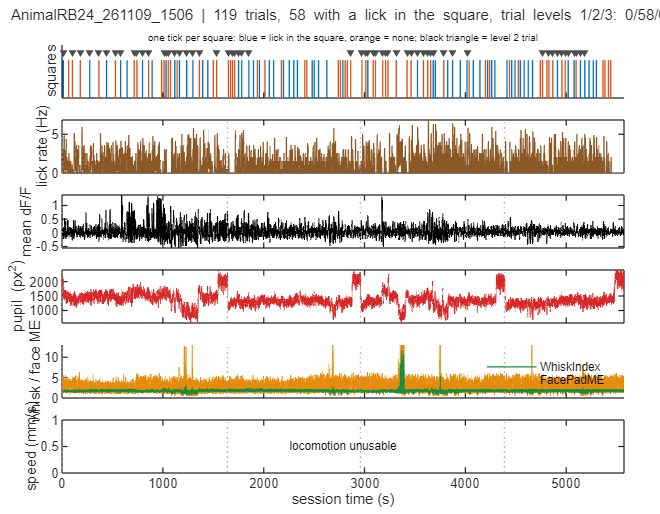

fh = newfig('Session overview', 18, 14);
tl = tiledlayout(fh, 6, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
title(tl, sprintf('%s | %d trials%s, trial levels 1/2/3: %d/%d/%d', strrep(session, '_', '\_'), nTr, iff(has_lick, sprintf(', %d with a lick in the square', sum(hit)), ''), lvl_n(1), lvl_n(2), lvl_n(3)), 'FontSize', 9, 'FontWeight', 'normal');
ax(1) = nexttile(tl);  hold on;
if has_lick
    plot(repmat(on_t(hit)', 2, 1), repmat([0; 1], 1, sum(hit)), 'Color', col_hit, 'LineWidth', 0.8);
    plot(repmat(on_t(~hit)', 2, 1), repmat([0; 1], 1, sum(~hit)), 'Color', col_mis, 'LineWidth', 0.8);
else
    plot(repmat(on_t', 2, 1), repmat([0; 1], 1, nTr), 'Color', col.sq, 'LineWidth', 0.8);
end
if any(lvl_t == 2) && any(lvl_t ~= 2); plot(on_t(lvl_t == 2), 1.2 * ones(sum(lvl_t == 2), 1), 'v', 'Color', [0.3 0.3 0.3], 'MarkerFaceColor', [0.3 0.3 0.3], 'MarkerSize', 3); end
ylim([0 1.4]);  yticks([]);  ylabel('squares');
title(ax(1), iff(has_lick, 'one tick per square: blue = lick in the square, orange = none; black triangle = level 2 trial', 'one tick per square'), 'FontSize', 6, 'FontWeight', 'normal');
ax(2) = nexttile(tl);
if has_lick
    plot(tCa, movmean(lick_rate, round(2 * fs)), 'Color', col.lick);  ylabel('lick rate (Hz)');
else
    text(0.5, 0.5, 'NO LICK DATA', 'Units', 'normalized', 'HorizontalAlignment', 'center', 'FontSize', 7, 'Color', [0.8 0 0]);  yticks([]);  ylabel('licks');
end
ax(3) = nexttile(tl);  plot(tCa, movmean(mean(dFF, 1), round(fs)), 'Color', col.dff);  ylabel('mean dF/F');
ax(4) = nexttile(tl);
if has_beh && isfield(data.Behav, 'PupilArea'); plot(tcam, data.Behav.PupilArea, 'Color', col.pupil); end
ylabel('pupil (px^2)');
ax(5) = nexttile(tl);  hold on;  h_face = gobjects(0);  h_whisk = gobjects(0);
if has_beh && isfield(data.Behav, 'FacePadME'); h_face = plot(tcam, data.Behav.FacePadME, 'Color', col.face); end
if has_beh && isfield(data.Behav, 'WhiskIndex'); h_whisk = plot(tcam, data.Behav.WhiskIndex, 'Color', col.whisk); end
ylabel('whisk / face ME');
if has_beh && all(isfield(data.Behav, {'WhiskIndex', 'FacePadME'}))
    ylim([0 1.3 * max(10, prctile(double(data.Behav.FacePadME(isfinite(data.Behav.FacePadME))), 99.5))]);                  % the spikes of the face motion are clipped, not the baseline
    legend([h_whisk, h_face], {'WhiskIndex', 'FacePadME'}, 'Location', 'northeast', 'FontSize', 7);
end
ax(6) = nexttile(tl);  plot(tCa, movmean(loc_speed, round(fs), 'omitnan'), 'Color', col.loc);  ylabel('speed (mm/s)');  xlabel('session time (s)');
if ~loc_ok; text(0.5, 0.5, 'locomotion unusable', 'Units', 'normalized', 'HorizontalAlignment', 'center', 'FontSize', 7); end
for a = 2:6; xline(ax(a), b_t0, 'Color', [0.6 0.6 0.6], 'LineStyle', ':', 'HandleVisibility', 'off'); end
linkaxes(ax, 'x');  xlim(ax(1), [tCa(1) tCa(end)]);
set(ax(1:5), 'XTickLabel', []);

if save_figs; savef(fh, '01_overview'); end

## 5. ROI signal quality (checks; the figures are in part C)

Noise-referenced metrics (the pipeline dFF has median ~0 and std ~0.7 for pure noise, see header): hf_noise : per-frame noise = MAD of diff(dFF)/sqrt(2); events are slow compared with one frame, so they barely enter it slow_ratio : var(smoothed dFF) / (hf_noise^2 / n_smooth) = variance of the smoothed trace relative to what white noise of that per-frame level would leave after smoothing. White noise = 1, slow transients >> 1. sig_neg : noise sigma of the smoothed trace measured on the LOWER half only (calcium events only go up) snr_slow : (p99.9 - median)/sig_neg of the smoothed trace (Gaussian noise alone gives 3.1); reported, not used for the verdict ev_pos / ev_neg : upward crossings of +3*sig_neg vs downward crossings of -3*sig_neg; events go up, so ev_pos >> ev_neg

Fc    = F - neuropil_factor * Fneu;
w_sm  = max(1, round(smooth_s * fs));
dsm   = movmean(dFF, w_sm, 2);
med_s = median(dsm, 2);
dev   = dsm - med_s;
neg   = dev < 0;
sig_neg  = max(sqrt(sum(dev.^2 .* neg, 2) ./ max(sum(neg, 2), 1)), eps('single'));
snr_slow = (prctile(dsm, 99.9, 2) - med_s) ./ sig_neg;
dd       = diff(dFF, 1, 2);
hf_noise = 1.4826 * median(abs(dd - median(dd, 2)), 2) / sqrt(2);
slow_ratio = var(dsm, 0, 2) ./ (hf_noise .^ 2 / w_sm);
up = dev >  3 * sig_neg;  dn = dev < -3 * sig_neg;
ev_pos = sum(diff([false(nROI, 1) up], 1, 2) == 1, 2);
ev_neg = sum(diff([false(nROI, 1) dn], 1, 2) == 1, 2);
frac_Fc_le0 = mean(Fc <= 0, 2);

% does the stored dFF follow from the stored F / Fneu / baseline with the settings above?
rows = 1:min(nROI, 30);
Fcr  = double(Fc(rows, :)) - double(F0(rows, :));
win_med = 2 * ceil(dff_window_s / median(dtc)) + 1;
den  = movmedian(Fcr, win_med, 2);
dFF_re = Fcr ./ den - 1;
re_err = median(abs(dFF_re - double(dFF(rows, :))), 2);
chk = addchk(chk, 'dFF: reproduces from F/Fneu/baseline', grade(max(re_err) < 1e-3, 1), sprintf('median |recomputed - stored| <= %.1e (neuropil %.2f, +-%g s). Larger = other settings were used', max(re_err), neuropil_factor, dff_window_s));
den_bad = false(nROI, 1);  den_bad(rows) = any(den <= 0, 2);
chk = addchk(chk, 'dFF: denominator > 0', grade(~any(den_bad), 1), sprintf('%d ROIs with movmedian(Fc - baseline) <= 0 (dF/F sign flips / explodes): %s', sum(den_bad), lst(find(den_bad)')));
chk = addchk(chk, 'F: neuropil over-subtraction', grade(~any(frac_Fc_le0 > 0.01), 1), sprintf('%d ROIs with Fc = F - %.1f*Fneu <= 0 in >1%% of frames: %s', sum(frac_Fc_le0 > 0.01), neuropil_factor, lst(find(frac_Fc_le0 > 0.01)')));

bad_F       = frac_Fc_le0 > 0.01 | den_bad;
noise_like  = slow_ratio < slow_ratio_thr | ev_pos < 2 * max(ev_neg, 1);
signal_like = ~bad_F & ~noise_like;
roiq = table((1:nROI)', cent(:, 1), cent(:, 2), arrayfun(@(c) c.npix, ca.Ca_cellstats(:)), median(F, 2), median(Fneu, 2), median(F0, 2), 100*frac_Fc_le0, ...
    std(dFF, 0, 2), skewness(double(dFF), 0, 2), hf_noise, slow_ratio, snr_slow, ev_pos, ev_neg, ev_pos / (nT/fs/60), signal_like, ...
    'VariableNames', {'roi','y','x','npix','F_med','Fneu_med','F0_med','pct_Fc_le0','std_dff','skew','hf_noise','slow_ratio','snr_slow','ev_pos','ev_neg','ev_per_min','signal_like'});
disp(roiq);

    roi     y      x     npix    F_med     Fneu_med    F0_med    pct_Fc_le0    std_dff     skew      hf_noise    slow_ratio    snr_slow    ev_pos    ev_neg    ev_per_min    signal_like
    ___    ___    ___    ____    ______    ________    ______    __________    _______    _______    ________    __________    ________    ______    ______    __________    ___________

      1    322    239     419    56.342      17.14 

chk = addchk(chk, 'ROIs: signal-like', grade(sum(signal_like) >= max(3, 0.25 * nROI), 1), sprintf('%d/%d ROIs pass (slow_ratio >= %g, ev_pos >= 2*ev_neg, Fc > 0 in >99%% of frames). Noise-like: %s; neuropil-limited: %s', sum(signal_like), nROI, slow_ratio_thr, lst(find(noise_like & ~bad_F)'), lst(find(bad_F)')));
chk = addchk(chk, 'ROIs: pure-noise std level', grade(true, 1), sprintf('median std(dFF) %.2f (pure noise gives ~0.71 under this dF/F definition), median per-frame noise %.2f', median(std(dFF, 0, 2)), median(hf_noise)));
printchk(chk, n0);  n0 = size(chk, 1);

  [PASS] dFF: reproduces from F/Fneu/baseline median |recomputed - stored| <= 1.8e-05 (neuropil 0.50, +-15 s). Larger = other settings were used
  [PASS] dFF: denominator > 0                 0 ROIs with movmedian(Fc - baseline) <= 0 (dF/F sign flips / explodes): []
  [WARN] F: neuropil over-subtraction         14 ROIs with Fc = F - 0.5*Fneu <= 0 in >1% of frames: [7 11 31 33 43 61 65 66 71 73 78 90 98 101]
  [PASS] ROIs: signal-like                    52/107 ROIs pass (slow_ratio >= 4, ev_pos >= 2*ev_neg, Fc > 0 in >99% of frames). Noise-like: [14 21 22 23 24 25 26 28 29 30 32 34 36 38 39 40 41 48 49 55 58 60 62 67 69 72 74 77 79 80 84 86 91 93 94 97 99 103 104 106 107]; neuropil-limited: [7 11 31 33 43 61 65 66 71 73 78 90 98 101]
  [PASS] ROIs: pure-noise std level           median std(dFF) 0.78 (pure noise gives ~0.71 under this dF/F definition), median per-frame noise 0.69



% dF/F used from here on (setting dff_source). Everything above (checks, classification) used the pipeline dF/F; dFF_pipe keeps it for the diagnostics that refer to it (hf_noise, the 0.71 noise level).
dFF_pipe = dFF;
switch dff_source
    case 'pipeline'
        chk = addchk(chk, 'dFF: source', grade(true, 1), 'pipeline dF/F (CaData.Ca_dFF, V3 definition: (Fc - p8)/movmedian(Fc - p8, +-15 s) - 1); amplitudes are in units of the local median excursion, not dF/F');
    case 'best'
        assert(isfield(data, 'BestDFF'), 'dff_source = best needs the BestDFF variable in %s (appended by the best-dF/F step)', data_file);
        bd = data.BestDFF;
        assert(isequal(size(bd.dFF), size(dFF)), 'BestDFF.dFF is %s, CaData dFF is %s', mat2str(size(bd.dFF)), mat2str(size(dFF)));
        dFF = bd.dFF;
        dsm = movmean(dFF, w_sm, 2);
        zb_ = double(dsm) - mean(double(dsm), 2);  zp_ = movmean(double(dFF_pipe), w_sm, 2);  zp_ = zp_ - mean(zp_, 2);
        r_bp = sum(zb_ .* zp_, 2) ./ sqrt(sum(zb_ .^ 2, 2) .* sum(zp_ .^ 2, 2));   clear zb_ zp_
        chk = addchk(chk, 'dFF: source', grade(median(r_bp) > 0.5, 1), sprintf('BestDFF.dFF (true dF/F = (Fc - F0)/max(F0, %g), Fc = F - %.2f*Fneu, F0 = running %gth percentile over +-%g s, smoothed %g s). Same ROI rows as CaData; correlation with the pipeline dF/F (%.1f s smoothing): median %.2f, 10th percentile %.2f. Classification above still uses the pipeline dF/F', ...
            bd.floor_counts, bd.neuropil_factor, bd.baseline_percentile, bd.baseline_halfwindow_s, bd.baseline_smooth_s, smooth_s, median(r_bp), prctile(r_bp, 10)));
        if abs(bd.neuropil_factor - neuropil_factor) > 1e-6; chk = addchk(chk, 'dFF: source neuropil', grade(false, 1), sprintf('BestDFF used neuropil %.2f, this script %.2f', bd.neuropil_factor, neuropil_factor)); end
        clear bd
    otherwise
        error('dff_source must be ''pipeline'' or ''best'', got %s', dff_source);
end
printchk(chk, n0);  n0 = size(chk, 1);

  [PASS] dFF: source                          pipeline dF/F (CaData.Ca_dFF, V3 definition: (Fc - p8)/movmedian(Fc - p8, +-15 s) - 1); amplitudes are in units of the local median excursion, not dF/F


## 6. Registration offset, FOV-wide events, drift and motion (checks; the figures are in part C)

6a. suite2p crops max_proj to the valid registered area, while ROI pixel coordinates (ypix/xpix, centroids) are in full-frame coordinates. Overlaying them directly shifts every ROI. The shift is found by maximising the mean Img_max intensity under the ROI pixels.

off = [0 0];  pl_rois = [];  yp = {};  xp = {};
if has_img
    pl_i = min(plane_show, numel(planes));
    im   = double(data.Img_max{pl_i, 1});  [Ly, Lx] = size(im);
    pl_rois = find(cent(:, 3) == planes(pl_i))';
    cs   = ca.Ca_cellstats;
    yp = cell(numel(pl_rois), 1);  xp = yp;
    for j = 1:numel(pl_rois); yp{j} = double(cs(pl_rois(j)).ypix(:)); xp{j} = double(cs(pl_rois(j)).xpix(:)); end
    allY = vertcat(yp{:});  allX = vertcat(xp{:});
    pick = round(linspace(1, numel(allY), min(numel(allY), 20000)));
    sy = allY(pick);  sx = allX(pick);
    shifts = -25:25;
    reg_score = nan(numel(shifts));
    for a = 1:numel(shifts)
        for b = 1:numel(shifts)
            yy = sy + 1 + shifts(a);  xx = sx + 1 + shifts(b);          % +1: suite2p pixels are 0-based
            okp = yy >= 1 & yy <= Ly & xx >= 1 & xx <= Lx;
            if mean(okp) > 0.9; reg_score(a, b) = mean(im(sub2ind([Ly Lx], yy(okp), xx(okp)))); end
        end
    end
    [mx, ix] = max(reg_score(:));  [ia, ib] = ind2sub(size(reg_score), ix);
    auto_off = [shifts(ia) shifts(ib)];
    score0   = reg_score(shifts == 0, shifts == 0);
    if ischar(roi_img_offset); off = auto_off; else; off = roi_img_offset; end
    full_sz  = [NaN NaN];
    if has_si; full_sz = double([data.SI_Info.hRoiManager.linesPerFrame data.SI_Info.hRoiManager.pixelsPerLine]); end
    chk = addchk(chk, 'ROI map: Img_max registration', grade(all(auto_off == 0) || mx / score0 > 1.05, 1), ...
        sprintf('Img_max %dx%d (frame %dx%d); ROI pixels land best at shift dy=%d dx=%d, mean intensity under ROIs %.1f vs %.1f unshifted (x%.2f); using [%d %d]', Ly, Lx, full_sz(1), full_sz(2), auto_off(1), auto_off(2), mx, score0, mx / score0, off(1), off(2)));
end

% 6b. FOV-wide events (many ROIs up at the same time) are typically motion, neuropil or arousal, not single-axon activity.
sl = find(signal_like)';  if numel(sl) < 3; sl = 1:nROI; end
co = mean(up(sl, :), 1);                                    % fraction of (signal-like) ROIs above +3 sigma at each frame
null_co = zeros(1, n_perm);
for p = 1:n_perm
    sh = randi([round(30*fs), nT - round(30*fs)], numel(sl), 1);
    idx = mod((0:nT-1) + sh, nT) + 1;                       % independent circular shift per ROI
    null_co(p) = max(mean(up(sub2ind(size(up), repmat(sl(:), 1, nT), idx)), 1));
end
co_thr = max(0.4, 1.2 * max(null_co));
g_on   = find(diff([0 co >= co_thr]) == 1);
if ~isempty(g_on); g_on = g_on([true, diff(tCa(g_on)) > 1]); end    % merge events closer than 1 s
g_t    = tCa(g_on);
g_trl  = arrayfun(@(t) find(t >= tr_t0 & t <= tr_t1, 1), g_t, 'UniformOutput', false);
g_trl(cellfun(@isempty, g_trl)) = {0};
chk = addchk(chk, 'population: FOV-wide events', grade(numel(g_t) <= 3, 1), sprintf('%d events with >= %.0f%% of %d ROIs up together (chance max %.0f%%), at s: %s (trials %s, 0 = break)', numel(g_t), 100*co_thr, numel(sl), 100*max(null_co), lst(round(g_t(1:min(end, 12)))), lst(cell2mat(g_trl(1:min(end, 12))))));
% FOV-wide events locked to the square? count those 0-3 s after an onset against the number expected for random times inside trials
task_time = sum(tr_t1 - tr_t0);
n_on_ev   = sum(arrayfun(@(t) any(t >= on_t & t <= on_t + resp_win(2)), g_t));
n_exp_ev  = numel(g_t) * nTr * diff(resp_win) / task_time;
chk = addchk(chk, 'population: events locked to the square', grade(~(n_on_ev >= 3 && n_on_ev > n_exp_ev + 3 * sqrt(max(n_exp_ev, 1))), 1), sprintf('%d of %d FOV-wide events fall %g-%g s after a square onset (%.1f expected for random times in the trials): a square-locked FOV-wide event points to a light leak, motion or global arousal, not to single axons', n_on_ev, numel(g_t), resp_win(1), resp_win(2), n_exp_ev));
ev_in_glob = nan(nROI, 1);
for r = 1:nROI
    on_r = tCa(diff([0 up(r, :)]) == 1);
    if ~isempty(on_r) && ~isempty(g_t); ev_in_glob(r) = mean(min(abs(on_r(:) - g_t(:)'), [], 2) <= 1); elseif ~isempty(on_r); ev_in_glob(r) = 0; end
end
chk = addchk(chk, 'population: events during FOV-wide events', grade(~(median(ev_in_glob(signal_like), 'omitnan') > 0.3), 1), sprintf('median %.0f%% of signal-like ROI events fall within 1 s of a FOV-wide event', 100*median(ev_in_glob(signal_like), 'omitnan')));

% correlation between ROIs (smoothed dFF): ROIs on the same axon share their events (r close to 1) and are NOT independent samples
ids = sl;  if numel(ids) < 3; ids = 1:min(nROI, 300); end
[~, so] = sort(slow_ratio(ids), 'descend');  ids = ids(so);
Cm = corrcoef(double(dsm(ids, :))');
px_um = NaN;  if has_si; px_um = abs(diff(data.SI_Info.hRoiManager.imagingFovUm([1 2]))) / data.SI_Info.hRoiManager.pixelsPerLine; end
[pa, pb] = find(triu(Cm > 0.8, 1));
pair_d = hypot(cent(ids(pa), 1) - cent(ids(pb), 1), cent(ids(pa), 2) - cent(ids(pb), 2));
chk = addchk(chk, 'ROIs: strongly correlated pairs', grade(isempty(pa), 1), sprintf('%d of %d pairs among the %d signal-like ROIs have r > 0.8 (same axon / shared signal, not independent); median centroid distance %.0f px = %.0f um', numel(pa), numel(ids)*(numel(ids)-1)/2, numel(ids), median(pair_d), median(pair_d) * px_um));
if ~isempty(pa)
    pr = Cm(sub2ind(size(Cm), pa, pb));  [~, po] = sort(pr, 'descend');  po = po(1:min(10, numel(po)));
    disp(table(ids(pa(po))', ids(pb(po))', pr(po), pair_d(po), 'VariableNames', {'roiA','roiB','r','dist_px'}));
end

    roiA    roiB       r       dist_px
    ____    ____    _______    _______

     68     105     0.98704    17.464 
     82      59     0.96767     11.18 
     16     105     0.95657     5.831 
     16      68     0.94809    11.705 
      4      50     0.93686    18.974 
      1      82     0.93091     10.63 
      9      81     0.92516     12.53 
     16      96     0.92227    8.4853 
      1      59      0.9112     10.77 
      3      87      0.9042        13 




% bleaching / drift of the raw ROI fluorescence (median per minute, relative to the first minute)
bn = round(60 * fs);  nb = floor(nT / bn);
Fb = reshape(median(reshape(double(Fc(:, 1:nb*bn)), nROI, bn, nb), 2), nROI, nb);
Fb_rel = Fb ./ Fb(:, 1);  Fb_rel(Fb(:, 1) <= 0, :) = NaN;
drift_pct = 100 * (median(Fb_rel(:, end), 'omitnan') - 1);
chk = addchk(chk, 'F: drift over session', grade(abs(drift_pct) < 30, 1), sprintf('median ROI Fc changes %.0f%% from first to last minute (bleaching / z-drift)', drift_pct));

% 6c. motion (optional: needs suite2p Fall.mat, not stored in the aggregated file)
% Rigid shift = ops.xoff/yoff, non-rigid deformation = spread of the block shifts ops.xoff1/yoff1. ROIs whose dFF follows motion are not axon signal.
motion_r = nan(nROI, 2);  mot_flag = false(nROI, 1);  have_motion = false;  rigid = nan(1, nT);  nonr = rigid;  thr99 = nan(nROI, 2);  mot_names = {'rigid', 'non-rigid'};
fall_file = fullfile(s2p_dir, 'Fall.mat');
if isfile(fall_file)
    o   = load(fall_file, 'ops');  ops = o.ops;
    xo  = double(ops.xoff(:))';  yo = double(ops.yoff(:))';
    len_ok = numel(xo) == nT;
    chk = addchk(chk, 'motion: ops length', grade(len_ok, 1), sprintf('%d motion samples vs %d frames', numel(xo), nT));
    if len_ok
        have_motion = true;
        rigid = hypot(xo - median(xo), yo - median(yo));
        nonr  = hypot(std(double(ops.xoff1), 0, 2), std(double(ops.yoff1), 0, 2))';
        bad_f = false(1, nT);  if isfield(ops, 'badframes'); bad_f = logical(ops.badframes(:))'; end
        mot_lim_px = 1 / px_um;  if ~isfinite(mot_lim_px); mot_lim_px = 6; end             % 1 um, about the width of an axon
        chk = addchk(chk, 'motion: rigid shift', grade(prctile(rigid, 99) < mot_lim_px, 1), sprintf('p99 %.1f px = %.2f um, max %.1f px (x %d..%d, y %d..%d px); WARN above %.1f px (1 um); %.2f%% frames flagged bad by suite2p', prctile(rigid, 99), prctile(rigid, 99) * px_um, max(rigid), min(xo), max(xo), min(yo), max(yo), mot_lim_px, 100*mean(bad_f)));
        mots = {rigid, nonr};
        null_r = zeros(nROI, n_perm, 2);
        for m = 1:2
            mv = movmean(mots{m}, w_sm);
            mz = (mv - mean(mv)) / std(mv);
            dz = (double(dsm) - mean(double(dsm), 2)) ./ std(double(dsm), 0, 2);
            motion_r(:, m) = dz * mz' / (nT - 1);
            for p = 1:n_perm
                null_r(:, p, m) = dz * circshift(mz, randi([round(30*fs), nT - round(30*fs)]))' / (nT - 1);
            end
        end
        thr99 = squeeze(prctile(abs(null_r), 99, 2));                              % [nROI x 2]
        mot_flag = any(abs(motion_r) > max(thr99, mot_r_thr), 2);
        chk = addchk(chk, 'motion: ROIs coupled to motion', grade(~any(mot_flag & signal_like), 1), sprintf('%d ROIs follow rigid / non-rigid motion beyond shuffle (|r| > shuffle p99 and > %.2f); %d of them signal-like: %s. Median |r| rigid %.2f, non-rigid %.2f', sum(mot_flag), mot_r_thr, sum(mot_flag & signal_like), lst(find(mot_flag & signal_like)'), median(abs(motion_r(:, 1))), median(abs(motion_r(:, 2)))));
    end
else
    chk = addchk(chk, 'motion: suite2p ops', grade(false, 1), sprintf('not checked: %s not found', fall_file));
end
printchk(chk, n0);  n0 = size(chk, 1);

  [PASS] ROI map: Img_max registration        Img_max 464x992 (frame 512x1024); ROI pixels land best at shift dy=-24 dx=-16, mean intensity under ROIs 58.7 vs 42.7 unshifted (x1.37); using [-24 -16]
  [WARN] population: FOV-wide events          73 events with >= 40% of 52 ROIs up together (chance max 19%), at s: [0 236 373 436 476 591 599 645 659 666 673 683] (trials [0 5 6 7 8 9 10 10 11 11 11 11], 0 = break)
  [PASS] population: events locked to the square 8 of 73 FOV-wide events fall 0-3 s after a square onset (5.1 expected for random times in the trials): a square-locked FOV-wide event points to a light leak, motion or global arousal, not to single axons
  [PASS] population: events during FOV-wide events median 24% of signal-like ROI events fall within 1 s of a FOV-wide event
  [WARN] ROIs: strongly correlated pairs      39 of 1326 pairs among the 52 signal-like ROIs have r > 0.8 (same axon / shared signal, not independent); median centroid distance 19 px = 2 um
  [WARN] F: drift o

## 7. ROI selection

Everything in part B (figures, tables) uses sel_roi. Part A stays on all ROIs so the checks are unchanged.

good_roi = find(signal_like & ~mot_flag)';
if ischar(roi_sel) || isstring(roi_sel)
    switch lower(char(roi_sel))
        case 'all';  sel_roi = 1:nROI;
        case 'signal'; sel_roi = find(signal_like)';
        case 'good'
            sel_roi = good_roi;
            if isempty(sel_roi); sel_roi = find(signal_like)'; chk = addchk(chk, 'ROI selection: fallback', grade(false, 1), 'no signal-like ROI is free of motion coupling: using the signal-like ROIs'); end
            if isempty(sel_roi); sel_roi = 1:nROI; chk = addchk(chk, 'ROI selection: fallback', grade(false, 1), 'no signal-like ROI at all: using all ROIs'); end
        otherwise;   error('roi_sel must be ''all'', ''signal'', ''good'' or a list of ROI numbers');
    end
else
    sel_roi = unique(double(roi_sel(:)'));
    assert(all(sel_roi >= 1 & sel_roi <= nROI & sel_roi == round(sel_roi)), 'roi_sel: ROI numbers must be integers between 1 and %d', nROI);
end
assert(~isempty(sel_roi), 'roi_sel selects no ROIs');
nSel = numel(sel_roi);
flagged = sel_roi(noise_like(sel_roi) | bad_F(sel_roi) | mot_flag(sel_roi));
chk = addchk(chk, 'ROI selection', grade(isempty(flagged) || ischar(roi_sel) || isstring(roi_sel), 1), ...
    sprintf('%d/%d ROIs selected (roi_sel = %s): %s. Flagged by the checks (noise-like / Fc<=0 / motion-coupled): %s', nSel, nROI, strtrim(evalc('disp(roi_sel)')), lst(sel_roi), lst(flagged)));
printchk(chk, n0);  n0 = size(chk, 1);

## 8. ROI groups, trial table and lick behaviour

One axon branching over the field gives several ROIs with the same signal (r > grp_r_thr on the smoothed dF/F): they are not independent samples. sel_roi is clustered and every trial statistic below uses the group means (group 1 = the largest group).

rng(2);
dFFd = double(dFF);
n_fine = 1;
if nSel >= 2
    gid = cluster(linkage(pdist(double(dsm(sel_roi, :)), 'correlation'), 'average'), 'cutoff', 1 - grp_r_thr, 'criterion', 'distance');
    n_fine = max(gid);
    if n_fine > max_groups                                                     % too many groups to show and test: Ward tree on the z-scored traces (Euclidean distance = correlation distance), cut at max_groups
        zsel_ = double(dsm(sel_roi, :));  zsel_ = (zsel_ - mean(zsel_, 2)) ./ std(zsel_, 0, 2);
        gid = cluster(linkage(zsel_, 'ward'), 'maxclust', max_groups);
    end
else
    gid = ones(nSel, 1);
end
gid = gid(:)';
gsz = accumarray(gid(:), 1)';  gmn = accumarray(gid(:), sel_roi(:), [], @min)';
[~, gord] = sort(-1000 * gsz + gmn);
[~, gid] = ismember(gid, gord);
ng = max(gid);
grp_rois = arrayfun(@(g) sel_roi(gid == g), 1:ng, 'UniformOutput', false);
grp_lab  = cellfun(@(r) ['ROI ' regexprep(num2str(r), '\s+', ',')], grp_rois, 'UniformOutput', false);
grp_mot  = cellfun(@(r) any(mot_flag(r)), grp_rois);
grp_mean = cell2mat(cellfun(@(r) mean(dFFd(r, :), 1), grp_rois(:), 'UniformOutput', false));     % [ng x nT]
gcol     = lines(ng);  gcol(1, :) = [0 0 0];
ctl_col  = [0.55 0.55 0.55];                                                  % control group (noise-like ROIs)
grp_name = arrayfun(@(g) sprintf('g%d (%d ROIs)', g, numel(grp_rois{g})), 1:ng, 'UniformOutput', false);
% control: the noise-like ROIs outside the selection. They carry no axonal signal, so whatever they show at the square or around licking is common-mode
% (motion, neuropil, z-shift) and is the reference for the groups. It is added as the last row of every statistic below (the figures show the groups only).
ctl_roi = find(noise_like & ~bad_F & ~ismember((1:nROI)', sel_roi))';
ngc = ng + double(~isempty(ctl_roi));
grp_all = grp_mean;  glab_all = grp_lab;
if ~isempty(ctl_roi)
    grp_all = [grp_mean; mean(dFFd(ctl_roi, :), 1)];
    glab_all = [grp_lab, {['control: noise-like ROI ' regexprep(num2str(ctl_roi), '\s+', ',')]}];
end
gcol_all = [gcol; ctl_col];  gcol_all = gcol_all([1:ng, ng + (1:(ngc - ng))], :);                 % colours of the groups, the control last (rows of grp_all)
gnm_all = [grp_name, repmat({'control'}, 1, ngc - ng)];
roi_lab  = string(sel_roi);  roi_skip = max(1, ceil(nSel / 40));
fprintf('\nROI groups (r > %g on the smoothed dF/F gives %d groups%s):\n', grp_r_thr, n_fine, iff(n_fine > max_groups, sprintf(', merged to max_groups = %d by a Ward tree', max_groups), ''));
for g = 1:ng; fprintf('  group %d (%d ROIs): %s%s\n', g, numel(grp_rois{g}), grp_lab{g}, iff(grp_mot(g), '  (contains motion-coupled ROIs)', '')); end

% findings table: {analysis, statistic, value, ci or p, n}
ex = cell(0, 5);
exadd = @(c, a, b, v, ci, n) [c; {a, b, v, ci, n}];
ci_str = @(x) sprintf('[%.2f, %.2f]', x(1), x(2));
boot_ci = @(x, f) prctile(arrayfun(@(b) f(x(randi(numel(x), numel(x), 1))), 1:n_boot), [2.5 97.5]);

% behaviour in session SD on the imaging grid (rows of beh_names), plus the rigid shift
nBeh = numel(beh_names);
BZ = nan(nBeh, nT);
for si = 1:nBeh; x = beh_ca.(beh_names{si}); BZ(si, :) = (x - mean(x, 'omitnan')) / std(x, 'omitnan'); end
rig_z = zeros(1, nT);  if have_motion; rig_z = (rigid - mean(rigid)) / std(rigid); end
XB = BZ;  xb_names = beh_names;
if have_motion; XB = [XB; rig_z];  xb_names = [xb_names, {'RigidShift'}]; end
nXB = numel(xb_names);
xb_col = cellfun(@(n) beh_cmap.(n), xb_names, 'UniformOutput', false);
xb_lab = cellfun(@(n) beh_lab.(n), xb_names, 'UniformOutput', false);
xi_ = @(nm) find(strcmp(xb_names, nm), 1);

% trial table
trl = table((1:nTr)', sub_of, lvl_t, wait_s, n_to, on_t, pump_lat, rew_kind, hit, n_win, lat1, cons_lat, cons_n, n_pre, n_post, ...
    'VariableNames', {'trial', 'subsession', 'level', 'wait_s', 'timeouts', 'onset_s', 'pump_after_onset_s', 'pump_kind', 'hit', 'licks_in_window', 'first_lick_lat_s', 'bout_lat_s', 'bout_licks', 'licks_pre5s', 'licks_post5s'});
sub_tbl = table((1:nB)', accumarray(sub_of, 1), 100 * accumarray(sub_of, hit) ./ accumarray(sub_of, 1), accumarray(sub_of, lat1, [], @(x) median(x, 'omitnan')), accumarray(sub_of, n_to), accumarray(sub_of, n_pre) / S.trials, ...
    'VariableNames', {'subsession', 'trials', 'hit_pct', 'median_first_lick_s', 'timeouts', 'licks_5s_before'});
if ~has_lick                                                                       % no lick data: keep the columns that do not depend on licks
    trl = trl(:, {'trial', 'subsession', 'level', 'wait_s', 'timeouts', 'onset_s', 'pump_after_onset_s', 'pump_kind'});
    sub_tbl = sub_tbl(:, {'subsession', 'trials', 'timeouts'});
end
disp(sub_tbl);
if has_lick
    rate_pre = n_pre / 5;
    fprintf('Hit trials: %d/%d. First lick after the square onset within %g s in %d trials, median latency %.2f s (hit trials %.2f s, other %.2f s). Pump in %d trials.\n', sum(hit), nTr, cons_max_s, sum(isfinite(lat1)), median(lat1, 'omitnan'), median(lat1(hit), 'omitnan'), median(lat1(~hit), 'omitnan'), sum(isfinite(rew_t)));
    ex = exadd(ex, '8 licking', sprintf('hit rate (lick %g-%g s after the square onset), %%', lw(1), lw(2)), P_mine, sprintf('log P = %.1f', S.P), nTr);
    ex = exadd(ex, '8 licking', 'trials with a pump, %', 100 * mean(isfinite(rew_t)), sprintf('level 1/2/3 trials %d/%d/%d', lvl_n(1), lvl_n(2), lvl_n(3)), nTr);
    ex = exadd(ex, '8 licking', 'trials with a lick within cons_max_s of the square onset, %', 100 * mean(isfinite(lat1)), '', nTr);
    ex = exadd(ex, '8 licking', 'median first-lick latency (s)', median(lat1, 'omitnan'), ci_str(boot_ci(lat1(isfinite(lat1)), @median)), sum(isfinite(lat1)));
    ex = exadd(ex, '8 licking', 'licks per s in the 5 s before the square', mean(rate_pre), ci_str(boot_ci(rate_pre, @mean)), nTr);
else
    fprintf('NO LICK DATA: hit rate, first-lick latency and lick rates are not available for this session.\n');
    ex = exadd(ex, '8 licking', 'lick data', 'none (no spout / no lick log)', '', nTr);
end
col_hit = [0 0.45 0.74];  col_mis = [0.85 0.33 0.1];

% figure 02: lick behaviour
if has_lick
    ed = -ev_pre_s:0.5:ev_post_s;  ctr = ed(1:end-1) + 0.25;
    LC = zeros(nTr, numel(ctr));
    for t = 1:nTr; LC(t, :) = histcounts(lick_t - on_t(t), ed) / 0.5; end
    fh = newfig('Lick behaviour', 18, 15);
    tl = tiledlayout(fh, 3, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(tl, [strrep(session, '_', '\_') ' | licking around the square and the pump'], 'FontSize', 9, 'FontWeight', 'normal');
    a1 = nexttile(tl, 1, [3 1]);  hold(a1, 'on');
    patch(a1, [0 lw(2) lw(2) 0], [0 0 nTr + 1 nTr + 1], col.sq, 'FaceAlpha', 0.15, 'EdgeColor', 'none');
    rx = cell(nTr, 1);  ry = rx;
    for t = 1:nTr; r_ = lick_t - on_t(t);  r_ = r_(r_ >= -ev_pre_s & r_ <= ev_post_s);  rx{t} = r_;  ry{t} = t * ones(size(r_)); end
    plot(a1, vertcat(rx{:}), vertcat(ry{:}), '.', 'Color', col.lick, 'MarkerSize', 3);
    ip_ = find(isfinite(pump_lat));
    plot(a1, pump_lat(ip_), ip_, 'x', 'Color', [0 0.3 0.9], 'MarkerSize', 4, 'LineWidth', 0.8);
    plot(a1, cons_lat(isfinite(cons_lat)), find(isfinite(cons_lat)), 'o', 'Color', [0.8 0 0], 'MarkerSize', 4);
    il2_ = find(lvl_t == 2);  if ~isempty(il2_) && any(lvl_t ~= 2); plot(a1, (-ev_pre_s + 0.3) * ones(size(il2_)), il2_, '>', 'Color', [0.3 0.3 0.3], 'MarkerFaceColor', [0.3 0.3 0.3], 'MarkerSize', 3); end
    yline(a1, (1:nB - 1) * S.trials + 0.5, ':', 'Color', [0.5 0.5 0.5]);
    set(a1, 'YDir', 'reverse');  xlim(a1, [-ev_pre_s ev_post_s]);  ylim(a1, [0 nTr + 1]);  xlabel(a1, 'time from the square onset (s)');  ylabel(a1, 'trial');
    title(a1, 'dots = licks, x = pump, o = rewarded bout, > = level 2 trial', 'FontSize', 6, 'FontWeight', 'normal');
    a2 = nexttile(tl, 2);  hold(a2, 'on');
    h2 = [sem_trace(a2, ctr, LC(hit, :)', col_hit, true), sem_trace(a2, ctr, LC(~hit, :)', col_mis, true)];
    xline(a2, [0 lw(2)], ':');  ylabel(a2, 'lick rate (Hz)');  xlabel(a2, 'time from the square onset (s)');  legend(a2, h2, {sprintf('hit (%d)', sum(hit)), sprintf('miss (%d)', sum(~hit))}, 'FontSize', 6, 'Location', 'northwest');
    title(a2, 'lick rate, trials with / without a lick in the square (mean +- SEM)', 'FontSize', 7, 'FontWeight', 'normal');
    a3 = nexttile(tl, 4);  hold(a3, 'on');
    histogram(a3, lat1, 0:0.25:cons_max_s, 'FaceColor', col.lick, 'EdgeColor', 'none');
    if any(isfinite(pump_lat)) && range(pump_lat(isfinite(pump_lat))) > 0.01; histogram(a3, pump_lat, 0:0.25:cons_max_s + 2, 'DisplayStyle', 'stairs', 'EdgeColor', [0 0.3 0.9], 'LineWidth', 1.2); end
    xline(a3, [0 lw(2)], ':');
    xlabel(a3, 'time from the square onset (s)');  ylabel(a3, 'trials');  title(a3, sprintf('first lick (brown), pump (blue line); no lick in %g s: %d trials, no pump: %d', cons_max_s, sum(~isfinite(lat1)), sum(~isfinite(rew_t))), 'FontSize', 6, 'FontWeight', 'normal');
    a4 = nexttile(tl, 6);  yyaxis(a4, 'left');  bar(a4, 1:nB, sub_tbl.hit_pct, 0.5, 'FaceColor', col_hit, 'EdgeColor', 'none');  ylabel(a4, 'hit trials (%)');  ylim(a4, [0 100]);
    yyaxis(a4, 'right');  plot(a4, 1:nB, sub_tbl.median_first_lick_s, 'ko-', 'MarkerFaceColor', 'k');  ylabel(a4, 'median first lick (s)');  ylim(a4, [0 max(1, 1.2 * max(sub_tbl.median_first_lick_s))]);  xticks(a4, 1:nB);  xlabel(a4, 'subsession');
    if save_figs; savef(fh, '02_lick_behaviour'); end
end

## 9. Square + reward onset response

Both start at the same frame, so this is the response to the compound event. Alignment: first square frame (2P clock); baseline base_win, response resp_win. Null: the same statistic at pseudo-onsets drawn at random inside the wait periods (same state of the animal: waiting, licking at ~1 Hz), nTr of them per draw. A pseudo-baseline starts at least ps_min_s after the trial start, like the real baselines (wait >= 8 s, baseline from 3 s before the square), because dF/F still decays for several s after the previous reward and pseudo-onsets right after the trial start would show a negative 'response'.

n_com = round((ev_pre_s + ev_post_s) * fs) + 1;  tev = linspace(-ev_pre_s, ev_post_s, n_com);
bi_ = tev >= base_win(1) & tev < base_win(2);  ri_ = tev >= resp_win(1) & tev <= resp_win(2);
Cg = align_trials_to_onsets(on_t, grp_all, tCa, ev_pre_s, ev_post_s, n_com);        % [ng x time x trials]
Cg_base = mean(Cg(:, bi_, :), 2, 'omitnan');  Cg = Cg - Cg_base;
Cr = align_trials_to_onsets(on_t, dFFd(sel_roi, :), tCa, ev_pre_s, ev_post_s, n_com);
Cr = Cr - mean(Cr(:, bi_, :), 2, 'omitnan');
Bal = align_trials_to_onsets(on_t, XB, tCa, ev_pre_s, ev_post_s, n_com);             % [behaviour x time x trials], session SD
Braw = Bal;  Braw_base = mean(Bal(:, bi_, :), 2, 'omitnan');  Bal = Bal - Braw_base;
amp = reshape(mean(Cg(:, ri_, :), 2, 'omitnan'), ngc, nTr);                           % mean dF/F change in resp_win, per group and trial

% pseudo-onsets
n_ps = 6;  ps_t = [];  ps_min_s = 5;
for t = 1:nTr
    lo = tr_t0(t) + ps_min_s - base_win(1);  hi = on_t(t) - resp_win(2) - 0.5;
    if hi > lo; ps_t = [ps_t; lo + (hi - lo) * rand(n_ps, 1)]; end %#ok<AGROW>
end
% short waits (RB24_261104_1651: 6-8 s) leave no room for a pseudo-baseline that starts ps_min_s after the trial start: then the quiet stretch is taken from
% ps_decay_s after the end of the previous square (dF/F has decayed) to the same end as above. Sessions with enough pseudo-onsets are not affected.
ps_decay_s = 4;
if numel(ps_t) < 100
    ps_t = [];
    for t = 2:nTr
        lo = st_end(t-1) + ps_decay_s - base_win(1);  hi = on_t(t) - resp_win(2) - 0.5;
        if hi > lo; ps_t = [ps_t; lo + (hi - lo) * rand(n_ps, 1)]; end %#ok<AGROW>
    end
    fprintf('  pseudo-onsets: waits too short for the standard window, drawn from %g s after the previous square to %g s before the next one\n', ps_decay_s - base_win(1), resp_win(2) + 0.5);
end
n_cps = round((-base_win(1) + resp_win(2)) * fs) + 1;  t_ps = linspace(base_win(1), resp_win(2), n_cps);
Cps = align_trials_to_onsets(ps_t, grp_all, tCa, -base_win(1), resp_win(2), n_cps);
Cps = Cps - mean(Cps(:, t_ps >= base_win(1) & t_ps < base_win(2), :), 2, 'omitnan');
amp_ps = reshape(mean(Cps(:, t_ps >= resp_win(1) & t_ps <= resp_win(2), :), 2, 'omitnan'), ngc, []);
n_ps_tot = size(amp_ps, 2);
chk = addchk(chk, 'onset response: pseudo-onsets', grade(n_ps_tot >= 100, 1), sprintf('%d pseudo-onsets from %d trials with a wait long enough (baseline >= %g s after the trial start); the null for the %d real onsets is built from them', n_ps_tot, round(n_ps_tot / n_ps), ps_min_s, nTr));
null_amp = zeros(ngc, n_perm);  null_tr = zeros(ngc, n_cps, n_perm);
for b = 1:n_perm
    ix = randi(n_ps_tot, nTr, 1);
    null_amp(:, b) = mean(amp_ps(:, ix), 2);  null_tr(:, :, b) = mean(Cps(:, :, ix), 3);
end
null_band = prctile(null_tr, [2.5 97.5], 3);                                         % [ng x time x 2]
obs_amp = mean(amp, 2);
p_on = (1 + sum(abs(null_amp) >= abs(obs_amp), 2)) / (n_perm + 1);
fprintf('\n9 square + reward onset response (mean dF/F change %g-%g s after onset, %d trials; null = %d pseudo-onsets in the wait periods)\n', resp_win(1), resp_win(2), nTr, n_ps_tot);
p_hm = nan(ngc, 1);  d_hm = nan(ngc, 1);  ci_hm = nan(ngc, 2);  ci_on = nan(ngc, 2);
for g = 1:ngc
    a = amp(g, :)';
    ci = boot_ci(a, @mean);  ci_on(g, :) = ci;
    ex = exadd(ex, ['9 onset response, ' glab_all{g}], sprintf('mean dF/F change %g-%g s (pseudo-onset null mean %+.3f, sd %.3f)', resp_win(1), resp_win(2), mean(null_amp(g, :)), std(null_amp(g, :))), obs_amp(g), sprintf('%s, perm p=%.3f, signrank p=%.3g', ci_str(ci), p_on(g), signrank(a)), nTr);
    if has_lick && sum(hit) >= 3 && sum(~hit) >= 3
        d_hm(g) = mean(a(hit)) - mean(a(~hit));
        ah = a(hit);  am = a(~hit);
        bs = arrayfun(@(b) mean(ah(randi(numel(ah), numel(ah), 1))) - mean(am(randi(numel(am), numel(am), 1))), 1:n_boot);
        ci_hm(g, :) = prctile(bs, [2.5 97.5]);
        pl_ = zeros(1, n_perm);
        for b = 1:n_perm; h_ = hit(randperm(nTr)); pl_(b) = mean(a(h_)) - mean(a(~h_)); end
        p_hm(g) = (1 + sum(abs(pl_) >= abs(d_hm(g)))) / (n_perm + 1);
        ex = exadd(ex, ['9 hit vs miss, ' glab_all{g}], 'mean dF/F change, hit minus miss', d_hm(g), sprintf('%s, label-permutation p=%.3f', ci_str(ci_hm(g, :)), p_hm(g)), sum(hit));
    end
    if has_lick
        fprintf('  %s: %+.3f dF/F %s (null %+.3f +- %.3f, p=%.3f); hit - miss %+.3f %s (p=%.3f)\n', glab_all{g}, obs_amp(g), ci_str(ci), mean(null_amp(g, :)), std(null_amp(g, :)), p_on(g), d_hm(g), ci_str(ci_hm(g, :)), p_hm(g));
    else
        fprintf('  %s: %+.3f dF/F %s (null %+.3f +- %.3f, p=%.3f); no lick data: no hit / miss split\n', glab_all{g}, obs_amp(g), ci_str(ci), mean(null_amp(g, :)), std(null_amp(g, :)), p_on(g));
    end
end
ev_beh = reshape(mean(Bal(:, ri_, :), 2, 'omitnan'), nXB, nTr);
fprintf('  behaviour change in the same window (session SD): %s\n', strjoin(arrayfun(@(i) sprintf('%s %+.2f', xb_names{i}, mean(ev_beh(i, :), 'omitnan')), 1:nXB, 'UniformOutput', false), ', '));
for i = 1:nXB; ex = exadd(ex, '9 behaviour at the onset', [xb_lab{i} ', change in resp_win (session SD)'], mean(ev_beh(i, :), 'omitnan'), ci_str(boot_ci(ev_beh(i, isfinite(ev_beh(i, :)))', @mean)), nTr); end

% figure 03: onset response of the (at most max_groups) ROI groups and the control group of noise-like ROIs (grey, last row of Cg)
cmap_hm = turbo;
has_ctl = ngc > ng;
pl_ = pump_lat(isfinite(pump_lat));
if isempty(pl_); pump_txt = 'no pump'; elseif range(pl_) < 0.01; pump_txt = sprintf('pump %.1f s after the onset', median(pl_)); else; pump_txt = sprintf('pump %.1f-%.1f s after the onset (median %.1f s)', min(pl_), max(pl_), median(pl_)); end
mm_ = reshape(mean(Cg, 3, 'omitnan'), ngc, []);
fh = newfig('Onset response', 18, 21);
tl = tiledlayout(fh, 3, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
title(tl, sprintf('%s | square onset, %s, %d trials, %d ROI group(s)', strrep(session, '_', '\_'), pump_txt, nTr, ng), 'FontSize', 9, 'FontWeight', 'normal');
a1 = nexttile(tl, 1);
Mh = squeeze(Cg(1, :, :))';  imagesc(a1, tev, 1:nTr, Mh);  cm = max(0.5, prctile(abs(Mh(:)), 99));  clim(a1, [-cm cm]);  colormap(a1, cmap_hm);  hold(a1, 'on');
plot(a1, cons_lat(isfinite(cons_lat)), find(isfinite(cons_lat)), 'k.', 'MarkerSize', 5);
plot(a1, pump_lat(isfinite(pump_lat)), find(isfinite(pump_lat)), 'wx', 'MarkerSize', 3);
xline(a1, [0 lw(2)], 'w:');  yline(a1, (1:nB - 1) * S.trials + 0.5, 'w:');  xlabel(a1, 'time from the square onset (s)');  ylabel(a1, 'trial');  cb = colorbar(a1);  cb.Label.String = '\DeltadF/F';  cb.FontSize = 7;
title(a1, [grp_name{1} ' per trial' iff(has_lick, '; black dot = rewarded lick bout, white x = pump', '')], 'FontSize', 7, 'FontWeight', 'normal');
a2 = nexttile(tl, 2);  hold(a2, 'on');
patch(a2, [0 lw(2) lw(2) 0], [-1 -1 1 1] * 1e3, col.sq, 'FaceAlpha', 0.12, 'EdgeColor', 'none');
fill(a2, [t_ps fliplr(t_ps)], [squeeze(null_band(1, :, 1)) fliplr(squeeze(null_band(1, :, 2)))], [0.7 0.7 0.7], 'FaceAlpha', 0.5, 'EdgeColor', 'none');
hg = gobjects(1, ngc);  for g = 1:ng; hg(g) = sem_trace(a2, tev, squeeze(Cg(g, :, :)), gcol(g, :), true); end
if has_ctl; hg(ngc) = sem_trace(a2, tev, squeeze(Cg(ngc, :, :)), ctl_col, true); end
yline(a2, 0, ':');  xlabel(a2, 'time from the square onset (s)');  ylabel(a2, '\DeltadF/F');  xlim(a2, tev([1 end]));
ylim(a2, [min(mm_(:)), max(mm_(:))] + [-1 1] * 0.5 * max(0.1, range(mm_(:))));
legend(a2, hg, [grp_name, repmat({'control (noise-like ROIs)'}, 1, has_ctl)], 'FontSize', 6, 'Location', 'northwest');
title(a2, 'mean +- SEM over trials; grey band = 95% of pseudo-onset means (g1)', 'FontSize', 7, 'FontWeight', 'normal');
for q = 1:1 + has_ctl
    a3 = nexttile(tl, 2 + q);  hold(a3, 'on');
    gq = iff(q == 1 || ~has_ctl, 1, ngc);
    if has_lick
        h3 = [sem_trace(a3, tev, squeeze(Cg(gq, :, hit)), col_hit, true), sem_trace(a3, tev, squeeze(Cg(gq, :, ~hit)), col_mis, true)];
        xline(a3, [0 lw(2)], ':');  yline(a3, 0, ':');  xlabel(a3, 'time from the square onset (s)');  ylabel(a3, '\DeltadF/F');  xlim(a3, tev([1 end]));
        legend(a3, h3, {sprintf('lick in the square (%d)', sum(hit)), sprintf('no lick (%d)', sum(~hit))}, 'FontSize', 6, 'Location', 'northwest');
        title(a3, iff(q == 1 || ~has_ctl, [grp_name{1} ': trials with / without a lick'], 'control (noise-like ROIs): the same split'), 'FontSize', 7, 'FontWeight', 'normal');
    else
        text(a3, 0.5, 0.5, 'NO LICK DATA: no hit / miss split', 'Units', 'normalized', 'HorizontalAlignment', 'center', 'FontSize', 8, 'Color', [0.8 0 0]);
        set(a3, 'XTick', [], 'YTick', []);
    end
    a3s(q) = a3; %#ok<SAGROW>
end
if has_lick && has_ctl; yl3 = vertcat(a3s.YLim);  set(a3s, 'YLim', [min(yl3(:, 1)) max(yl3(:, 2))]); end
a5 = nexttile(tl, 5);  hold(a5, 'on');  hb = gobjects(1, nXB);
for i = 1:nXB; hb(i) = sem_trace(a5, tev, squeeze(Bal(i, :, :)), xb_col{i}, true); end
xline(a5, [0 lw(2)], ':');  yline(a5, 0, ':');  xlabel(a5, 'time from the square onset (s)');  ylabel(a5, '\Delta behaviour (session SD)');  xlim(a5, tev([1 end]));  legend(a5, hb, xb_lab, 'FontSize', 6, 'Location', 'northwest', 'NumColumns', 2);
title(a5, 'behaviour at the same onsets', 'FontSize', 7, 'FontWeight', 'normal');
a6 = nexttile(tl, 6);  hold(a6, 'on');
for g = 1:ngc
    col_g = gcol(min(g, ng), :);  if g > ng; col_g = ctl_col; end
    xj = g + (rand(nTr, 1) - 0.5) * 0.4;
    if has_lick
        scatter(a6, xj(hit), amp(g, hit), 10, col_g, 'filled', 'MarkerFaceAlpha', 0.5);
        scatter(a6, xj(~hit), amp(g, ~hit), 10, col_g, 'MarkerEdgeAlpha', 0.7);
    else
        scatter(a6, xj, amp(g, :), 10, col_g, 'filled', 'MarkerFaceAlpha', 0.5);
    end
    plot(a6, g + [-0.3 0.3], obs_amp(g) * [1 1], 'r-', 'LineWidth', 1.8);
    plot(a6, g + [-0.3 0.3], prctile(null_amp(g, :), 97.5) * [1 1], 'b:');  plot(a6, g + [-0.3 0.3], prctile(null_amp(g, :), 2.5) * [1 1], 'b:');
end
yl6 = [min(amp(:)) max(amp(:))];  yl6 = yl6 + [-0.05 0.25] * range(yl6);  ylim(a6, yl6);
for g = 1:ngc; text(a6, g, yl6(2), sprintf('p=%.2g', p_on(g)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 6); end
yline(a6, 0, ':');  xticks(a6, 1:ngc);  xticklabels(a6, [arrayfun(@(g) sprintf('g%d%s', g, iff(grp_mot(g), '*', '')), 1:ng, 'UniformOutput', false), repmat({'ctl'}, 1, has_ctl)]);  xlim(a6, [0.4 ngc + 0.6]);  ylabel(a6, sprintf('mean \\DeltadF/F, %g-%g s', resp_win(1), resp_win(2)));
title(a6, ['per trial' iff(has_lick, ' (filled = lick in the square)', '') ', red = mean, blue = pseudo-onset 95%, * = motion-coupled'], 'FontSize', 6, 'FontWeight', 'normal');
if save_figs; savef(fh, '03_onset_response'); end

## 10. Reward consumption: is the response locked to the square, to the licking that triggers the pump, or to the pump?

Three events can be told apart: the square onset, the first lick of the square (which fires the pump at level 3 or starts the RewardDelay countdown) and the pump. With the pump at the onset (level 1/2, RewardDelay 0) licking starts 0.1 s to several s later: a response locked to the pump keeps its time whatever the latency, one locked to the licking moves with it (10a). With the pump RewardDelay s after the first lick the rewarded bout is identical to a spontaneous bout up to the pump: the rewarded - spontaneous difference BEFORE the pump is the context (square, expectation, trigger), AFTER the pump it is the reward (10b / 10c run in both windows). Rewarded bouts (section 3a) are compared with spontaneous bouts of the same kind (isolated, same size criterion) in the wait period: the same motor act without a reward. Baselines: rewarded = the pre-square baseline of that trial, spontaneous = base_win before the bout. Unrewarded bouts after the square in trials without a pump (late bouts) are shown as a second control when there are enough of them.

if has_lick
    pre_b = 3;  post_b = 8;  nb_c = round((pre_b + post_b) * fs) + 1;  tb = linspace(-pre_b, post_b, nb_c);
    bb_ = tb >= base_win(1) & tb < base_win(2);
    ev_k = find(isfinite(cons_on));  nEv = numel(ev_k);  nSp = numel(sp_on);
    late_k = find(isfinite(late_on));  nLate = numel(late_k);
    lat_split_c = lat_split_s;  if ~(lw(1) < lat_split_c && lat_split_c < lw(2)); lat_split_c = mean(lw); end   % the split must lie inside the lick window (RB24_261104_1540: lickWindowMin 1.1 s > lat_split_s 1 s made the edges decrease), else the middle of the window
    lat_edges = [lw(1) lat_split_c lw(2) cons_max_s + eps];
    assert(issorted(lat_edges, 'strictascend'), 'latency class edges %s are not increasing: lickWindow [%g %g] s, cons_max_s %g s', mat2str(lat_edges), lw(1), lw(2), cons_max_s);
    lat_cls = discretize(cons_lat(ev_k), lat_edges);                                   % latency class (from the square onset) of the rewarded BOUT
    cls1 = discretize(lat1, lat_edges);                                               % latency class of the FIRST LICK after the onset, every trial (latency test)
    cls_lab = {sprintf('%.1f-%g s', lw(1), lat_split_c), sprintf('%g-%g s', lat_split_c, lw(2)), sprintf('%g-%g s (after the square)', lw(2), cons_max_s)};
    cls_col = [0 0.45 0.74; 0.93 0.69 0.13; 0.85 0.33 0.1];
    win_sets = {bout_win};  win_lab = {sprintf('%g-%g s after the first lick', bout_win(1), bout_win(2))};
    if any(rew_kind == 4); win_sets{2} = rdel + bout_win;  win_lab{2} = sprintf('%g-%g s after the pump (first lick + %g s)', rdel + bout_win(1), rdel + bout_win(2), rdel); end
    nW = numel(win_sets);
    fprintf('\n10 reward consumption: first lick after the onset in %d trials (latency classes %s: %s trials); %d rewarded bouts (%s trials), %d spontaneous bouts, %d late unrewarded bouts\n', sum(isfinite(lat1)), strjoin(cls_lab, ' | '), strjoin(arrayfun(@(c) num2str(sum(cls1 == c)), 1:3, 'UniformOutput', false), '/'), nEv, strjoin(arrayfun(@(c) num2str(sum(lat_cls == c)), 1:3, 'UniformOutput', false), '/'), nSp, nLate);
    Rg = align_trials_to_onsets(cons_on(ev_k), grp_all, tCa, pre_b, post_b, nb_c) - Cg_base(:, 1, ev_k);          % bout-aligned, baseline of the trial
    Sg = align_trials_to_onsets(sp_on, grp_all, tCa, pre_b, post_b, nb_c);  Sg = Sg - mean(Sg(:, bb_, :), 2, 'omitnan');
    Rb_ = align_trials_to_onsets(cons_on(ev_k), XB, tCa, pre_b, post_b, nb_c) - Braw_base(:, 1, ev_k);
    Sb_ = align_trials_to_onsets(sp_on, XB, tCa, pre_b, post_b, nb_c);  Sb_ = Sb_ - mean(Sb_(:, bb_, :), 2, 'omitnan');
    if nLate >= 5
        Lg = align_trials_to_onsets(late_on(late_k), grp_all, tCa, pre_b, post_b, nb_c) - Cg_base(:, 1, late_k);                    % trial baseline, like the rewarded bouts
        Lb_ = align_trials_to_onsets(late_on(late_k), XB, tCa, pre_b, post_b, nb_c) - Braw_base(:, 1, late_k);
    end

    % 10a  timing of the response against the latency of the first lick (half-rise of the single-trial group trace, trials with a clear response)
    th = nan(ngc, nTr);
    for g = 1:ngc
        for t = find(isfinite(lat1))'
            y_ = movmean(squeeze(Cg(g, :, t)), round(0.3 * fs));
            [~, th(g, t)] = rise_stats(tev, y_, [0 cons_max_s + 2], base_win);
        end
    end
    rho_th = nan(ngc, 1);  p_th = rho_th;  n_th = rho_th;  rho_am = rho_th;  p_am = rho_th;
    for g = 1:ngc
        v = isfinite(th(g, :)') & isfinite(lat1);  n_th(g) = sum(v);
        if n_th(g) >= 6
            [rho_th(g), p_th(g)] = corr(th(g, v)', lat1(v), 'Type', 'Spearman');
            ex = exadd(ex, ['10a response timing, ' glab_all{g}], 'Spearman: half-rise time of the response vs latency of the first lick (0 = locked to the square / a pump at the onset, >0 = follows the licking)', rho_th(g), sprintf('p=%.3g', p_th(g)), n_th(g));
        end
        v2 = isfinite(amp(g, :)') & isfinite(lat1);
        [rho_am(g), p_am(g)] = corr(amp(g, v2)', lat1(v2), 'Type', 'Spearman');
        ex = exadd(ex, ['10a response size, ' glab_all{g}], 'Spearman: onset response (resp_win) vs latency of the first lick', rho_am(g), sprintf('p=%.3g', p_am(g)), sum(v2));
        fprintf('  %s: half-rise vs first-lick latency rho %+.2f (p=%.3g, n=%d trials with a clear response); response size vs latency rho %+.2f (p=%.3g)\n', glab_all{g}, rho_th(g), p_th(g), n_th(g), rho_am(g), p_am(g));
    end

    % 10b / 10c  rewarded vs spontaneous bouts in each window, with the behaviour of the same events as covariates
    bcov = intersect({'LocSpeed', 'WhiskIndex', 'PupilArea', 'FacePadME', 'RigidShift'}, xb_names, 'stable');
    bcov_ix = cellfun(xi_, bcov);
    pairs = {'rewarded (all)', 1:nEv; sprintf('rewarded, latency %s', cls_lab{3}), find(lat_cls == 3)'};
    A_rew_w = cell(1, nW);  A_sp_w = cell(1, nW);  nl_rew_w = cell(1, nW);  nl_sp_w = cell(1, nW);
    rs_b = nan(nW, ngc);  rs_ci = nan(nW, ngc, 2);                                    % rewarded - spontaneous (adjusted, 10b) per window and group, for the summary figure
    for wi = 1:nW
        bw_ = tb >= win_sets{wi}(1) & tb <= win_sets{wi}(2);
        A_rew = reshape(mean(Rg(:, bw_, :), 2, 'omitnan'), ngc, nEv);  A_sp = reshape(mean(Sg(:, bw_, :), 2, 'omitnan'), ngc, nSp);
        B_rew = reshape(mean(Rb_(:, bw_, :), 2, 'omitnan'), nXB, nEv);  B_sp = reshape(mean(Sb_(:, bw_, :), 2, 'omitnan'), nXB, nSp);
        nl_rew = arrayfun(@(k) sum(lick_t >= cons_on(k) + win_sets{wi}(1) & lick_t <= cons_on(k) + win_sets{wi}(2)), ev_k);
        nl_sp  = arrayfun(@(k) sum(lick_t >= k + win_sets{wi}(1) & lick_t <= k + win_sets{wi}(2)), sp_on);
        A_rew_w{wi} = A_rew;  A_sp_w{wi} = A_sp;  nl_rew_w{wi} = nl_rew;  nl_sp_w{wi} = nl_sp;
        fprintf('  window %s: licks in the window: rewarded %.1f, spontaneous %.1f\n', win_lab{wi}, mean(nl_rew), mean(nl_sp));
        for g = 1:ngc
            for q = 1:size(pairs, 1)
                ii = pairs{q, 2};
                if numel(ii) < 5 || nSp < 5; continue; end
                y_ = [A_rew(g, ii)'; A_sp(g, :)'];
                X_ = [ones(numel(y_), 1), [ones(numel(ii), 1); zeros(nSp, 1)], [B_rew(bcov_ix, ii), B_sp(bcov_ix, :)]', [nl_rew(ii); nl_sp]];
                sdx = std(X_(:, 3:end), 0, 1);  sdx(sdx == 0) = 1;  X_(:, 3:end) = (X_(:, 3:end) - mean(X_(:, 3:end), 1)) ./ sdx;
                [b_, ci_, p_] = ols_boot(y_, X_, n_boot);
                if q == 1; rs_b(wi, g) = b_(2);  rs_ci(wi, g, :) = reshape(ci_(2, :), 1, 1, 2); end
                d_raw = mean(A_rew(g, ii)) - mean(A_sp(g, :));
                p_rs = ranksum(A_rew(g, ii), A_sp(g, :));
                fprintf('  %s | %s vs spontaneous, %s: raw %+.3f dF/F (rank-sum p=%.3g); adjusted for %s and licks in the window: %+.3f %s (bootstrap p=%.3f), n=%d+%d\n', glab_all{g}, pairs{q, 1}, win_lab{wi}, d_raw, p_rs, strjoin(bcov, '/'), b_(2), ci_str(ci_(2, :)), p_(2), numel(ii), nSp);
                ex = exadd(ex, ['10b ' pairs{q, 1} ' minus spontaneous bout, ' glab_all{g}], sprintf('mean dF/F change %s (raw %+.3f, rank-sum p=%.3g)', win_lab{wi}, d_raw, p_rs), b_(2), sprintf('adjusted for behaviour+licks %s, p=%.3f', ci_str(ci_(2, :)), p_(2)), numel(y_));
            end
        end
        % 10c  the same comparison standardised for the number of licks: mean difference inside strata of the licks in the window (<= 4, 5-6, 7-8, >= 9), averaged with
        % the weights of the spontaneous bouts (strata with fewer than 3 bouts in either set are left out); bootstrap over bouts (rewarded and spontaneous resampled separately)
        cnt_edges = [0 5 7 9 Inf];
        for q = 1:size(pairs, 1)
            ii = pairs{q, 2};
            if numel(ii) < 5 || nSp < 5; continue; end
            for g = 1:ngc
                d_ = strat_diff(nl_rew(ii), A_rew(g, ii)', nl_sp, A_sp(g, :)', cnt_edges);
                if ~isfinite(d_); continue; end
                bs = zeros(n_boot, 1);
                for b = 1:n_boot
                    ir = randi(numel(ii), numel(ii), 1);  is_ = randi(nSp, nSp, 1);
                    bs(b) = strat_diff(nl_rew(ii(ir)), A_rew(g, ii(ir))', nl_sp(is_), A_sp(g, is_)', cnt_edges);
                end
                bs = bs(isfinite(bs));  ci_ = prctile(bs, [2.5 97.5]);  p_ = max(2 * min(mean(bs > 0), mean(bs < 0)), 1 / n_boot);
                fprintf('  %s | %s vs spontaneous, %s, standardised for the number of licks in the window (rewarded %.1f vs spontaneous %.1f licks): %+.3f dF/F %s (bootstrap p=%.3f)\n', glab_all{g}, pairs{q, 1}, win_lab{wi}, mean(nl_rew(ii)), mean(nl_sp), d_, ci_str(ci_), p_);
                ex = exadd(ex, ['10c ' pairs{q, 1} ' minus spontaneous bout, lick-count standardised, ' glab_all{g}], sprintf('mean dF/F change %s', win_lab{wi}), d_, sprintf('%s, bootstrap p=%.3f', ci_str(ci_), p_), numel(ii) + nSp);
            end
        end
    end
    A_rew = A_rew_w{1};  A_sp = A_sp_w{1};

    % figure 04: group 1 (and the control) around the square, the first lick and the pump; behaviour around the same bouts (the two kinds of bouts should lick alike)
    col_rew = [0.8 0 0];  col_sp = [0.4 0.4 0.4];  col_late = [0.93 0.55 0.1];
    fh = newfig('Reward consumption', 18, 19);
    tl = tiledlayout(fh, 3, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(tl, sprintf('%s | square, first lick and pump (%d rewarded, %d spontaneous, %d late bouts)', strrep(session, '_', '\_'), nEv, nSp, nLate), 'FontSize', 9, 'FontWeight', 'normal');
    a1 = nexttile(tl, 1);  hold(a1, 'on');  h1 = gobjects(1, 3);
    for c = 1:3
        if sum(cls1 == c) >= 2; h1(c) = sem_trace(a1, tev, squeeze(Cg(1, :, cls1 == c)), cls_col(c, :), true); end
    end
    xline(a1, [0 lw(2)], ':');  yline(a1, 0, ':');  xlabel(a1, 'time from the square onset (s)');  ylabel(a1, '\DeltadF/F');  xlim(a1, tev([1 end]));
    ok_h = isgraphics(h1);  legend(a1, h1(ok_h), arrayfun(@(c) sprintf('first lick %s (n=%d)', cls_lab{c}, sum(cls1 == c)), find(ok_h), 'UniformOutput', false), 'FontSize', 6, 'Location', 'northwest');
    title(a1, [grp_name{1} ' at the square onset, split by first-lick latency'], 'FontSize', 7, 'FontWeight', 'normal');
    a2 = nexttile(tl, 2);  hold(a2, 'on');  h2 = gobjects(1, 3);
    if nEv >= 2; h2(1) = sem_trace(a2, tb, squeeze(Rg(1, :, :)), col_rew, true); end
    if nSp >= 2; h2(2) = sem_trace(a2, tb, squeeze(Sg(1, :, :)), col_sp, true); end
    if nLate >= 5; h2(3) = sem_trace(a2, tb, squeeze(Lg(1, :, :)), col_late, true); end
    xline(a2, 0, ':');  yline(a2, 0, ':');  xlabel(a2, 'time from the first lick of the bout (s)');  ylabel(a2, '\DeltadF/F');  xlim(a2, tb([1 end]));
    if any(rew_kind == 4); xline(a2, rdel, '--', 'pump', 'Color', [0 0.3 0.9], 'LabelVerticalAlignment', 'bottom', 'FontSize', 6); end
    ok_h = isgraphics(h2);  l2 = {sprintf('rewarded (%d)', nEv), sprintf('spontaneous (%d)', nSp), sprintf('late, no pump (%d)', nLate)};  legend(a2, h2(ok_h), l2(ok_h), 'FontSize', 6, 'Location', 'northwest');
    title(a2, [grp_name{1} ' at the first lick of the bout'], 'FontSize', 7, 'FontWeight', 'normal');
    a3 = nexttile(tl, 3);  hold(a3, 'on');
    ilr = xi_('LickRate');  h3 = gobjects(1, 3);
    h3(1) = sem_trace(a3, tb, squeeze(Rb_(ilr, :, :)), col_rew, true);
    if nSp >= 2; h3(2) = sem_trace(a3, tb, squeeze(Sb_(ilr, :, :)), col_sp, true); end
    if nLate >= 5; h3(3) = sem_trace(a3, tb, squeeze(Lb_(ilr, :, :)), col_late, true); end
    xline(a3, 0, ':');  xlabel(a3, 'time from the first lick of the bout (s)');  ylabel(a3, '\Delta lick rate (session SD)');  xlim(a3, tb([1 end]));  legend(a3, h3(isgraphics(h3)), l2(isgraphics(h3)), 'FontSize', 6, 'Location', 'northeast');
    title(a3, 'control: the kinds of bouts should lick alike', 'FontSize', 7, 'FontWeight', 'normal');
    a4 = nexttile(tl, 4);  hold(a4, 'on');
    beh_show = intersect({'PupilArea', 'LocSpeed'}, xb_names, 'stable');  ls_ = {'-', '--'};  hh = gobjects(0);  hl = {};
    for q = 1:numel(beh_show)
        ib = xi_(beh_show{q});
        hh(end+1) = sem_trace(a4, tb, squeeze(Rb_(ib, :, :)), col_rew, false);  set(hh(end), 'LineStyle', ls_{q});  hl{end+1} = [xb_lab{ib} ', rewarded']; %#ok<SAGROW>
        if nSp >= 2; hh(end+1) = sem_trace(a4, tb, squeeze(Sb_(ib, :, :)), col_sp, false);  set(hh(end), 'LineStyle', ls_{q});  hl{end+1} = [xb_lab{ib} ', spontaneous']; end %#ok<SAGROW>
    end
    xline(a4, 0, ':');  yline(a4, 0, ':');  xlim(a4, tb([1 end]));  ylabel(a4, '\Delta behaviour (session SD)');  xlabel(a4, 'time from the first lick of the bout (s)');
    if ~isempty(hh); legend(a4, hh, hl, 'FontSize', 6, 'Location', 'northeast'); end
    yl4 = ylim(a4);  ylim(a4, [yl4(1), yl4(2) + 0.5 * range(yl4)]);
    title(a4, 'control: arousal around the same bouts', 'FontSize', 7, 'FontWeight', 'normal');
    a5 = nexttile(tl, 5);  hold(a5, 'on');
    for g = [1, ngc * (ngc > ng)]
        if g == 0; continue; end
        v = isfinite(th(g, :)') & isfinite(lat1);
        cg_ = gcol(min(g, ng), :);  if g > ng; cg_ = ctl_col; end
        scatter(a5, lat1(v), th(g, v), 14, cg_, 'filled', 'MarkerFaceAlpha', 0.6);
    end
    plot(a5, [0 cons_max_s], [0 cons_max_s], 'k:');  xlabel(a5, 'first lick after the onset, latency (s)');  ylabel(a5, 'half-rise of the dF/F response (s)');  xlim(a5, [0 cons_max_s]);
    title(a5, sprintf('g1 (black) and control (grey): on the dotted line = follows the lick (rho g1 %+.2f%s)', rho_th(1), iff(ngc > ng, sprintf(', ctl %+.2f', rho_th(ngc)), '')), 'FontSize', 6, 'FontWeight', 'normal');
    a6 = nexttile(tl, 6);  hold(a6, 'on');
    Mbar = nan(ngc, 2 * nW);  Ebar = Mbar;
    for g = 1:ngc
        for wi = 1:nW
            Mbar(g, 2 * wi - 1) = mean(A_rew_w{wi}(g, :), 'omitnan');  Ebar(g, 2 * wi - 1) = std(A_rew_w{wi}(g, :), 'omitnan') / sqrt(max(1, nEv));
            Mbar(g, 2 * wi) = mean(A_sp_w{wi}(g, :), 'omitnan');  Ebar(g, 2 * wi) = std(A_sp_w{wi}(g, :), 'omitnan') / sqrt(max(1, nSp));
        end
    end
    bh = bar(a6, [Mbar; nan(1, size(Mbar, 2))], 'grouped');                      % padded row: a single group would otherwise be drawn as one series
    bcols = [col_rew; col_sp; 0.45 0 0; 0.25 0.25 0.25];
    for c = 1:size(Mbar, 2)
        bh(c).FaceColor = bcols(c, :);  bh(c).EdgeColor = 'none';
        errorbar(a6, bh(c).XEndPoints(1:ngc), Mbar(:, c), Ebar(:, c), 'k.', 'CapSize', 3);
    end
    xlim(a6, [0.4 ngc + 0.6]);  xticks(a6, 1:ngc);  xticklabels(a6, [arrayfun(@(g) sprintf('g%d%s', g, iff(grp_mot(g), '*', '')), 1:ng, 'UniformOutput', false), repmat({'ctl'}, 1, ngc > ng)]);
    ylabel(a6, '\DeltadF/F');
    bl_ = {}; for wi = 1:nW; bl_ = [bl_, {['rewarded, ' win_lab{wi}], ['spontaneous, ' win_lab{wi}]}]; end %#ok<AGROW>
    legend(a6, bh, bl_, 'FontSize', 5, 'Location', 'northeast');
    yl6 = ylim(a6);  ylim(a6, [yl6(1), yl6(2) + 0.6 * range(yl6)]);
    title(a6, 'bout response (mean +- SEM) by group; * = motion-coupled', 'FontSize', 7, 'FontWeight', 'normal');
    if save_figs; savef(fh, '04_reward_consumption'); end

    % 10d / 10e  does a rewarded bout do more than a spontaneous bout of the SAME SIZE (dose-response in the first window), and does the difference outlast the licking (late window plat_win)?
    % Rewarded bouts are longer and happen in another state (after the square, higher pupil), so the rewarded - spontaneous difference is estimated five ways, each removing a different part of
    % that confound: raw | licks only (kind + licks + licks^2, plus the licks of the other window) | lick strata (10c) | matched pairs (every rewarded bout against the nearest spontaneous bout
    % in licks + behaviour, caliper match_cal, with replacement) | regression (kind + licks + behaviour of the window, 10b). If the estimators agree the answer does not depend on how the
    % lick count is controlled. The late window is also taken WITHOUT the baseline subtraction (the baseline of a rewarded bout is the pre-square level of its trial, that of a spontaneous
    % bout the 3 s before it, so the two are not the same reference); spontaneous bouts with a square onset inside the late window are dropped there.
    cnt_edges = [0 5 7 9 Inf];                                                         % the lick strata of 10c
    nxt_ = inf(nSp, 1);
    for k = 1:nSp; q_ = on_t(on_t > sp_on(k)); if ~isempty(q_); nxt_(k) = min(q_); end; end
    sp_okP = find(nxt_ - sp_on(:) > plat_win(2));  nSpP = numel(sp_okP);
    if nEv >= 5 && nSpP >= 5
        bw1_ = tb >= win_sets{1}(1) & tb <= win_sets{1}(2);  bwP_ = tb >= plat_win(1) & tb <= min(plat_win(2), post_b);
        lk_ = @(t0, w) arrayfun(@(k) sum(lick_t >= k + w(1) & lick_t <= k + w(2)), t0(:));      % licks of every bout in the window w (s from its first lick)
        n1_r = lk_(cons_on(ev_k), win_sets{1});  n1_s = lk_(sp_on, win_sets{1});  nP_r = lk_(cons_on(ev_k), plat_win);  nP_s = lk_(sp_on, plat_win);
        nbc = numel(bcov_ix);
        bwin_ = @(M, bw, n) reshape(mean(M(bcov_ix, bw, :), 2, 'omitnan'), nbc, n)';           % behaviour of the bouts in a window [bouts x covariates]
        B1_r = bwin_(Rb_, bw1_, nEv);  B1_s = bwin_(Sb_, bw1_, nSp);  BP_r = bwin_(Rb_, bwP_, nEv);  BP_s = bwin_(Sb_, bwP_, nSp);
        Rg_raw = align_trials_to_onsets(cons_on(ev_k), grp_all, tCa, pre_b, post_b, nb_c);  Sg_raw = align_trials_to_onsets(sp_on, grp_all, tCa, pre_b, post_b, nb_c);
        yP_r = reshape(mean(Rg(:, bwP_, :), 2, 'omitnan'), ngc, nEv);  yP_s = reshape(mean(Sg(:, bwP_, :), 2, 'omitnan'), ngc, nSp);
        yA_r = reshape(mean(Rg_raw(:, bwP_, :), 2, 'omitnan'), ngc, nEv);  yA_s = reshape(mean(Sg_raw(:, bwP_, :), 2, 'omitnan'), ngc, nSp);
        est_nm = {'raw', 'licks only', 'lick strata', 'matched', 'regression'};
        w_e = [ones(1, nbc), 2];  w_p = [ones(1, nbc), 2, 2];                           % matching weights: the lick counts count double
        res_e = cell(1, ngc);  res_p = res_e;  res_a = res_e;
        for g = 1:ngc
            res_e{g} = bout_contrast(A_rew_w{1}(g, :)', A_sp_w{1}(g, :)', n1_r, n1_s, [B1_r, n1_r], [B1_s, n1_s], nbc + 1, w_e, cnt_edges, match_cal, n_boot);
            res_p{g} = bout_contrast(yP_r(g, :)', yP_s(g, sp_okP)', n1_r, n1_s(sp_okP), [BP_r, n1_r, nP_r], [BP_s(sp_okP, :), n1_s(sp_okP), nP_s(sp_okP)], [nbc + 1, nbc + 2], w_p, cnt_edges, match_cal, n_boot);
            res_a{g} = bout_contrast(yA_r(g, :)', yA_s(g, sp_okP)', n1_r, n1_s(sp_okP), [BP_r, n1_r, nP_r], [BP_s(sp_okP, :), n1_s(sp_okP), nP_s(sp_okP)], [nbc + 1, nbc + 2], w_p, cnt_edges, match_cal, n_boot);
        end
        pr_ = @(r, nm) fprintf('    %-44s %s\n', nm, strjoin(arrayfun(@(e) sprintf('%s %+.2f %s', est_nm{e}, r.est(e), ci_str([r.lo(e) r.hi(e)])), 1:5, 'UniformOutput', false), ' | '));
        fprintf('  10d rewarded - spontaneous at the same lick count, %s: licks %.1f rewarded vs %.1f spontaneous; %d of %d rewarded bouts matched (largest covariate imbalance after matching %.2f SD)\n', win_lab{1}, mean(n1_r), mean(n1_s), res_e{1}.nm(1), res_e{1}.nm(2), res_e{1}.smd);
        for g = 1:ngc; pr_(res_e{g}, glab_all{g}(1:min(end, 44))); end
        fprintf('  10e late window %g-%g s after the first lick (%d of %d spontaneous bouts have no square in it): licks 0-%g s %.1f vs %.1f, licks in the window %.1f vs %.1f; %d of %d matched (imbalance %.2f SD)\n', plat_win(1), plat_win(2), nSpP, nSp, win_sets{1}(2), mean(n1_r), mean(n1_s(sp_okP)), mean(nP_r), mean(nP_s(sp_okP)), res_p{1}.nm(1), res_p{1}.nm(2), res_p{1}.smd);
        for g = 1:ngc; pr_(res_p{g}, [glab_all{g}(1:min(end, 24)) ' (baseline-subtracted)']); pr_(res_a{g}, [glab_all{g}(1:min(end, 24)) ' (no baseline)']); end
        for g = 1:ngc
            for e = 1:5
                ex = exadd(ex, ['10d rewarded - spontaneous, ' est_nm{e} ', ' glab_all{g}], sprintf('mean dF/F change %s', win_lab{1}), res_e{g}.est(e), sprintf('%s, bootstrap p=%.3f', ci_str([res_e{g}.lo(e) res_e{g}.hi(e)]), res_e{g}.p(e)), nEv + nSp);
                ex = exadd(ex, ['10e rewarded - spontaneous, ' est_nm{e} ', ' glab_all{g}], sprintf('mean dF/F change %g-%g s after the first lick', plat_win(1), plat_win(2)), res_p{g}.est(e), sprintf('%s, bootstrap p=%.3f', ci_str([res_p{g}.lo(e) res_p{g}.hi(e)]), res_p{g}.p(e)), nEv + nSpP);
                ex = exadd(ex, ['10e rewarded - spontaneous, ' est_nm{e} ', no baseline, ' glab_all{g}], sprintf('mean dF/F %g-%g s after the first lick, no baseline subtraction', plat_win(1), plat_win(2)), res_a{g}.est(e), sprintf('%s, bootstrap p=%.3f', ci_str([res_a{g}.lo(e) res_a{g}.hi(e)]), res_a{g}.p(e)), nEv + nSpP);
            end
        end

        % figure 04b: dose-response (g1 and the control), the five estimators in both windows, the late response by group and the behaviour in the late window
        fh = newfig('Dose-response and late window', 18, 19);
        tl = tiledlayout(fh, 3, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
        title(tl, sprintf('%s | rewarded vs spontaneous bouts at the same lick count, and the late window', strrep(session, '_', '\_')), 'FontSize', 9, 'FontWeight', 'normal');
        xlabel(tl, 'licks only = quadratic in the lick count | lick strata = inside bins of the lick count | matched = nearest spontaneous bout in licks + behaviour | regression = + behaviour', 'FontSize', 6);
        gsh = 1;  if ngc > ng; gsh(2) = ngc; end
        for q = 1:numel(gsh)
            g = gsh(q);  ax = nexttile(tl, q);  hold(ax, 'on');  hq = gobjects(1, 2);
            for k = 1:2
                if k == 1; nn = n1_r;  yy = A_rew_w{1}(g, :)';  cc = col_rew; else; nn = n1_s;  yy = A_sp_w{1}(g, :)';  cc = col_sp; end
                scatter(ax, nn + 0.24 * (rand(numel(nn), 1) - 0.5), yy, 7, cc, 'filled', 'MarkerFaceAlpha', 0.22);
                bi = discretize(nn, cnt_edges);  mx = nan(1, numel(cnt_edges) - 1);  my = mx;  se = mx;
                for b = 1:numel(mx)
                    ib = bi == b & isfinite(yy);
                    if sum(ib) >= 3; mx(b) = mean(nn(ib));  my(b) = mean(yy(ib));  se(b) = std(yy(ib)) / sqrt(sum(ib)); end
                end
                hq(k) = errorbar(ax, mx, my, se, 'o-', 'Color', cc, 'MarkerFaceColor', cc, 'LineWidth', 1.4, 'CapSize', 3, 'MarkerSize', 4);
            end
            yline(ax, 0, ':');  xlabel(ax, sprintf('licks in %g-%g s after the first lick', win_sets{1}(1), win_sets{1}(2)));  ylabel(ax, sprintf('\\DeltadF/F, %g-%g s', win_sets{1}(1), win_sets{1}(2)));
            qy_ = prctile([A_rew_w{1}(g, :), A_sp_w{1}(g, :)], [1 99]);  ry_ = max(range(qy_), eps);  ylim(ax, [qy_(1) - 0.1 * ry_, qy_(2) + 0.45 * ry_]);        % the 1-99 % range of the dots (single outliers fall outside) + room for the legend
            legend(ax, hq, {sprintf('rewarded (%d)', nEv), sprintf('spontaneous (%d)', nSp)}, 'FontSize', 6, 'Location', 'northwest');
            title(ax, sprintf('%s: difference inside lick bins %+.2f %s', gnm_all{g}, res_e{g}.est(3), ci_str([res_e{g}.lo(3) res_e{g}.hi(3)])), 'FontSize', 6.5, 'FontWeight', 'normal');
        end
        ax = nexttile(tl, 3);  draw_forest(ax, res_e, gcol_all, est_nm);
        title(ax, sprintf('rewarded - spontaneous, %g-%g s after the first lick', win_sets{1}(1), win_sets{1}(2)), 'FontSize', 7, 'FontWeight', 'normal');
        res_pp = cell(1, ngc);
        for g = 1:ngc; res_pp{g} = struct('est', [res_p{g}.est; res_a{g}.est(5)], 'lo', [res_p{g}.lo; res_a{g}.lo(5)], 'hi', [res_p{g}.hi; res_a{g}.hi(5)]); end
        ax = nexttile(tl, 4);  draw_forest(ax, res_pp, gcol_all, [est_nm, {'regr., no baseline'}]);
        title(ax, sprintf('rewarded - spontaneous, %g-%g s after the first lick', plat_win(1), plat_win(2)), 'FontSize', 7, 'FontWeight', 'normal');
        ax = nexttile(tl, 5);  hold(ax, 'on');
        Mp = nan(ngc, 2);  Ep = Mp;
        for g = 1:ngc
            Mp(g, :) = [mean(yP_r(g, :), 'omitnan'), mean(yP_s(g, sp_okP), 'omitnan')];
            Ep(g, :) = [std(yP_r(g, :), 'omitnan') / sqrt(nEv), std(yP_s(g, sp_okP), 'omitnan') / sqrt(nSpP)];
        end
        bh = bar(ax, [Mp; nan(1, 2)], 'grouped');
        for c = 1:2
            bh(c).FaceColor = iff(c == 1, col_rew, col_sp);  bh(c).EdgeColor = 'none';
            errorbar(ax, bh(c).XEndPoints(1:ngc), Mp(:, c), Ep(:, c), 'k.', 'CapSize', 3);
        end
        xlim(ax, [0.4 ngc + 0.6]);  xticks(ax, 1:ngc);  xticklabels(ax, [arrayfun(@(g) sprintf('g%d%s', g, iff(grp_mot(g), '*', '')), 1:ng, 'UniformOutput', false), repmat({'ctl'}, 1, ngc > ng)]);
        ylabel(ax, '\DeltadF/F');  legend(ax, bh, {sprintf('rewarded (%d)', nEv), sprintf('spontaneous (%d)', nSpP)}, 'FontSize', 6, 'Location', 'northeast');
        yl_ = ylim(ax);  ylim(ax, [yl_(1), yl_(2) + 0.3 * range(yl_)]);
        title(ax, sprintf('late response, %g-%g s after the first lick (mean +- SEM)', plat_win(1), plat_win(2)), 'FontSize', 7, 'FontWeight', 'normal');
        ax = nexttile(tl, 6);  hold(ax, 'on');
        beh_pl = [bcov, intersect({'LickRate'}, xb_names)];  Mb = nan(numel(beh_pl), 2);  Eb = Mb;
        for q = 1:numel(beh_pl)
            ib = xi_(beh_pl{q});
            yr_ = squeeze(mean(Rb_(ib, bwP_, :), 2, 'omitnan'));  ys_ = squeeze(mean(Sb_(ib, bwP_, sp_okP), 2, 'omitnan'));
            Mb(q, :) = [mean(yr_, 'omitnan'), mean(ys_, 'omitnan')];  Eb(q, :) = [std(yr_, 'omitnan') / sqrt(nEv), std(ys_, 'omitnan') / sqrt(nSpP)];
        end
        bh = bar(ax, Mb, 'grouped');
        for c = 1:2
            bh(c).FaceColor = iff(c == 1, col_rew, col_sp);  bh(c).EdgeColor = 'none';
            errorbar(ax, bh(c).XEndPoints, Mb(:, c), Eb(:, c), 'k.', 'CapSize', 3);
        end
        xticks(ax, 1:numel(beh_pl));  xticklabels(ax, cellfun(@(n) beh_short.(n), beh_pl, 'UniformOutput', false));  xtickangle(ax, 45);  ylabel(ax, '\Delta behaviour (session SD)');
        title(ax, sprintf('behaviour in the same late window %g-%g s', plat_win(1), plat_win(2)), 'FontSize', 7, 'FontWeight', 'normal');
        if save_figs; savef(fh, '04b_dose_response_late_window'); end
    else
        fprintf('  10d / 10e skipped: %d rewarded and %d usable spontaneous bouts (>= 5 of each needed)\n', nEv, nSpP);
    end
else
    fprintf('\n10 reward consumption: skipped, NO LICK DATA (no first-lick latency, rewarded or spontaneous bouts).\n');
end

## 11. Trial-by-trial regression and change over the session

Per trial and group: amp = mean dF/F change in resp_win. Predictors (all z-scored): state before the square (mean over base_win), behaviour change in resp_win, licks in resp_win, hit, trial number. Coefficients with trial-bootstrap CIs. 'hit' and 'licks' ask: does consuming the reward go with a different response once locomotion, whisking, pupil, face motion and rigid shift are accounted for?

zs = @(x) (x - mean(x, 'omitnan')) ./ std(x, 'omitnan');
pre_b_ = reshape(mean(Braw(:, bi_, :), 2, 'omitnan'), nXB, nTr);
nl_resp = arrayfun(@(t) sum(lick_t >= on_t(t) + resp_win(1) & lick_t <= on_t(t) + resp_win(2)), (1:nTr)');
pred = {}; Xp = [];
if any(strcmp(xb_names, 'PupilArea'));  pred{end+1} = 'pre pupil';        Xp = [Xp, zs(pre_b_(xi_('PupilArea'), :)')]; end
if any(strcmp(xb_names, 'LocSpeed'));   pred{end+1} = 'pre locomotion';   Xp = [Xp, zs(pre_b_(xi_('LocSpeed'), :)')]; end
if any(strcmp(xb_names, 'WhiskIndex')); pred{end+1} = 'pre whisking';     Xp = [Xp, zs(pre_b_(xi_('WhiskIndex'), :)')]; end
if any(strcmp(xb_names, 'LocSpeed'));   pred{end+1} = 'evoked locomotion'; Xp = [Xp, zs(ev_beh(xi_('LocSpeed'), :)')]; end
if any(strcmp(xb_names, 'WhiskIndex')); pred{end+1} = 'evoked whisking';  Xp = [Xp, zs(ev_beh(xi_('WhiskIndex'), :)')]; end
if any(strcmp(xb_names, 'PupilArea'));  pred{end+1} = 'evoked pupil';     Xp = [Xp, zs(ev_beh(xi_('PupilArea'), :)')]; end
if have_motion;                         pred{end+1} = 'evoked rigid shift'; Xp = [Xp, zs(ev_beh(xi_('RigidShift'), :)')]; end
if has_lick
    pred{end+1} = 'licks in resp\_win';  Xp = [Xp, zs(nl_resp)];
    pred{end+1} = 'hit';                 Xp = [Xp, zs(double(hit))];
end
pred{end+1} = 'trial number';        Xp = [Xp, zs((1:nTr)')];
beta = nan(ngc, numel(pred) + 1);  beta_ci = nan(ngc, numel(pred) + 1, 2);  beta_p = beta;  r2_tr = nan(ngc, 1);
fprintf('\n11 trial regression: amp ~ %s\n', strjoin(strrep(pred, '\_', '_'), ' + '));
for g = 1:ngc
    y_ = amp(g, :)';  X_ = [ones(nTr, 1), Xp];
    [b_, ci_, p_] = ols_boot(y_, X_, n_boot);
    beta(g, :) = b_';  beta_ci(g, :, :) = reshape(ci_, 1, numel(b_), 2);  beta_p(g, :) = p_';
    ok = all(isfinite([y_ X_]), 2);  r2_tr(g) = 1 - sum((y_(ok) - X_(ok, :) * b_) .^ 2) / sum((y_(ok) - mean(y_(ok))) .^ 2);
    fprintf('  %s (R2 %.2f): %s\n', glab_all{g}, r2_tr(g), strjoin(arrayfun(@(i) sprintf('%s %+.3f%s', strrep(pred{i}, '\_', '_'), b_(i + 1), iff(p_(i + 1) < 0.05, '*', '')), 1:numel(pred), 'UniformOutput', false), ', '));
    for i = iff(has_lick, numel(pred) - 2:numel(pred), 1:numel(pred))                     % licks, hit, trial number (no lick data: every predictor)
        ex = exadd(ex, ['11 trial regression, ' glab_all{g}], ['dF/F change per SD of ' strrep(pred{i}, '\_', '_') ' (other predictors held)'], b_(i + 1), sprintf('%s, bootstrap p=%.3f; model R2 %.2f', ci_str(ci_(i + 1, :)), p_(i + 1), r2_tr(g)), sum(ok));
    end
end
% change over the session
rho_tr = nan(ngc, 1);  p_tr = rho_tr;
for g = 1:ngc
    [rho_tr(g), p_tr(g)] = corr((1:nTr)', amp(g, :)', 'Type', 'Spearman', 'Rows', 'complete');
    mu_s = arrayfun(@(k) mean(amp(g, sub_of == k)), 1:nB);
    ex = exadd(ex, ['11 change over the session, ' glab_all{g}], 'Spearman: onset response vs trial number', rho_tr(g), sprintf('p=%.3g; subsession means %s', p_tr(g), mat2str(round(mu_s, 3))), nTr);
    fprintf('  %s: onset response vs trial number rho %+.2f (p=%.3g); subsession means %s\n', glab_all{g}, rho_tr(g), p_tr(g), mat2str(round(mu_s, 3)));
end
if has_lick
    [rho_lt, p_lt] = corr((1:nTr)', lat1, 'Type', 'Spearman', 'Rows', 'complete');
    ex = exadd(ex, '11 change over the session', 'Spearman: first-lick latency vs trial number', rho_lt, sprintf('p=%.3g', p_lt), sum(isfinite(lat1)));
end

fh = newfig('Trial regression', 18, 14);
tl = tiledlayout(fh, 2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
title(tl, [strrep(session, '_', '\_') ' | trial-by-trial regression and change over the session'], 'FontSize', 9, 'FontWeight', 'normal');
a1 = nexttile(tl, 1, [1 2]);  hold(a1, 'on');
if has_lick
    plot(a1, find(hit), amp(1, hit), 'o', 'Color', gcol(1, :), 'MarkerFaceColor', gcol(1, :), 'MarkerSize', 3);
    plot(a1, find(~hit), amp(1, ~hit), 'o', 'Color', gcol(1, :), 'MarkerSize', 3);
else
    plot(a1, 1:nTr, amp(1, :), 'o', 'Color', gcol(1, :), 'MarkerFaceColor', gcol(1, :), 'MarkerSize', 3);
end
h1 = gobjects(1, ngc);
for g = 1:ngc; h1(g) = plot(a1, 1:nTr, movmean(amp(g, :), 9, 'omitnan'), '-', 'Color', gcol_all(g, :), 'LineWidth', 1.6); end
xline(a1, (1:nB - 1) * S.trials + 0.5, ':');  yline(a1, 0, ':');  xlabel(a1, 'trial');  ylabel(a1, sprintf('mean \\DeltadF/F, %g-%g s', resp_win(1), resp_win(2)));  xlim(a1, [0 nTr + 1]);
yl1 = ylim(a1);  ylim(a1, [yl1(1), yl1(2) + 0.45 * range(yl1)]);
legend(a1, h1, arrayfun(@(g) sprintf('%s: rho vs trial %+.2f (p=%.2g)', gnm_all{g}, rho_tr(g), p_tr(g)), 1:ngc, 'UniformOutput', false), 'FontSize', 6, 'Location', 'northeast');
title(a1, sprintf('lines = 9-trial mean of every group; dots = single trials of g1%s', iff(has_lick, ' (filled = lick in the square, open = none)', '')), 'FontSize', 7, 'FontWeight', 'normal');
a2 = nexttile(tl, 3);  hold(a2, 'on');
np_ = numel(pred);  dy = 0.8 / ngc;
for g = 1:ngc
    yy = (1:np_) + (g - (ngc + 1) / 2) * dy;
    errorbar(a2, beta(g, 2:end), yy, beta(g, 2:end) - squeeze(beta_ci(g, 2:end, 1)), squeeze(beta_ci(g, 2:end, 2)) - beta(g, 2:end), 'horizontal', 'o', 'Color', gcol_all(g, :), 'MarkerFaceColor', gcol_all(g, :), 'MarkerSize', 3, 'CapSize', 2);
end
xline(a2, 0, ':');  yticks(a2, 1:np_);  yticklabels(a2, pred);  set(a2, 'YDir', 'reverse');  ylim(a2, [0.4 np_ + 0.6]);  xlabel(a2, '\DeltadF/F per SD of the predictor (95% CI)');
title(a2, 'what goes with a bigger onset response?', 'FontSize', 7, 'FontWeight', 'normal');
a3 = nexttile(tl, 4);  hold(a3, 'on');
for g = 1:ngc
    mu_s = arrayfun(@(k) mean(amp(g, sub_of == k)), 1:nB);  se_s = arrayfun(@(k) std(amp(g, sub_of == k)) / sqrt(nnz(sub_of == k)), 1:nB);
    errorbar(a3, (1:nB) + (g - (ngc + 1) / 2) * 0.06, mu_s, se_s, 'o-', 'Color', gcol_all(g, :), 'MarkerFaceColor', gcol_all(g, :), 'CapSize', 3);
end
yline(a3, 0, ':');  xticks(a3, 1:nB);  xlim(a3, [0.5 nB + 0.5]);  xlabel(a3, 'subsession');  ylabel(a3, 'mean \DeltadF/F (+- SEM)');
if has_lick; title(a3, sprintf('hit rate %s %%', strjoin(arrayfun(@(x) sprintf('%.0f', x), sub_tbl.hit_pct', 'UniformOutput', false), ' / ')), 'FontSize', 7, 'FontWeight', 'normal'); end
if save_figs; savef(fh, '05_trial_regression'); end

% figure 05b: the main effects of sections 9 and 10 on one axis (95% bootstrap CIs; the control group of noise-like ROIs is the common-mode reference)
ef_lab = {};  ef_v = zeros(0, ngc);  ef_lo = ef_v;  ef_hi = ef_v;
ef_lab{end+1} = sprintf('onset response %g-%g s (vs 0)', resp_win(1), resp_win(2));  ef_v(end+1, :) = obs_amp(:)';  ef_lo(end+1, :) = ci_on(:, 1)';  ef_hi(end+1, :) = ci_on(:, 2)';
if has_lick && any(isfinite(d_hm))
    ef_lab{end+1} = 'trials with a lick - without';  ef_v(end+1, :) = d_hm(:)';  ef_lo(end+1, :) = ci_hm(:, 1)';  ef_hi(end+1, :) = ci_hm(:, 2)';
end
if has_lick && exist('rs_b', 'var')
    for wi = 1:size(rs_b, 1)
        ef_lab{end+1} = sprintf('rewarded - spont. bout, %g-%g s after %s', win_sets{wi}(1), win_sets{wi}(2), iff(wi == 1, 'lick', 'pump'));  ef_v(end+1, :) = rs_b(wi, :);  ef_lo(end+1, :) = rs_ci(wi, :, 1);  ef_hi(end+1, :) = rs_ci(wi, :, 2); %#ok<SAGROW>
    end
end
if has_lick && exist('res_p', 'var') && ~isempty(res_p)                                 % the late window of 10e (regression on licks + behaviour; with and without the baseline subtraction)
    ef_lab{end+1} = sprintf('rewarded - spont. bout, %g-%g s after lick', plat_win(1), plat_win(2));  ef_v(end+1, :) = cellfun(@(r) r.est(5), res_p);  ef_lo(end+1, :) = cellfun(@(r) r.lo(5), res_p);  ef_hi(end+1, :) = cellfun(@(r) r.hi(5), res_p);
    ef_lab{end+1} = '  same, no baseline subtraction';  ef_v(end+1, :) = cellfun(@(r) r.est(5), res_a);  ef_lo(end+1, :) = cellfun(@(r) r.lo(5), res_a);  ef_hi(end+1, :) = cellfun(@(r) r.hi(5), res_a);
end
fh = newfig('Effects summary', 18, 4 + 1.6 * numel(ef_lab));  hold on;
for r = 1:numel(ef_lab)
    for g = 1:ngc
        yy = r + (g - (ngc + 1) / 2) * 0.14;
        errorbar(ef_v(r, g), yy, ef_v(r, g) - ef_lo(r, g), ef_hi(r, g) - ef_v(r, g), 'horizontal', 'o', 'Color', gcol_all(g, :), 'MarkerFaceColor', gcol_all(g, :), 'MarkerSize', 4, 'CapSize', 3);
    end
end
xline(0, ':');  yticks(1:numel(ef_lab));  yticklabels(ef_lab);  set(gca, 'YDir', 'reverse');  ylim([0.4 numel(ef_lab) + 0.6]);  xlabel('\DeltadF/F (95% CI)');
hl_ = gobjects(1, ngc);  for g = 1:ngc; hl_(g) = plot(NaN, NaN, 'o', 'Color', gcol_all(g, :), 'MarkerFaceColor', gcol_all(g, :)); end
legend(hl_, gnm_all, 'FontSize', 6, 'Location', 'southeast');
title([strrep(session, '_', '\_') ' | main effects (95% CI); grey = control, i.e. what is common-mode'], 'FontSize', 8, 'FontWeight', 'normal');
if save_figs; savef(fh, '05b_effects_summary'); end

## 12. Correlation of ROI activity with behaviour over the session

Behaviour: pupil, whisking, face motion, eyelid, locomotion, lick rate (+ suite2p rigid shift). 1 s smoothing, 5 Hz. Per ROI and behaviour: r at lag 0 and at the best lag within +- corr_max_lag_s (positive lag = ROI follows the behaviour). Null: behaviour circularly shifted by >= 30 s; p = rank of `r_best` among the max `r` over lags. The epoch is the three subsessions (the 2-min breaks are left out). Computed for all ROIs; the figure shows sel_roi.

cb_names = xb_names;  cb_lab = cellfun(@(n) beh_short.(n), xb_names, 'UniformOutput', false);
ncb = numel(cb_names);
ds_ = max(1, round(fs / 5));  fs5 = fs / ds_;  t5 = tCa(1:ds_:end);
Xs5 = movmean(dFFd, round(fs), 2);  Xs5 = Xs5(:, 1:ds_:end);
Y5  = nan(ncb, numel(t5));
for si = 1:ncb
    if strcmp(cb_names{si}, 'RigidShift'); yy = movmean(rigid, round(fs)); else; yy = movmean(beh_ca.(cb_names{si}), round(fs), 'omitnan'); end
    Y5(si, :) = yy(1:ds_:end);
end
L5 = round(corr_max_lag_s * fs5);  lags5 = -L5:L5;
seg = zeros(0, 2);  ix_all = [];
for k = 1:nB
    ii = find(t5 >= b_t0(k) & t5 <= b_t1(k));
    seg(end+1, :) = [numel(ix_all) + 1, numel(ix_all) + numel(ii)];  ix_all = [ix_all, ii]; %#ok<AGROW>
end
n_e = numel(ix_all);
Xe = Xs5(:, ix_all);  Xe = (Xe - mean(Xe, 2)) ./ std(Xe, 0, 2);
Ye = Y5(:, ix_all);
shift_min = min(round(30 * fs5), floor(0.25 * n_e));
coup_r = nan(nROI, ncb);  coup_r0 = coup_r;  coup_lag = coup_r;  coup_p = coup_r;
for si = 1:ncb
    y = Ye(si, :);
    if mean(isfinite(y)) < 0.7; continue; end
    y = (y - mean(y, 'omitnan')) / std(y, 'omitnan');  y(~isfinite(y)) = 0;
    obs = xc_lags(Xe, y, seg, lags5);
    [~, bi_c] = max(abs(obs), [], 2);
    coup_r(:, si) = obs(sub2ind(size(obs), (1:nROI)', bi_c));  coup_lag(:, si) = lags5(bi_c) / fs5;  coup_r0(:, si) = obs(:, lags5 == 0);
    nul = zeros(nROI, n_perm);
    for p = 1:n_perm; nul(:, p) = max(abs(xc_lags(Xe, circshift(y, randi([shift_min, n_e - shift_min])), seg, lags5)), [], 2); end
    coup_p(:, si) = (1 + sum(nul >= abs(coup_r(:, si)), 2)) / (n_perm + 1);
end
beh_cc = corrcoef(Ye', 'Rows', 'pairwise');
nl_ = noise_like & ~bad_F;
for si = 1:ncb
    if all(isnan(coup_p(:, si))); continue; end
    cp = coup_p(:, si);
    chk = addchk(chk, ['coupling: ' cb_names{si}], grade(~(any(nl_) && mean(cp(nl_) < 0.01) > 0.5), 1), sprintf('%d/%d ROIs coupled (p < 0.01, best lag within +-%g s), signal-like %d/%d, noise-like %d/%d; median |r| %.2f. WARN = the flat ROIs follow it too (common cause: motion / neuropil / arousal)', sum(cp < 0.01), nROI, corr_max_lag_s, sum(cp < 0.01 & signal_like), sum(signal_like), sum(cp < 0.01 & nl_), sum(nl_), median(abs(coup_r(:, si)), 'omitnan')));
end
[Ri, Bi] = ndgrid(1:nROI, 1:ncb);
vv = ~isnan(coup_r(:));
cbn_ = cb_names(:);
corr_tbl = table(Ri(vv), ismember(Ri(vv), sel_roi), cbn_(Bi(vv)), coup_r0(vv), coup_r(vv), coup_lag(vv), coup_p(vv), 'VariableNames', {'roi', 'selected', 'behaviour', 'r_lag0', 'r_best', 'lag_s', 'p'});
if ~isempty(corr_tbl); disp(groupsummary(corr_tbl(corr_tbl.selected, :), 'behaviour', {'median', 'median'}, {'r_best', 'lag_s'})); end
printchk(chk, n0);  n0 = size(chk, 1);
% figure 06: ROIs ordered by group (the noise-like control ROIs last), best-lag correlation with every behaviour, lags only where the coupling is significant
[~, ord_] = sortrows([gid(:), sel_roi(:)]);
roi_ord = [sel_roi(ord_), ctl_roi];  nRow = numel(roi_ord);
grp_row = [gid(ord_), (ng + 1) * ones(1, numel(ctl_roi))];
bnd_ = find(diff(grp_row) ~= 0) + 0.5;
ug_ = unique(grp_row);  ytk_ = arrayfun(@(g) mean(find(grp_row == g)), ug_);
ylb_ = arrayfun(@(g) iff(g <= ng, sprintf('g%d', g), 'control'), ug_, 'UniformOutput', false);
h1_ = max(3.5, 0.12 * nRow);  FH = 1.3 + h1_ + 1.5 + 4.0 + 1.5;  FW = 18;
fh = newfig('Behaviour correlation', FW, FH);
ax1 = axes('Units', 'centimeters', 'Position', [2.1, FH - 1.3 - h1_, 6.5, h1_]);
imagesc(coup_r(roi_ord, :));  clim([-0.8 0.8]);  colormap(ax1, div_cmap);  hold on;
[sr, sc] = find(coup_p(roi_ord, :) < 0.01);  plot(sc, sr, 'k.', 'MarkerSize', 3);
yline(bnd_, 'k-');  xticks(1:ncb);  xticklabels(cb_lab);  xtickangle(45);  yticks(ytk_);  yticklabels(ylb_);  title('r at the best lag (dot: p < 0.01)', 'FontWeight', 'normal', 'FontSize', 7);
cb = colorbar(ax1);  cb.Label.String = 'r';  cb.FontSize = 7;  set(ax1, 'Units', 'centimeters', 'Position', [2.1, FH - 1.3 - h1_, 6.5, h1_]);
ax2 = axes('Units', 'centimeters', 'Position', [11.2, FH - 1.3 - h1_, 5.5, h1_]);
im_lag = imagesc(coup_lag(roi_ord, :));  set(im_lag, 'AlphaData', double(coup_p(roi_ord, :) < 0.01));  clim([-corr_max_lag_s corr_max_lag_s]);  colormap(ax2, div_cmap);  hold on;
yline(bnd_, 'k-');  xticks(1:ncb);  xticklabels(cb_lab);  xtickangle(45);  yticks([]);  title('best lag, only where p < 0.01', 'FontWeight', 'normal', 'FontSize', 7);
cb = colorbar(ax2);  cb.Label.String = 'lag (s), positive = ROI follows';  cb.FontSize = 7;  set(ax2, 'Units', 'centimeters', 'Position', [11.2, FH - 1.3 - h1_, 5.5, h1_]);
ax3 = axes('Units', 'centimeters', 'Position', [2.1, 1.5, 4.0, 4.0]);
imagesc(beh_cc);  clim([-1 1]);  colormap(ax3, div_cmap);  hold on;
for a = 1:ncb; for b = 1:ncb; if isfinite(beh_cc(a, b)); text(b, a, sprintf('%.1f', beh_cc(a, b)), 'HorizontalAlignment', 'center', 'FontSize', 6); end; end; end
xticks(1:ncb);  xticklabels(cb_lab);  xtickangle(45);  yticks(1:ncb);  yticklabels(cb_lab);  title('behaviour vs behaviour, lag 0', 'FontWeight', 'normal', 'FontSize', 7);
ax4 = axes('Units', 'centimeters', 'Position', [11.2, 1.5, 5.5, 4.0]);  hold on;
med_sel = median(coup_r(sel_roi, :), 1, 'omitnan');
if ~isempty(ctl_roi); med_ctl = median(coup_r(ctl_roi, :), 1, 'omitnan'); bb_ = bar(1:ncb, [med_sel; med_ctl]', 'grouped'); bb_(2).FaceColor = ctl_col; else; bb_ = bar(1:ncb, med_sel', 'grouped'); end
bb_(1).FaceColor = [0.2 0.4 0.8];
yline(0, ':');  xticks(1:ncb);  xticklabels(cb_lab);  xtickangle(45);  ylabel('median r at the best lag');
legend(bb_, iff(isempty(ctl_roi), {'selected ROIs'}, {'selected ROIs', 'control (noise-like)'}), 'FontSize', 6, 'Location', 'best');
title('signal vs control ROIs: similar = common-mode', 'FontWeight', 'normal', 'FontSize', 7);
annotation(fh, 'textbox', [0, 1 - 0.55 / FH, 1, 0.5 / FH], 'String', sprintf('%s | ROI activity vs behaviour over the three subsessions (%.0f s)', strrep(session, '_', '\_'), n_e / fs5), 'EdgeColor', 'none', 'HorizontalAlignment', 'center', 'FontName', 'Arial', 'FontSize', 9);
if save_figs; savef(fh, '06_behaviour_correlation'); end

## C. Extra diagnostic figures (extra_figs = true)

if extra_figs
    % C1 ROI signal quality
    cl = zeros(nROI, 3);  cl(signal_like, 2) = 0.6;  cl(noise_like & ~bad_F, 1) = 0.8;  cl(bad_F, :) = repmat([0.7 0 0.7], sum(bad_F), 1);
    fh = newfig('ROI signal quality', 18, 14);
    tiledlayout(fh, 2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    nexttile;  b = bar(slow_ratio, 'FaceColor', 'flat');  b.CData = cl;  set(gca, 'YScale', 'log');  yline(slow_ratio_thr, 'k--', 'threshold');  yline(1, ':', 'white noise');
    xlabel('ROI');  ylabel('slow\_ratio');  title('green: signal-like | red: noise-like | magenta: Fc <= 0', 'FontWeight', 'normal');
    nexttile;  loglog(max(median(Fneu, 2), 0.1), max(median(F, 2), 0.1), '.', 'MarkerSize', 1);  hold on;  scatter(max(median(Fneu, 2), 0.1), max(median(F, 2), 0.1), 20, cl, 'filled');
    lim = [0.1 max([median(F, 2); median(Fneu, 2)]) * 1.5];  plot(lim, lim, 'k:');  xlabel('median Fneu');  ylabel('median F');  title('below the diagonal = neuropil brighter than ROI', 'FontWeight', 'normal');
    nexttile;  scatter(hf_noise, std(dFF_pipe, 0, 2), 20, cl, 'filled');  hold on;  yline(0.71, ':', 'noise-only std');  xlabel('per-frame noise (hf\_noise)');  ylabel('std(pipeline dFF)');
    nexttile;  loglog(max(ev_neg, 0.5), max(ev_pos, 0.5), '.', 'MarkerSize', 1);  hold on;  scatter(max(ev_neg, 0.5), max(ev_pos, 0.5), 20, cl, 'filled');
    plot([0.5 1e3], [0.5 1e3], 'k:');  plot([0.5 1e3], 3*[0.5 1e3], 'k--');  xlabel('events at -3 sigma');  ylabel('events at +3 sigma');  title('above the dashed line = 3x more up- than down-events', 'FontWeight', 'normal');
    if save_figs; savef(fh, 'C1_roi_quality'); end

    % C2 example traces: best, median and worst ROIs by slow_ratio, first 150 s of the session with squares and licks
    ex_t0 = tr_t0(1);  iw_ = tCa >= ex_t0 & tCa <= ex_t0 + 150;
    [~, ord] = sort(slow_ratio, 'descend');
    ex_rois = unique(ord([1 2 3 round(nROI/2) max(1, nROI-1) nROI])', 'stable');
    n_sc_ = min(nT, 30000);   ex_sc = 6 * std(double(dsm(:, 1:n_sc_)), 0, 'all') / std(movmean(double(dFF_pipe(:, 1:n_sc_)), w_sm, 2), 0, 'all');   % 6 for the pipeline dF/F, the same visual scale for another dff_source
    fh = newfig('Example ROI traces', 18, 10);  hold on;
    for k = find(on_t' >= ex_t0 & on_t' <= ex_t0 + 150); patch([on_t(k) st_end(k) st_end(k) on_t(k)], [0 0 numel(ex_rois) + 1 numel(ex_rois) + 1], col.sq, 'FaceAlpha', 0.15, 'EdgeColor', 'none'); end
    for j = 1:numel(ex_rois)
        r = ex_rois(j);
        plot(tCa(iw_), double(dFF(r, iw_)) / 6 + j, 'Color', [0.7 0.7 0.7]);
        plot(tCa(iw_), double(dsm(r, iw_)) / ex_sc + j, 'k', 'LineWidth', 1);
        text(tCa(find(iw_, 1)), j + 0.35, sprintf('ROI %d  slow ratio %.1f', r, slow_ratio(r)), 'FontSize', 7);
    end
    if has_lick
        lk_ = lick_t(lick_t >= ex_t0 & lick_t <= ex_t0 + 150);
        plot(repmat(lk_', 2, 1), repmat([0; 0.25], 1, numel(lk_)), 'Color', col.lick, 'LineWidth', 0.4);
    end
    yticks([]);  xlabel('session time (s)');  title(['grey: dFF, black: smoothed (3 best, the median and the 2 worst ROIs by slow\_ratio); cyan = square + pump' iff(has_lick, ', brown ticks = licks', ', no lick data')], 'FontWeight', 'normal', 'FontSize', 7);
    if save_figs; savef(fh, 'C2_example_traces'); end

    % C3 ROI map on the max projection
    if has_img
        fh = newfig('ROI map', 18, 8);
        tiledlayout(fh, 1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
        for pnl = 1:2
            nexttile;  imagesc(im);  axis image;  colormap(gca, gray);  clim(prctile(im(:), [1 99.8]));  hold on;
            for j = 1:numel(pl_rois)
                r = pl_rois(j);
                if pnl == 1; c = cl(r, :); elseif ismember(r, sel_roi); c = gcol(gid(sel_roi == r), :); if all(c == 0); c = [1 0.9 0]; end; else; c = [0.5 0.5 0.5]; end
                plot(xp{j} + 1 + off(2), yp{j} + 1 + off(1), '.', 'Color', c, 'MarkerSize', 2);
                if nROI <= 80; text(cent(r, 2) + 1 + off(2), cent(r, 1) + 1 + off(1), sprintf('%d', r), 'Color', 'w', 'FontSize', 7, 'HorizontalAlignment', 'center'); end
            end
            if pnl == 1; title(sprintf('shift [%d %d]; green signal-like, red noise-like, magenta Fc<=0', off(1), off(2)), 'FontWeight', 'normal'); else; title('colour = ROI group of the selection (yellow = group 1)', 'FontWeight', 'normal'); end
        end
        if save_figs; savef(fh, 'C3_roi_map'); end
    end

    % C4 population: heatmap, FOV-wide events, ROI-ROI correlation, drift
    fh = newfig('Population', 18, 18);
    tiledlayout(fh, 4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    Zhm = double(dsm(roi_ord, :));  Zhm = (Zhm - mean(Zhm, 2)) ./ std(Zhm, 0, 2);
    nexttile([2 2]);  imagesc(tCa, 1:nRow, Zhm);  clim([-3 3]);  colormap(gca, div_cmap);  cb = colorbar;  cb.Label.String = 'z-scored dF/F';  cb.FontSize = 7;  hold on;
    yline(bnd_, 'k-');  plot(on_t, 0.3 * ones(size(on_t)), 'v', 'Color', 'k', 'MarkerFaceColor', 'k', 'MarkerSize', 3);  ylim([0.2 nRow + 0.5]);
    yticks(ytk_);  yticklabels(ylb_);  xlabel('session time (s)');  title(sprintf('smoothed dFF (%.1f s), z-scored per ROI, ordered by group (control last); triangles = square onsets', smooth_s), 'FontWeight', 'normal', 'FontSize', 7);
    nexttile([1 2]);  plot(tCa, co, 'k');  hold on;  yline(co_thr, 'r--', 'FOV-wide threshold');  ylabel('fraction of ROIs up');  xlabel('session time (s)');  xlim([tCa(1) tCa(end)]);  xline(on_t, 'Color', [0.8 0.8 0.8], 'LineStyle', ':');
    nexttile;  imagesc(corrcoef(Zhm'));  axis image;  clim([-1 1]);  colormap(gca, div_cmap);  colorbar;  hold on;  xline(bnd_, 'k-');  yline(bnd_, 'k-');  title('ROI-ROI correlation (same order)', 'FontWeight', 'normal');  xlabel('ROI (group order)');
    nexttile;  plot(1:nb, Fb_rel', 'Color', [0.6 0.6 0.6]);  hold on;  plot(1:nb, median(Fb_rel, 1, 'omitnan'), 'k', 'LineWidth', 2);  xlabel('minute');  ylabel('Fc / Fc(minute 1)');  title('fluorescence drift', 'FontWeight', 'normal');
    if save_figs; savef(fh, 'C4_population'); end

    % C5 motion
    if have_motion
        fh = newfig('Motion', 18, 12);
        tiledlayout(fh, 3, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
        nexttile;  plot(tCa, movmedian(rigid, round(fs)), 'k');  ylabel('rigid shift (px)');  xlim([tCa(1) tCa(end)]);  xline(b_t0, 'Color', [0.6 0.6 0.6], 'LineStyle', ':');
        nexttile;  plot(tCa, movmean(nonr, round(fs)), 'Color', [0.7 0.3 0]);  ylabel('non-rigid (px)');  xlim([tCa(1) tCa(end)]);  xline(b_t0, 'Color', [0.6 0.6 0.6], 'LineStyle', ':');
        nexttile;  bar([motion_r(:, 1) motion_r(:, 2)]);  hold on;  plot(thr99(:, 1), 'k_', 'LineWidth', 2);  ylabel('r(dFF, motion)');  xlabel('ROI');  legend([mot_names, {'shuffle p99 (rigid)'}]);
        if save_figs; savef(fh, 'C5_motion'); end
    end

    % C6 onset response of every selected ROI (trial mean), ordered by group
    Mr = reshape(mean(Cr, 3, 'omitnan'), nSel, []);
    fh = newfig('Onset response by ROI', 12, 4 + 0.12 * nSel);
    imagesc(tev, 1:nSel, Mr(ord_, :));  cm = max(0.3, prctile(abs(Mr(:)), 99));  clim([-cm cm]);  colormap(gca, turbo);  hold on;
    xline([0 lw(2)], 'w:');  yline(find(diff(gid(ord_)) ~= 0) + 0.5, 'w-');
    yticks(arrayfun(@(g) mean(find(gid(ord_) == g)), 1:ng));  yticklabels(arrayfun(@(g) sprintf('g%d', g), 1:ng, 'UniformOutput', false));  xlabel('time from the square onset (s)');
    cb = colorbar;  cb.Label.String = 'trial mean \DeltadF/F';  cb.FontSize = 7;  title('every selected ROI, ordered by group', 'FontWeight', 'normal', 'FontSize', 7);
    if save_figs; savef(fh, 'C6_onset_response_by_roi'); end
end

## 13. Summary

fprintf('\n================ axon_analysis_task_analysis_V1 summary: %s ================\n', session);
cellfun(@(a, b, d) fprintf('[%s] %-36s %s\n', b, a, d), chk(:, 1), chk(:, 2), chk(:, 3));
fprintf('\n%d PASS, %d WARN, %d FAIL\n', sum(strcmp(chk(:, 2), 'PASS')), sum(strcmp(chk(:, 2), 'WARN')), sum(strcmp(chk(:, 2), 'FAIL')));
if ~has_lick; fprintf('*** NO LICK DATA in this session: lick analyses (hit rate, reward consumption, lick regressors) were skipped. ***\n'); end
fprintf('Candidate ROIs for analysis (signal-like, no Fc<=0, not motion-coupled): %s\n', lst(good_roi));
fprintf('Selected ROIs used for the figures (roi_sel): %s; groups: %s\n', lst(sel_roi), strjoin(grp_lab, ' | '));
qc_table = cell2table(chk, 'VariableNames', {'check', 'status', 'detail'});
if save_figs
    writetable(roiq, fullfile(fig_dir, 'roi_quality.csv'));
    writetable(qc_table, fullfile(fig_dir, 'checks.csv'));
    writetable(corr_tbl, fullfile(fig_dir, 'behaviour_correlation.csv'));
    writetable(trl, fullfile(fig_dir, 'trials.csv'));
end

## 14. Encoding model: what do the square + pump, the consumption and the arousal state each add?

Leave-one-subsession-out ridge regression of every ROI group's dF/F (30 Hz) on families of regressors, each a set of 0.5 s boxcar lags: square + pump : impulse at the square onset, lags 0 to 8 s first lick : impulse at the first lick of the first isolated bout after the pump (the consumption), lags -1 to +5.5 s spont. bout : impulse at spontaneous (unrewarded) lick bouts of the wait period, same lags lick rate, whisking, pupil, face motion, locomotion, rigid shift : continuous, lags -1 to +4 s (lick rate -1 to +3 s) 'Unique' R^2 of a family = held-out R^2 of the full model minus that of the model without it. Because the licking starts 0.1 to ~5 s after the pump, the square + pump and first-lick regressors are not collinear, so the model can say which one the data need. Nulls (n_null shuffles, p resolution 1/(n_null+1)): square + pump : onsets shifted inside their subsession (spacing kept, timing against the data destroyed) first lick : the latencies shuffled between trials (first-lick regressor at the wrong time after the pump, lick-rate regressor untouched) spont. bout : bout onsets shifted inside their subsession

if explore_stats
    rng(3);
    wb  = round(0.5 * fs);
    Yg  = grp_all';                                                                  % [nT x ngc]
    blk_f = zeros(nT, 1);  for k = 1:nB; blk_f(tCa >= b_t0(k) & tCa <= b_t1(k)) = k; end
    zf  = @(x) fillmissing((x - mean(x, 'omitnan')) / std(x, 'omitnan'), 'constant', 0);
    nEvF = iff(has_lick, 3, 1);                                                       % event families: square + pump (+ first lick, spont. bout when there are licks)
    if has_lick
        fam_names = {'square + pump', 'first lick', 'spont. bout', 'lick rate'};
        fam_js    = {0:15, -2:10, -2:10, -2:6};
    else
        fam_names = {'square + pump'};
        fam_js    = {0:15};
        fprintf('\n14 encoding model: NO LICK DATA, the first-lick, spontaneous-bout and lick-rate families are left out\n');
    end
    fam_cont  = {'lick rate', 'LickRate'; 'whisking', 'WhiskIndex'; 'pupil', 'PupilArea'; 'face motion', 'FacePadME'; 'locomotion', 'LocSpeed'; 'rigid shift', 'RigidShift'};
    Xcont = cell(1, 0);
    for q = 1:size(fam_cont, 1)
        ii = find(strcmp(xb_names, fam_cont{q, 2}), 1);
        if isempty(ii); continue; end
        js_ = -2:7;  if q == 1; js_ = -2:6; end
        Xcont{end+1} = box_lags(zf(XB(ii, :)), js_, wb); %#ok<SAGROW>
        if q > 1; fam_names{end+1} = fam_cont{q, 1}; end %#ok<SAGROW>
    end
    nF = numel(fam_names);
    if has_lick
        mk_ev = @(on_, co_, sp_) {event_reg(on_, tCa, fam_js{1}, wb), event_reg(co_, tCa, fam_js{2}, wb), event_reg(sp_, tCa, fam_js{3}, wb)};
    else
        mk_ev = @(on_, co_, sp_) {event_reg(on_, tCa, fam_js{1}, wb)};
    end
    ev0 = mk_ev(on_t(:)', cons_on(:)', sp_on(:)');
    Xfam = [ev0, Xcont];                                                              % families in the order of fam_names
    cvr2 = @(Xc) cv_r2(Yg, Xc, blk_f, 0.05);
    fprintf('\n14 encoding model: %d groups, %d families, %d regressors, %d held-out subsessions\n', ngc, nF, sum(cellfun(@(x) size(x, 2), Xfam)), nB);
    r2_full = cvr2(Xfam);
    r2_drop = nan(nF, ngc);
    for f = 1:nF; r2_drop(f, :) = cvr2(Xfam([1:f-1, f+1:nF])); end
    d_uni = r2_full - r2_drop;                                                        % [nF x ngc] unique held-out R^2
    % nulls for the event families (three with licks, only square + pump without)
    dnull = nan(n_null, nEvF, ngc);
    kk = find(isfinite(cons_on));
    for it = 1:n_null
        on_n = shift_in_blocks(on_t(:)', b_t0, b_t1);
        co_n = cons_on(:)';  sp_n = sp_on(:)';
        if has_lick
            co_n(kk) = on_t(kk)' + cons_lat(kk(randperm(numel(kk))))';
            sp_n = shift_in_blocks(sp_on(:)', b_t0, b_t1);
        end
        evn = mk_ev(on_n, co_n, sp_n);
        for f = 1:nEvF
            Xn = Xfam;  Xn{f} = evn{f};
            dnull(it, f, :) = reshape(cvr2(Xn) - r2_drop(f, :), 1, 1, ngc);
        end
    end
    p_ev = nan(nEvF, ngc);
    for f = 1:nEvF; for g = 1:ngc; p_ev(f, g) = (1 + sum(dnull(:, f, g) >= d_uni(f, g))) / (n_null + 1); end; end
    for g = 1:ngc
        fs_ = cell(1, nF);
        for f = 1:nF
            fs_{f} = sprintf('%s %+.3f', fam_names{f}, d_uni(f, g));
            if f <= nEvF; fs_{f} = sprintf('%s (p=%.2f)', fs_{f}, p_ev(f, g)); end
        end
        fprintf('  %s: held-out R2 of the full model %.2f; unique R2: %s\n', glab_all{g}, r2_full(g), strjoin(fs_, ', '));
        ex = exadd(ex, ['14 encoding model, ' glab_all{g}], 'held-out R2 of the full model', r2_full(g), '', sum(blk_f > 0));
        for f = 1:nF
            if f <= nEvF; pstr = sprintf('shuffle null %+.3f+-%.3f, p=%.2f', mean(dnull(:, f, g)), std(dnull(:, f, g)), p_ev(f, g)); else; pstr = ''; end
            ex = exadd(ex, ['14 encoding model, ' glab_all{g}], ['unique held-out R2: ' fam_names{f}], d_uni(f, g), pstr, sum(blk_f > 0));
        end
    end

    % kernels from a fit on all data (in-sample; ridge on standardised columns, coefficients converted to dF/F per indicator)
    Xall = cell2mat(Xfam);  Xall(isnan(Xall)) = 0;  okk = blk_f > 0;
    mu_x = mean(Xall(okk, :), 1);  sd_x = std(Xall(okk, :), 0, 1);  sd_x(sd_x == 0) = 1;
    Xz = (Xall(okk, :) - mu_x) ./ sd_x;  ym = mean(Yg(okk, :), 1);
    Bk = (Xz' * Xz + 0.05 * nnz(okk) * eye(size(Xz, 2))) \ (Xz' * (Yg(okk, :) - ym));
    Bk = Bk ./ sd_x';
    c0 = [0, cumsum(cellfun(@(x) size(x, 2), Xfam))];
    kern = cell(1, nEvF);  tk = cell(1, nEvF);
    for f = 1:nEvF
        kern{f} = Bk(c0(f) + 1:c0(f + 1), :);  tk{f} = (fam_js{f} + 0.5) * wb / fs;
    end
    % amplitude of the kernels: mean over the lag bins that matter (square: 0-3 s, first lick: 0-2 s), against the bins before
    for g = 1:ngc
        k1 = kern{1}(tk{1} >= 0 & tk{1} <= resp_win(2), g);
        ex = exadd(ex, ['14 kernels, ' glab_all{g}], sprintf('square + pump kernel, mean 0-%g s (dF/F, in-sample)', resp_win(2)), mean(k1), '', nTr);
        if has_lick
            k2 = kern{2}(tk{2} >= 0 & tk{2} <= 2, g);  k3 = kern{3}(tk{3} >= 0 & tk{3} <= 2, g);
            fprintf('  %s kernels (in-sample, dF/F per event): square + pump %g-%g s %+.3f; first lick 0-2 s %+.3f; spontaneous bout 0-2 s %+.3f\n', glab_all{g}, 0, resp_win(2), mean(k1), mean(k2), mean(k3));
            ex = exadd(ex, ['14 kernels, ' glab_all{g}], 'first-lick kernel, mean 0-2 s (dF/F, in-sample)', mean(k2), '', numel(kk));
            ex = exadd(ex, ['14 kernels, ' glab_all{g}], 'spontaneous-bout kernel, mean 0-2 s (dF/F, in-sample)', mean(k3), '', nSp);
        else
            fprintf('  %s kernels (in-sample, dF/F per event): square + pump %g-%g s %+.3f\n', glab_all{g}, 0, resp_win(2), mean(k1));
        end
    end
    if has_lick
        chk = addchk(chk, 'encoding model: events resolvable', grade(std(cons_lat(kk)) > 0.5, 1), sprintf('%d trials with a rewarded bout, latency to the pump %.2f +- %.2f s (SD): the square + pump and first-lick regressors are separable only through this jitter', numel(kk), mean(cons_lat(kk)), std(cons_lat(kk))));
    else
        chk = addchk(chk, 'encoding model: events resolvable', grade(false, 1), 'NO LICK DATA: only the square + pump event family, no first-lick / spontaneous-bout / lick-rate families');
    end
    printchk(chk, n0);  n0 = size(chk, 1);

    % figure 07
    fcols = [0 0.45 0.74; 0.85 0.33 0.1; 0.4 0.4 0.4; 0.55 0.35 0.15; 0.1 0.55 0.25; 0.85 0.15 0.15; 0.9 0.55 0.05; 0.1 0.35 0.8; 0.5 0.5 0.5];
    fh = newfig('Encoding model', 18, 14);
    tl = tiledlayout(fh, 2, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(tl, [strrep(session, '_', '\_') ' | encoding model (exploratory, one session)'], 'FontSize', 9, 'FontWeight', 'normal');
    a1 = nexttile(tl, 1, [1 3]);  hold(a1, 'on');
    bd = bar(a1, [d_uni'; nan(1, nF)], 'grouped');                                % padded row: a single group would otherwise be drawn as one series
    for f = 1:nF
        bd(f).FaceColor = fcols(f, :);  bd(f).EdgeColor = 'none';
        if f <= nEvF; errorbar(a1, bd(f).XEndPoints(1:ngc), squeeze(mean(dnull(:, f, :), 1))', 1.96 * squeeze(std(dnull(:, f, :), 0, 1))', 'k.', 'CapSize', 3, 'MarkerSize', 6); end
    end
    yline(a1, 0, '-');  xlim(a1, [0.4 ngc + 0.6]);  xticks(a1, 1:ngc);  xticklabels(a1, arrayfun(@(g) sprintf('%s (R^2 %.2f)', iff(g <= ng, sprintf('g%d', g), 'control'), r2_full(g)), 1:ngc, 'UniformOutput', false));  xtickangle(a1, 0);
    ylabel(a1, 'unique held-out R^2');  legend(a1, bd, fam_names, 'FontSize', 6, 'Location', 'northeastoutside');
    title(a1, 'what each family adds to the rest, held out (black: mean +- 1.96 SD of the shuffled event regressors); last group = control', 'FontSize', 7, 'FontWeight', 'normal');
    ttl = {'square + pump kernel', 'first-lick kernel', 'spontaneous-bout kernel'};
    for f = 1:nEvF
        a = nexttile(tl, 3 + f);  hold(a, 'on');
        kg_ = unique([1, ngc]);                                                    % the kernels of g1 and the control (all groups: findings table)
        for g = kg_; plot(a, tk{f}, kern{f}(:, g), '-o', 'Color', gcol_all(g, :), 'MarkerSize', 2, 'LineWidth', 1); end
        xline(a, 0, ':');  yline(a, 0, ':');  xlabel(a, 'time from the event (s)');  title(a, ttl{f}, 'FontSize', 7, 'FontWeight', 'normal');
        if f == 1; ylabel(a, '\DeltadF/F per event'); legend(a, gnm_all(kg_), 'FontSize', 6, 'Location', 'northwest'); end
    end
    if save_figs; savef(fh, '07_encoding_model'); end
end

## 15. Findings table

fprintf('\n================ findings (exploratory, one session) ================\n');
for i = 1:size(ex, 1)
    v = ex{i, 3};  if isnumeric(v) || islogical(v); vs = sprintf('%.3g', v); else; vs = char(v); end
    fprintf('%-62s | %-70s | %10s | %s (n=%s)\n', ex{i, 1}, ex{i, 2}, vs, ex{i, 4}, num2str(ex{i, 5}));
end
findings = table(string(ex(:, 1)), string(ex(:, 2)), string(cellfun(@(v) num2str(v, 3), ex(:, 3), 'UniformOutput', false)), string(ex(:, 4)), cellfun(@(v) double(v(1)), ex(:, 5)), ...
    'VariableNames', {'analysis', 'statistic', 'value', 'ci_or_p', 'n'});
if save_figs; writetable(findings, fullfile(fig_dir, 'findings.csv')); end

## local functions

function [rew_t, trig_t, kind] = reward_times(on_t, st_end, lick_t, lvl_t, rdel, rmode, rule)
% Pump time of every trial on the 2P clock (the pump TTL is not logged) from the level the trial ran, RewardDelay and the licks.
% timed_Training.m sends '2' before the first square frame (TrainingBoard.ino then arms flag = 1: a lick with flag = 1 fires the pump); level 1/2 with RewardDelay 0 send '1' (pump at once);
% level 3 sends '0' after the square (no lick during the square = no pump); level 1/2 with RewardDelay > 0 add a PC timer ('7') that fires the pump RewardDelay s into the square.
% rule 'after_first_lick' = the experimenter's statement of 2026-11-06: with RewardDelay > 0 the pump follows the first lick of the square by RewardDelay s (level 2 trials without a
% lick keep the PC timer: onset + RewardDelay); rule 'copy_of_code' = the 2026-11-06 copy of the code: pump at the first lick, level 3 ignores RewardDelay.
% kind: 0 no pump, 1 at the square onset, 2 onset + RewardDelay (timer), 3 at the first lick, 4 first lick + RewardDelay. trig_t = the first lick during the square (NaN if none).
n = numel(on_t);  rew_t = nan(n, 1);  trig_t = nan(n, 1);  kind = zeros(n, 1);
if rmode == 0; return; end
for t = 1:n
    j = find(lick_t >= on_t(t) & lick_t <= st_end(t), 1);
    if ~isempty(j); trig_t(t) = lick_t(j); end
    L = lvl_t(t);
    if L == 3
        if isfinite(trig_t(t))
            if rdel > 0 && strcmp(rule, 'after_first_lick'); rew_t(t) = trig_t(t) + rdel;  kind(t) = 4; else; rew_t(t) = trig_t(t);  kind(t) = 3; end
        end
    elseif L == 1 || L == 2
        if rdel == 0
            rew_t(t) = on_t(t);  kind(t) = 1;
        elseif strcmp(rule, 'after_first_lick') && isfinite(trig_t(t))
            rew_t(t) = trig_t(t) + rdel;  kind(t) = 4;
        elseif strcmp(rule, 'copy_of_code') && isfinite(trig_t(t)) && trig_t(t) - on_t(t) <= rdel
            rew_t(t) = trig_t(t);  kind(t) = 3;
        else
            rew_t(t) = on_t(t) + rdel;  kind(t) = 2;
        end
    else                                                                        % levels 4 / 5: rule not implemented, reward time = onset
        rew_t(t) = on_t(t);  kind(t) = 1;
    end
end
end

function [icpt, slope, info] = lick_clock_from_face_motion(lickData, tcam, fpme, tmax)
% Arduino lick log -> 2P clock when the log has no per-trial anchors (redFrames only a placeholder). t_Arduino = icpt + slope * t_2P.
% Statistic: mean z-scored face-pad motion energy (jaw / face movement of licking, 50 Hz camera, high-passed at 1 s, smoothed 40 ms) at the lick
% times shifted by the offset, times sqrt(n licks). Coarse scan -200..300 s without drift, then offset +-2 s and drift -0.1..+0.01% around the peak.
% info: stat0 (coarse peak), z (peak vs the scan), runner_up (best coarse value more than 5 s from the peak), stat (refined).
ld = str2double(lickData(:));  ld = sort(ld(isfinite(ld)) / 1000);
tg = (0:0.02:tmax)';
f = interp1(tcam(isfinite(fpme)), fpme(isfinite(fpme)), tg, 'linear', 'extrap');
f = f - smoothdata(f, 'gaussian', 250);  f = smoothdata(f, 'gaussian', 10);  f = (f - mean(f)) / std(f);
st = @(c, b) lick_fm_stat(ld, tg, f, c, b);
cs = -200:0.1:300;  s = arrayfun(@(c) st(c, 0), cs);
[stat0, k] = max(s);
far = abs(cs - cs(k)) > 5;
info = struct('stat0', stat0, 'z', (stat0 - mean(s)) / std(s), 'runner_up', max(s(far)), 'stat', stat0);
best = -inf;  icpt = cs(k);  slope = 1;
for b = -0.0010:0.00005:0.0001
    for c = cs(k) - 2:0.05:cs(k) + 2
        v = st(c, b);
        if v > best; best = v;  icpt = c;  slope = 1 + b; end
    end
end
info.stat = best;
end

function v = lick_fm_stat(ld, tg, f, c, b)
t = (ld - c) / (1 + b);  ok = t > 0 & t < tg(end);
v = mean(interp1(tg, f, t(ok))) * sqrt(nnz(ok));
end

function v = iff(c, a, b)
% inline conditional for message strings
if c; v = a; else; v = b; end
end

function save_fig(fh, base)
% PNG (300 dpi) and vector PDF of a figure
exportgraphics(fh, [base '.png'], 'Resolution', 300);
exportgraphics(fh, [base '.pdf'], 'ContentType', 'vector');
end

function [on, off, n] = find_bouts(t, gap, min_n)
% bouts of the sorted event times t: consecutive events closer than gap; kept if they hold at least min_n events. on / off = first / last event, n = events
t = t(:);
if isempty(t); on = zeros(0, 1);  off = on;  n = on;  return; end
ends = [find(diff(t) > gap); numel(t)];
starts = [1; ends(1:end-1) + 1];
n = ends - starts + 1;
keep = n >= min_n;
on = t(starts(keep));  off = t(ends(keep));  n = n(keep);
end

function shade_trace(ax, t, M, c, show_rep, lw)
% mean over the columns of M [time x repeats] as a thick line (width lw, default 1.8), +- SD across repeats as a cloud, single repeats in grey if show_rep
if nargin < 6; lw = 1.8; end
mu = mean(M, 2, 'omitnan');  sd = std(M, 0, 2, 'omitnan');
t = t(:);  mu = mu(:);  sd = sd(:);
ok = isfinite(mu) & isfinite(sd);
hold(ax, 'on');
if show_rep; plot(ax, t, M, 'Color', [0.88 0.88 0.88], 'LineWidth', 0.3); end
fill(ax, [t(ok); flipud(t(ok))], [mu(ok) + sd(ok); flipud(mu(ok) - sd(ok))], c, 'FaceAlpha', 0.3, 'EdgeColor', 'none');
plot(ax, t, mu, 'Color', c, 'LineWidth', lw);
end

function h = sem_trace(ax, t, M, c, band)
% mean over the columns of M [time x events] (line, returned handle), +- SEM as a cloud if band
t = t(:);  mu = mean(M, 2, 'omitnan');  se = std(M, 0, 2, 'omitnan') / sqrt(max(1, sum(any(isfinite(M), 1))));
hold(ax, 'on');
ok = isfinite(mu) & isfinite(se);
if band; fill(ax, [t(ok); flipud(t(ok))], [mu(ok) + se(ok); flipud(mu(ok) - se(ok))], c, 'FaceAlpha', 0.2, 'EdgeColor', 'none'); end
h = plot(ax, t, mu, 'Color', c, 'LineWidth', 1.2);
end

function plabel(fh, FW, FH, x, y, s)
% bold panel letter with its top-left corner at (x, y) cm from the bottom-left of the figure
annotation(fh, 'textbox', [x / FW, (y - 0.6) / FH, 1.2 / FW, 0.6 / FH], 'String', s, 'EdgeColor', 'none', 'FontWeight', 'bold', 'FontSize', 10, 'FontName', 'Arial', 'Margin', 0, 'VerticalAlignment', 'top');
end

function s = spear_str(x, y)
% Spearman rho and p of two vectors (pairs with a NaN are dropped), as a title string
x = x(:);  y = y(:);  v = isfinite(x) & isfinite(y);
if sum(v) < 4; s = 'n/a'; return; end
[r, p] = corr(x(v), y(v), 'Type', 'Spearman');
if p < 0.001; ps = 'p < 0.001'; else; ps = sprintf('p = %.3f', p); end
s = sprintf('\\rho = %.2f, %s (n = %d)', r, ps, sum(v));
end

function r = xc_lags(X, y, seg, lags)
% correlation of every row of X with y at each lag; X (rows) and y are z-scored over the epoch, which is the concatenation of the
% segments seg (rows [first last] sample), and pairs are only formed inside a segment. Positive lag = X follows y.
n = sum(seg(:, 2) - seg(:, 1) + 1);
r = zeros(size(X, 1), numel(lags));
for li = 1:numel(lags)
    lg = lags(li);  acc = zeros(size(X, 1), 1);
    for s = 1:size(seg, 1)
        a = seg(s, 1);  b = seg(s, 2);
        if lg >= 0; xa = X(:, a+lg:b); ya = y(a:b-lg); else; xa = X(:, a:b+lg); ya = y(a-lg:b); end
        acc = acc + xa * ya';
    end
    r(:, li) = acc / (n - 1);
end
end

function X = box_lags(x, js, w)
% regressors: for each tap j the mean of x over the w samples [t - j*w - (w-1), t - j*w] (j > 0 past, j < 0 future); NaN where undefined
x = x(:)';  nT = numel(x);
m = movmean(x, [w - 1 0]);  m(1:w-1) = NaN;
X = nan(nT, numel(js));
for q = 1:numel(js)
    s = js(q) * w;
    if s >= 0; X(s+1:end, q) = m(1:nT-s); else; X(1:nT+s, q) = m(1-s:end); end
end
end

function X = event_reg(ons, tCa, js, w)
% boxcar-basis regressors of an event train: impulse at the nearest imaging frame of every onset, lagged like box_lags
imp = zeros(1, numel(tCa));
ons = ons(isfinite(ons));
if ~isempty(ons); imp(unique(interp1(tCa, 1:numel(tCa), ons, 'nearest', 'extrap'))) = 1; end
X = w * box_lags(imp, js, w);                       % 1 where an event happened in that lag bin (kernel coefficients then are dF/F per event)
end

function [sse, sst] = cv_ridge(Y, X, blk_f, lam_frac)
% leave-one-block-out ridge regression. Y [nT x nG], X [nT x p], blk_f block index per sample (0 = outside a block). Returns SSE and SST [nBlocks x nG]
% of every held-out block (SST around the training mean); ridge penalty = lam_frac x number of training samples on standardised columns
nB = max(blk_f);  nG = size(Y, 2);  sse = nan(nB, nG);  sst = nan(nB, nG);
ok = all(isfinite(X), 2) & all(isfinite(Y), 2) & blk_f > 0;
for k = 1:nB
    te = ok & blk_f == k;  tr = ok & blk_f ~= k;
    if nnz(te) < 30; continue; end
    mu = mean(X(tr, :), 1);  sd = std(X(tr, :), 0, 1);  sd(sd == 0) = 1;
    Xtr = (X(tr, :) - mu) ./ sd;  Xte = (X(te, :) - mu) ./ sd;
    ym  = mean(Y(tr, :), 1);
    B = (Xtr' * Xtr + lam_frac * nnz(tr) * eye(size(X, 2))) \ (Xtr' * (Y(tr, :) - ym));
    e = (Y(te, :) - ym) - Xte * B;
    sse(k, :) = sum(e .^ 2, 1);  sst(k, :) = sum((Y(te, :) - ym) .^ 2, 1);
end
end

function [mag, th] = rise_stats(t, y, pkwin, bwin)
% amplitude (peak minus baseline) and half-maximum rise time (s, linear interpolation) of one event trace y(t); baseline = bwin (s);
% th is NaN when the peak does not exceed 3 SD of the baseline noise
t = t(:)';  y = y(:)';
bi = t >= bwin(1) & t < bwin(2);  b = mean(y(bi), 'omitnan');  sd = std(y(bi), 'omitnan');
pw = find(t >= pkwin(1) & t <= pkwin(2));
[pk, k] = max(y(pw));  ipk = pw(k);
mag = pk - b;  th = NaN;
if ~(isfinite(mag) && mag > 3 * sd); return; end
half = b + 0.5 * mag;
seg = find(t >= pkwin(1), 1):ipk;
j = find(y(seg) >= half, 1);
if isempty(j); return; end
if j == 1; th = t(seg(1)); else; th = interp1(y(seg([j-1 j])), t(seg([j-1 j])), half); end
end

function [b, ci, p] = ols_boot(y, X, n_boot)
% least squares y = X b with a case-resampling bootstrap: b [p x 1], ci [p x 2] (2.5 / 97.5 %), p [p x 1] two-sided bootstrap p (floor 1/n_boot)
ok = all(isfinite([y(:), X]), 2);  y = y(ok);  X = X(ok, :);  n = numel(y);
if n < size(X, 2) + 2                         % too few complete rows (e.g. an all-NaN covariate): no estimate
    b = nan(size(X, 2), 1);  ci = nan(size(X, 2), 2);  p = nan(size(X, 2), 1);  return
end
ws = warning('off', 'all');
b = X \ y(:);
bs = zeros(n_boot, size(X, 2));
for i = 1:n_boot; r = randi(n, n, 1); bs(i, :) = (X(r, :) \ y(r))'; end
warning(ws);
ci = prctile(bs, [2.5 97.5])';
p = max(2 * min(mean(bs > 0, 1), mean(bs < 0, 1)), 1 / n_boot)';
end

function on2 = shift_in_blocks(ons, t0, t1)
% circularly shift the onsets inside their own block by a random offset (keeps the spacing, destroys the timing against the data)
on2 = ons;
for k = 1:numel(t0)
    ii = ons >= t0(k) & ons <= t1(k);
    if ~any(ii); continue; end
    dur = t1(k) - t0(k);  d = (0.2 + 0.6 * rand) * dur;
    on2(ii) = t0(k) + mod(ons(ii) - t0(k) + d, dur);
end
end

function r2 = cv_r2(Y, Xc, blk_f, lam_frac)
% held-out R^2 per column of Y of the ridge model on the concatenated regressor families Xc (cell of matrices), leave-one-block-out
X = cell2mat(Xc);  X(isnan(X)) = 0;
[sse, sst] = cv_ridge(Y, X, blk_f, lam_frac);
r2 = 1 - sum(sse, 1, 'omitnan') ./ sum(sst, 1, 'omitnan');
end

function r = bout_contrast(yR, yS, sR, sS, CR, CS, lk_ix, w, edges, cal, n_boot)
% rewarded (R) minus spontaneous (S) bouts, one response y per bout, five estimators; r.est / r.lo / r.hi / r.p [5 x 1] (2.5 / 97.5 % bootstrap over bouts, two-sided p):
%   1 raw difference of the means | 2 licks only: OLS kind + licks + licks^2 (first of the columns lk_ix of C; further lick columns linear) | 3 lick strata: strat_diff of the counts sR / sS in the
%   bins 'edges' | 4 matched pairs: every R bout against the nearest S bout (Euclidean distance of the standardised columns of C times the weights w, with replacement, only inside the
%   caliper cal), mean of the matched differences | 5 regression: OLS kind + all columns of C (standardised), the coefficient of kind.
% r.nm = [matched R bouts, all R bouts], r.smd = largest |standardised covariate difference| between the matched sets (balance; 0 = perfect).
yR = yR(:);  yS = yS(:);  nR = numel(yR);  nS = numel(yS);
r.est = nan(5, 1);  r.lo = r.est;  r.hi = r.est;  r.p = r.est;  r.nm = [0 nR];  r.smd = NaN;
C = [CR; CS];  ok_c = any(isfinite(C), 1);  cm = cumsum(ok_c);  lk_ix = cm(lk_ix(ok_c(lk_ix)));       % a covariate that is NaN everywhere is left out
CR = CR(:, ok_c);  CS = CS(:, ok_c);  C = C(:, ok_c);  w = w(ok_c);
mu = mean(C, 1, 'omitnan');  sd = std(C, 0, 1, 'omitnan');  sd(~isfinite(sd) | sd == 0) = 1;
ZR = (CR - mu) ./ sd;  ZS = (CS - mu) ./ sd;
y = [yR; yS];  kd = [ones(nR, 1); zeros(nS, 1)];  Z = [ZR; ZS];
r.est(1) = mean(yR, 'omitnan') - mean(yS, 'omitnan');
bs = zeros(n_boot, 1);
for b = 1:n_boot; bs(b) = mean(yR(randi(nR, nR, 1)), 'omitnan') - mean(yS(randi(nS, nS, 1)), 'omitnan'); end
[r.lo(1), r.hi(1), r.p(1)] = ci_p(bs);
Zl = Z(:, lk_ix);
[b_, ci_, p_] = ols_boot(y, [ones(size(y)), kd, Zl(:, 1), Zl(:, 1).^2, Zl(:, 2:end)], n_boot);
r.est(2) = b_(2);  r.lo(2) = ci_(2, 1);  r.hi(2) = ci_(2, 2);  r.p(2) = p_(2);
r.est(3) = strat_diff(sR, yR, sS, yS, edges);
for b = 1:n_boot; ir = randi(nR, nR, 1);  is_ = randi(nS, nS, 1);  bs(b) = strat_diff(sR(ir), yR(ir), sS(is_), yS(is_), edges); end
[r.lo(3), r.hi(3), r.p(3)] = ci_p(bs);
[r.est(4), r.nm(1), r.smd] = match_diff(yR, ZR, yS, ZS, w, cal);
for b = 1:n_boot; ir = randi(nR, nR, 1);  is_ = randi(nS, nS, 1);  bs(b) = match_diff(yR(ir), ZR(ir, :), yS(is_), ZS(is_, :), w, cal); end
[r.lo(4), r.hi(4), r.p(4)] = ci_p(bs);
[b_, ci_, p_] = ols_boot(y, [ones(size(y)), kd, Z], n_boot);
r.est(5) = b_(2);  r.lo(5) = ci_(2, 1);  r.hi(5) = ci_(2, 2);  r.p(5) = p_(2);
end

function [d, nm, smd] = match_diff(yR, ZR, yS, ZS, w, cal)
% nearest-neighbour matching with replacement inside a caliper: d = mean(yR - y of the matched S bout) over the matched R bouts (nm), smd = largest |mean Z difference| of the matched sets
D = zeros(size(ZR, 1), size(ZS, 1));
for k = 1:size(ZR, 2); D = D + w(k) ^ 2 * (ZR(:, k) - ZS(:, k)') .^ 2; end
[dm, j] = min(D, [], 2);
ok = isfinite(dm) & sqrt(dm) <= cal;
ok(ok) = isfinite(yR(ok) - yS(j(ok)));
nm = sum(ok);
if nm == 0; d = NaN;  smd = NaN;  return; end
d = mean(yR(ok) - yS(j(ok)));
smd = max(abs(mean(ZR(ok, :), 1, 'omitnan') - mean(ZS(j(ok), :), 1, 'omitnan')));
end

function [lo, hi, p] = ci_p(bs)
% 95 % percentile interval and two-sided bootstrap p (floor 1 / number of draws) of a vector of bootstrap estimates
bs = bs(isfinite(bs));
if numel(bs) < 20; lo = NaN;  hi = NaN;  p = NaN;  return; end
q = prctile(bs, [2.5 97.5]);  lo = q(1);  hi = q(2);  p = max(2 * min(mean(bs > 0), mean(bs < 0)), 1 / numel(bs));
end

function draw_forest(ax, res, gcols, ylab)
% estimates (rows = estimators, one colour per group) with their 95 % CI; res{g}.est / .lo / .hi are [estimators x 1]
ng_ = numel(res);  ne = numel(ylab);  hold(ax, 'on');
for g = 1:ng_
    yy = (1:ne)' + (g - (ng_ + 1) / 2) * 0.14;
    errorbar(ax, res{g}.est, yy, res{g}.est - res{g}.lo, res{g}.hi - res{g}.est, 'horizontal', 'o', 'Color', gcols(g, :), 'MarkerFaceColor', gcols(g, :), 'MarkerSize', 3, 'CapSize', 2);
end
xline(ax, 0, ':');  yticks(ax, 1:ne);  yticklabels(ax, ylab);  set(ax, 'YDir', 'reverse');  ylim(ax, [0.4 ne + 0.6]);  xlabel(ax, 'rewarded - spontaneous, \DeltadF/F (95% CI)');
end

function d = strat_diff(na, Aa, nb, Ab, edges)
% difference of the mean of Aa and of Ab inside strata of the counts na / nb (bin edges), averaged with the number of nb elements of each stratum as weight;
% strata with fewer than 3 elements in either set are skipped; NaN if no stratum is left
sa = discretize(na(:), edges);  sb = discretize(nb(:), edges);
num = 0;  den = 0;
for s = 1:numel(edges) - 1
    ia = sa == s;  ib = sb == s;
    if sum(ia) >= 3 && sum(ib) >= 3
        w = sum(ib);  num = num + w * (mean(Aa(ia)) - mean(Ab(ib)));  den = den + w;
    end
end
if den == 0; d = NaN; else; d = num / den; end
end